# DASH Leg Kinematics

## Functions and Transforms

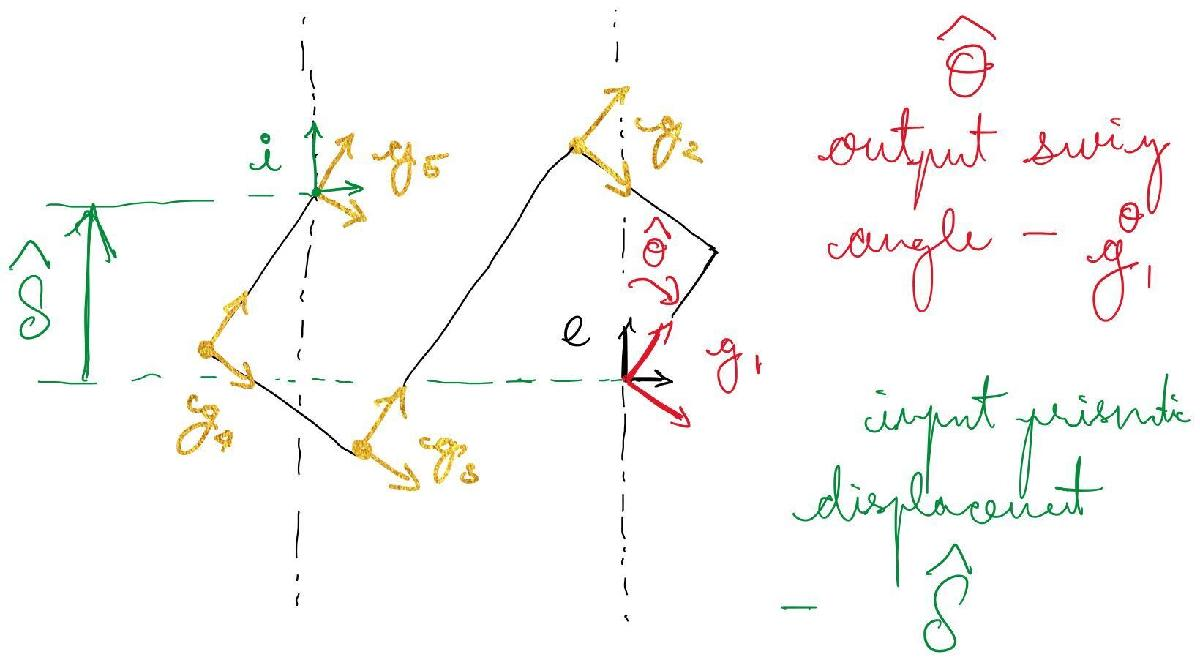

### SE(2)

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';
theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';

### 2D Swing Kinematics

syms l positive real
syms theta_hat real
h_e__1 = [0, 0, theta_hat]'; % define the transforms as column SE(2) vectors
h_1__2 = [-l, l, 0]';
h_2__3 = [0, -2*l, 0]';
h_3__4 = [-l, 0, 0]';
h_4__5 = [0, l, 0]';
h_5__i = [0, 0, -theta_hat]';

% Now that we have each transform, we can build up the full transform to
% the input frame.
h_e__i = M2v_SE2(v2M_SE2(h_e__1)*v2M_SE2(h_1__2)*v2M_SE2(h_2__3)*v2M_SE2(h_3__4)*...
    v2M_SE2(h_4__5)*v2M_SE2(h_5__i))

$$h\_e\_\_i = \left(\begin{array}{c} -2\,l\,\cos\left(\hat{\theta }\right)\\ -2\,l\,\sin\left(\hat{\theta }\right)\\ 0 \end{array}\right)$$

% Hence, the prismatic input from the motor:
delta_hat = dot(y_sel, h_e__i)

$$delta\_hat = -2\,l\,\sin\left(\hat{\theta }\right)$$

### SE(3)

% Only define the transformation from the vector to matrix form; there is
% no unique transformation from the group action form back to vector form.

% Initialize the symbolic variables
syms psi phi theta real

% The rotation matrices we need to construct the group operation
rotX = [1, 0, 0;
        0, cos(psi), -sin(psi);
        0, sin(psi), cos(psi)]

$$rotX = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & -\sin\left(\psi \right)\\ 0 & \sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$


rotY = [cos(phi), 0, -sin(phi);
        0, 1, 0;
        sin(phi), 0, cos(phi)]

$$rotY = \left(\begin{array}{ccc} \cos\left(\varphi \right) & 0 & -\sin\left(\varphi \right)\\ 0 & 1 & 0\\ \sin\left(\varphi \right) & 0 & \cos\left(\varphi \right) \end{array}\right)$$


rotZ = [cos(theta), -sin(theta), 0;
        sin(theta), cos(theta), 0;
        0, 0, 1]

$$rotZ = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_SE3 = rotX*rotY*rotZ

$$R\_SE3 = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right) & -\sin\left(\varphi \right)\\ \cos\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right)\\ \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) \end{array}\right)$$

syms x y z real
t_SE3 = [x, y, z]';
M_SE3 = [R_SE3, t_SE3;
        zeros(1,3), 1]

$$M\_SE3 = \left(\begin{array}{cccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right) & -\sin\left(\varphi \right) & x\\ \cos\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right) & y\\ \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

v2M_SE3 = @(v) subs(M_SE3, [x, y, z, psi, phi, theta], [v(1), v(2), v(3), v(4), v(5), v(6)]);

## 3D leg kinematics

Using the SE(3) frames defined earlier, we shall construct the kinematics of the 2DOF DASH leg module. Note that we shall be starting from the ground frame and rotate into the $\bar{g}$ frame.

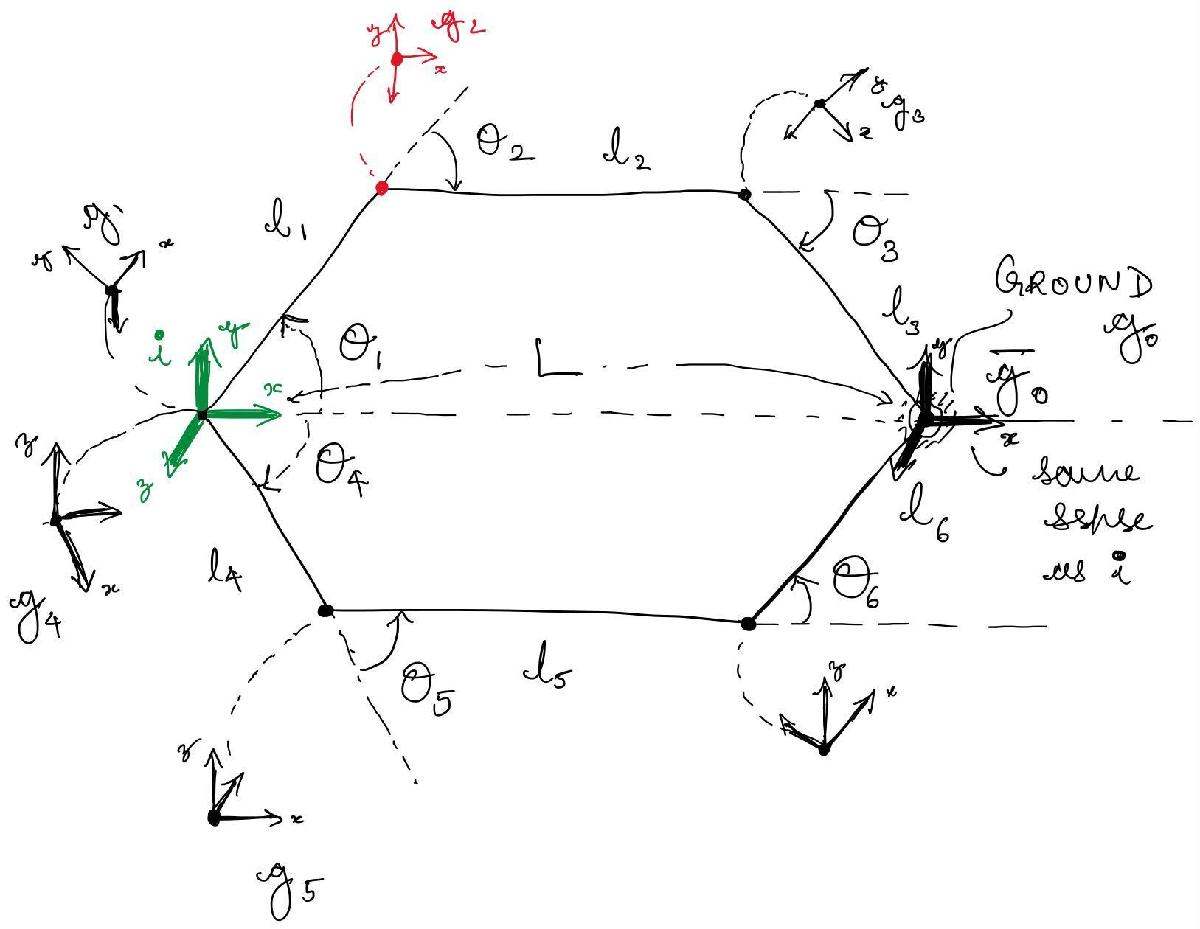

Accoridng to our assumption, we need to start off by capturing the transformation from the ground frame $g_0$ (this is also your group identity element $e$) to the oriented ground frame $\bar{g}_0$.

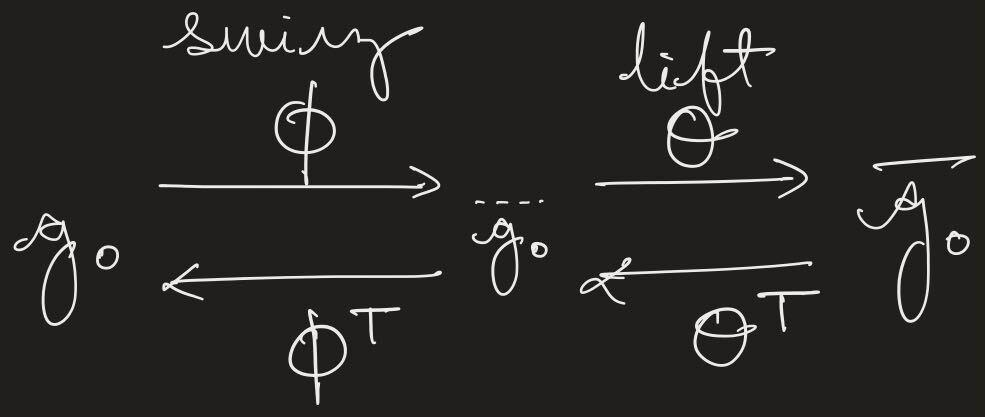

syms phi_0 theta_0 real
h_0__0b = [subs(rotY, phi, phi_0)*subs(rotZ, theta, theta_0), zeros(3,1);
            zeros(1,3), 1]

$$h\_0\_\_0b = \left(\begin{array}{cccc} \cos\left(\varphi_{0}\right)\,\cos\left(\theta_{0}\right) & -\cos\left(\varphi_{0}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\varphi_{0}\right) & 0\\ \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right) & 0 & 0\\ \cos\left(\theta_{0}\right)\,\sin\left(\varphi_{0}\right) & -\sin\left(\varphi_{0}\right)\,\sin\left(\theta_{0}\right) & \cos\left(\varphi_{0}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_0b__0 = h_0__0b' % will just be the transpose since it is only a rotation

$$h\_0b\_\_0 = \left(\begin{array}{cccc} \cos\left(\varphi_{0}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sin\left(\varphi_{0}\right) & 0\\ -\cos\left(\varphi_{0}\right)\,\sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right) & -\sin\left(\varphi_{0}\right)\,\sin\left(\theta_{0}\right) & 0\\ -\sin\left(\varphi_{0}\right) & 0 & \cos\left(\varphi_{0}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Next, we should enforce the constraint that the input and output rails are at a fixed distance $L$ between each other. This will then constrain how each lift and swing kinematic chain will behave. Let's start the transforms from the $i$th frame. Also, we're roughly following the DH convention in attaching frames.

syms l_1 l_2 l_3 l_4 l_5 l_6 l L real positive
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6 real
h_i__1 = [subs(rotZ, theta, theta_1), zeros(3,1);
            zeros(1,3), 1]

$$h\_i\_\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_1__2 = [subs(rotZ, theta, theta_2), [l_1, 0, 0]';
            zeros(1,3), 1]

$$h\_1\_\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{1}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_2__3 = [subs(rotZ, theta, theta_3), [l_2, 0, 0]';
            zeros(1,3), 1]

$$h\_2\_\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & l_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_3__0b_l = [subs(rotZ, theta, -theta_3-theta_2-theta_1), [l_3, 0, 0]';
            zeros(1,3), 1]

$$h\_3\_\_0b\_l = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & l_{3}\\ -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Therefore, the net transform should hence displace frame i to frame
% \bar{g}_0 by an amount `L'; the distance between the input rail and
% mechanical ground rail
h_i__0b_l = simplify(h_i__1*h_1__2*h_2__3*h_3__0b_l, 'Steps', 10)

$$h\_i\_\_0b\_l = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 & 1 & 0 & l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)+l_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hence, the net displacement of the chain to the mechanical ground takes the form that we expected.


$$$l_1 \ \left(\begin{array}{c}
\cos \left(\theta_1 \right) \\
\sin \left(\theta_1 \right) \\
0
\end{array}\right) + l_2 \ \left(\begin{array}{c}
\cos \left(\theta_1 +\theta_2 \right) \\
\sin \left(\theta_1 +\theta_2 \right) \\
0
\end{array}\right) + l_3 \ \left(\begin{array}{c}
\cos \left(\theta_1 +\theta_2 +\theta_3 \right) \\
\sin \left(\theta_1 +\theta_2 +\theta_3 \right) \\
0
\end{array}\right)$$$


Next, we can look at the structure of the swing kinematic chain.

h_i__4 = [subs(rotX, psi, pi/2)*subs(rotZ, theta, theta_4), zeros(3,1);
            zeros(1,3), 1]

$$h\_i\_\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_4__5 = [subs(rotZ, theta, theta_5), [l_4, 0, 0]';
            zeros(1,3), 1]

$$h\_4\_\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & l_{4}\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_5__6 = [subs(rotZ, theta, theta_6), [l_5, 0, 0]';
            zeros(1,3), 1]

$$h\_5\_\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & l_{5}\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_6__0b_s = [subs(rotZ, theta, -theta_4-theta_5-theta_6)*subs(rotX, psi, -pi/2), [l_6, 0, 0]';
            zeros(1,3), 1]

$$h\_6\_\_0b\_s = \left(\begin{array}{cccc} \cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) & 0 & \sin\left(\theta_{4}+\theta_{5}+\theta_{6}\right) & l_{6}\\ -\sin\left(\theta_{4}+\theta_{5}+\theta_{6}\right) & 0 & \cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_i__0b_s = simplify(h_i__4*h_4__5*h_5__6*h_6__0b_s, 'Steps', 10)

$$h\_i\_\_0b\_s = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\sin\left(\theta_{4}\right)+l_{6}\,\sin\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

From these two transformations from input frame $i$ to the oriented ground frame $\bar{g}_0$.

cond_1 = (h_i__0b_l(2,4) == 0)

$$cond\_1 = l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)+l_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)=0$$

cond_2 = (-h_i__0b_s(3,4) == 0)

$$cond\_2 = -l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)-l_{4}\,\sin\left(\theta_{4}\right)-l_{6}\,\sin\left(\theta_{4}+\theta_{5}+\theta_{6}\right)=0$$

cond_3 = (h_i__0b_l(1,4) == h_i__0b_s(1,4))

$$cond\_3 = l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)$$

We have constraints on the swing and lift link lengths and joint angles; 12 unknowns and 3 constraint equations. Actually, instead of taking the joint angles as just $\theta
$, we can treat them as elements in $\mathbb{S}^1$ and hence, they will be taken as $\left(\begin{array}{c}
\cos \left(\theta \right) \\
\sin \left(\theta \right)
\end{array}\right)$. This would then increase our number of states (link lengths and joint angles taken together as) 16 unknowns and 3 constraint equations. But, these are just much simpler to understand from the input frame $i$ point of view.

Let's also try to represent condition three as two separate conditions with coupled length $l$,

cond_3_l = lhs(cond_3) - l == 0

$$cond\_3\_l = l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)=0$$

cond_3_s = rhs(cond_3) - l == 0

$$cond\_3\_s = l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-l+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)=0$$

### Spherical Kinematic Constraints

Assume the effective length of swing and lift kinematic chains along x from $i$ are just $l$, making $i$ move along sphere with radius $l$ about the mechanical ground $g_0$ as the center.

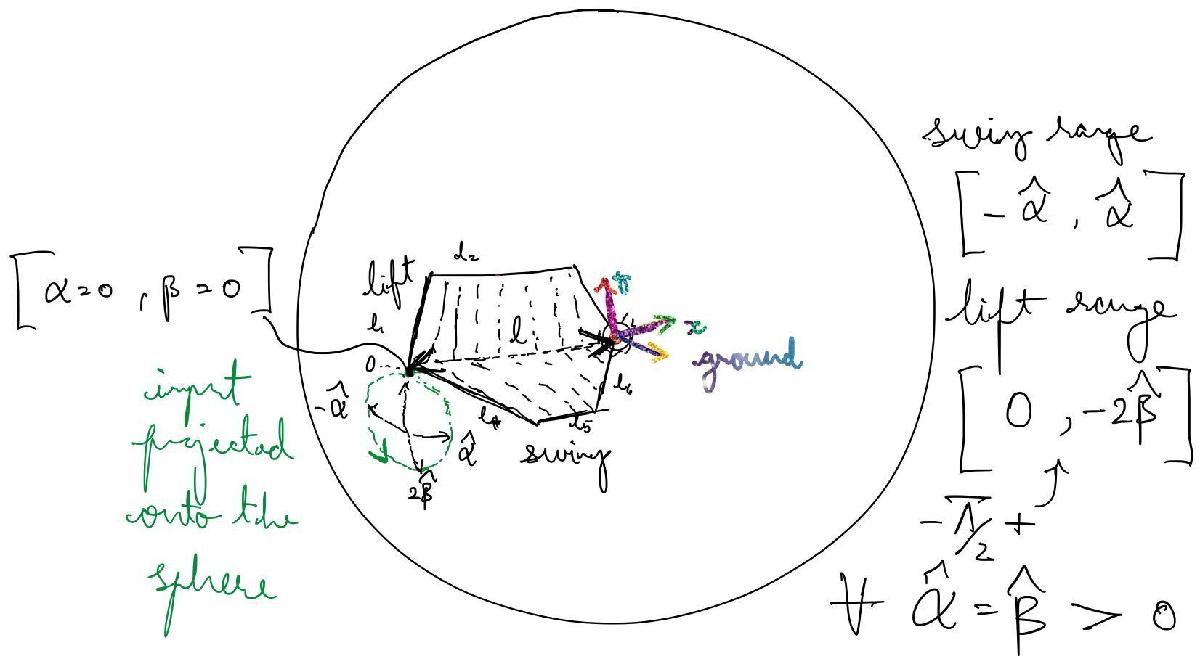

The input trajectory is projected onto this sphere; and using spherical coordinates, we can parameterize the trajectory. Consider the angle from the +y axis in the x-y plane to the input trajectory as lift $\beta$, and the angle made with the +x axis in the x-z plane as the swing $\alpha
$. Hence, the range for these trajectories are,


$$\alpha \in \left[-\hat{\alpha}, \hat{\alpha} \right], \\
\beta \in \Bigl\{-\frac{\pi}{2} \Bigl\} + \left[-2\hat{\beta}, 0 \right], \: \hat{\alpha} = \hat{\beta} > 0$$


For CCW motor motion, we can write the trajectories as a function of the gait phase $\tau$ as,


$$\alpha(\tau) = -\tilde{\alpha}(\tau) \\
\beta(\tau) = -\frac{\pi}{2} + \tilde{\beta}(\tau) \\
\text{where} \\
\tilde{\alpha}(\tau) = \hat{\alpha} \sin(2\pi\tau) \\
\tilde{\beta}(\tau) = \hat{\beta} \cos(2\pi\tau) - \hat{\beta} \\
\tau \in \left[0, 1 \right]$$


With y-axis as our zenith (x-axis is still our azimuth), the the surface of the kinematic sphere with radius $l$ takes a non-standard form and is given below. Also, the initial position of the input frame, $i_0$ should be at $\bigl(-l, 0, 0\bigr)^T$. Hence, we need to incorporate that input frame translation below in the formulation of $x$.


$$x = l \bigl(\sin(\beta) \cos(\alpha) + 1 \bigr) \\
y = l \cos(\beta) \\
z = l \sin(\beta) \sin(\alpha)$$


We can then simplify this with our knowledge of the input trajectory to get the locations of the input frame in cartesian coordinates with respect the the mechanical ground (center of the kinematic sphere).


$$(x, y, z) = l \: \Bigl(\sin\bigl(\tilde{\beta} - \frac{\pi}{2}\bigr) \cos\bigl(-\tilde{\alpha} \bigr) + 1, \: \cos\bigl(\tilde{\beta} - \frac{\pi}{2}\bigr), \: \sin\bigl(\tilde{\beta} - \frac{\pi}{2}\bigr) \sin\bigl(-\tilde{\alpha} \bigr) \Bigr) \\
= l \: \Bigl(-\cos\tilde{\beta} \cos\tilde{\alpha} + 1, \: \sin\tilde{\beta}, \: \cos\tilde{\beta} \sin\tilde{\alpha} \Bigr)$$


Next, we need to think about the orientation of $i$ frame in relation the ground frame $g_0$ or the initial $i_0$ frame. First, we need to rotate $i$ about +y-axis in plane by $\alpha$ and then by $-\tilde{\beta}$ about the +z axis. **This comes from the fact that the orientation of the joint-kinematic chain, **$i$** and the elevation angle from the mechanical ground's **$y$**-axis are defined in an opposite sense.**

syms tau real
syms alpha_hat beta_hat real positive
% Input trajectories
alpha_tilde = alpha_hat*sin(2*pi*tau)

$$alpha\_tilde = \hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)$$

beta_tilde = beta_hat*cos(2*pi*tau) - beta_hat

$$beta\_tilde = \hat{\beta }\,\cos\left(2\,\pi \,\tau \right)-\hat{\beta }$$

alpha = -alpha_tilde

$$alpha = -\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)$$

beta = -pi/2 + beta_tilde

$$beta = \hat{\beta }\,\cos\left(2\,\pi \,\tau \right)-\frac{\pi }{2}-\hat{\beta }$$

rotI = simplify(subs(rotY, phi, alpha)*subs(rotZ, theta, -beta_tilde), 'Steps', 10)

$$rotI = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1}\,\sigma_{3} & \sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\,\sigma_{3} & \sigma_{2}\\ \sin\left(2\,\hat{\beta }\,{\sin\left(\pi \,\tau \right)}^{2}\right) & \sigma_{1} & 0\\ -\sigma_{1}\,\sigma_{2} & \sin\left(2\,\hat{\beta }\,{\sin\left(\pi \,\tau \right)}^{2}\right)\,\sigma_{2} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{2}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right) \end{array}$$

transI = simplify(l*[sin(beta)*cos(alpha) + 1, cos(beta), sin(beta)*sin(alpha)]')

$$transI = \left(\begin{array}{c} l-l\,\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\,\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ l\,\sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ l\,\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\,\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right) \end{array}\right)$$

Finally, we can construct the transform from the group identity/origin to the input frame with it's translation and orientation figured out.

clear h_e__i
h_e__i = [rotI, transI; zeros(1,3), 1]

$$h\_e\_\_i = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{3} & \sigma_{4}\,\sigma_{3} & \sigma_{2} & l-l\,\sigma_{1}\,\sigma_{3}\\ \sigma_{5} & \sigma_{1} & 0 & l\,\sigma_{4}\\ -\sigma_{1}\,\sigma_{2} & \sigma_{5}\,\sigma_{2} & \sigma_{3} & l\,\sigma_{1}\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{2}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{4}=\sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{5}=\sin\left(2\,\hat{\beta }\,{\sin\left(\pi \,\tau \right)}^{2}\right) \end{array}$$

The final step in this process is to model the location of the leg in relation to the input frame $i$ and the two coupled kinematic chains for lift and swing; hence, we need both the location of the leg base, and the orientation which should be a function of orientation of the middle links in both kinematic chains; look at the actual mechanism belwo to see how the leg is coupled between both the chains to convince yourself.

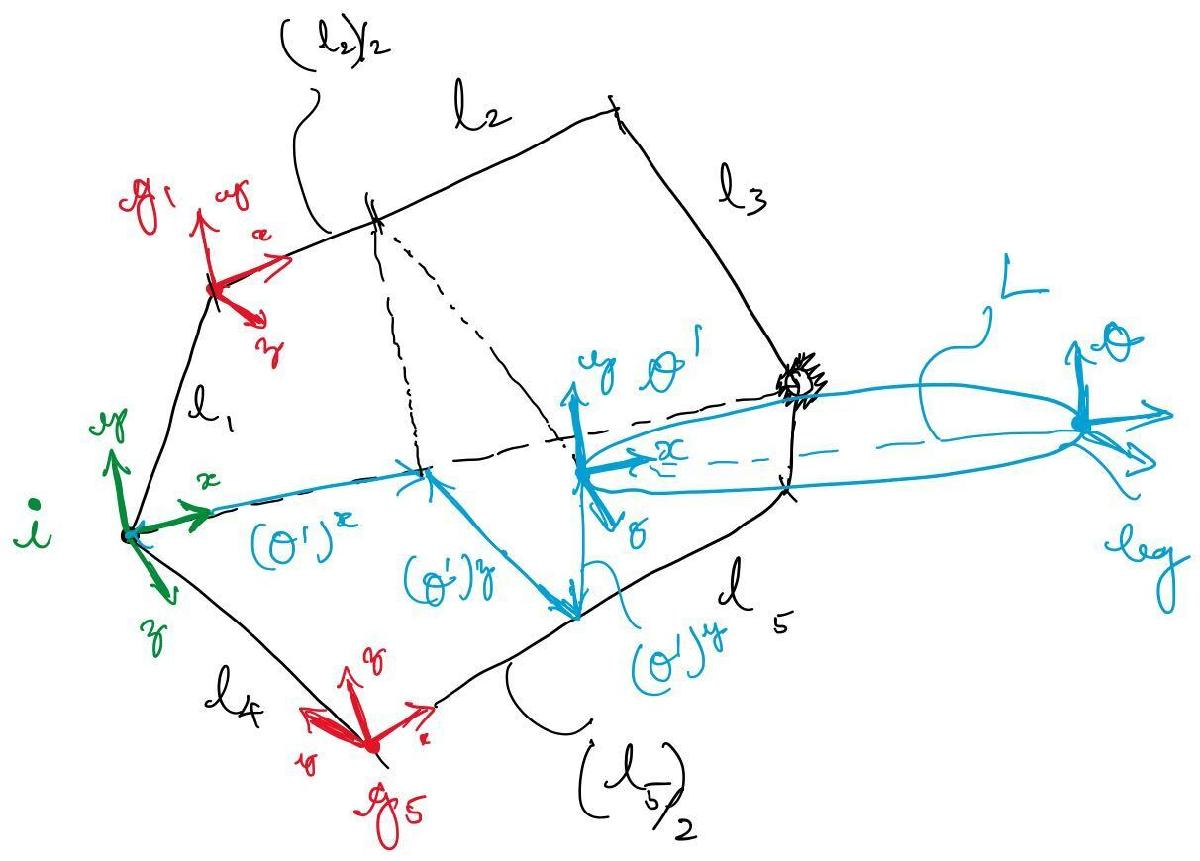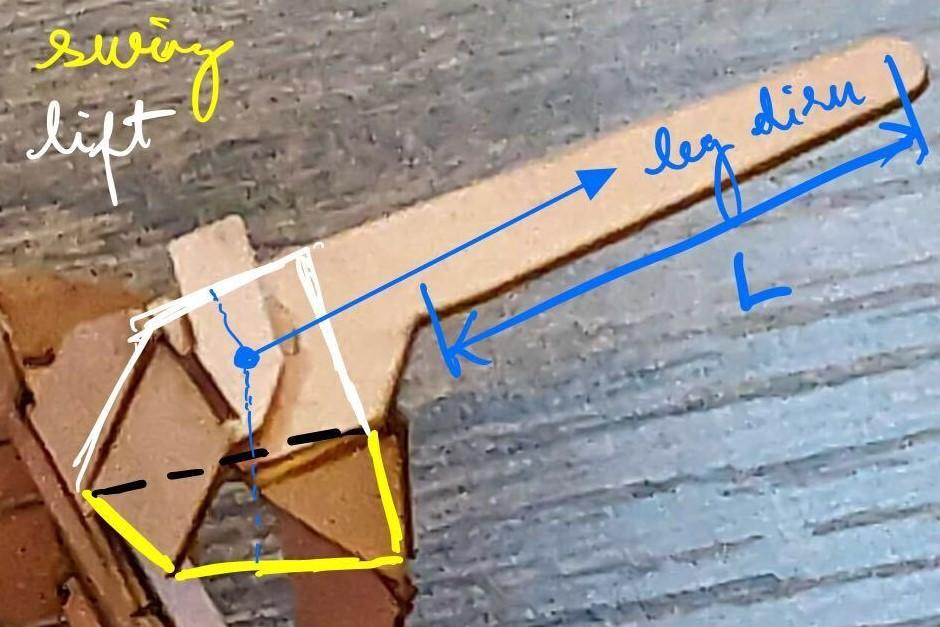

### Leg-base location and orientation

% % % % % Just some selection matrices for different purposes
% H is the 4x4 SE(3) matrix
xcirc = [1, 0, 0]'; ycirc = [0, 1, 0]'; zcirc = [0, 0, 1]';
ig_lastRow = [eye(3,3), zeros(3,1)]; get_lastCol = [0, 0, 0, 1]';
ig_lastCol = [eye(3,3); zeros(1,3)];
rotS = @(H) ig_lastRow*H*ig_lastCol; % isolate the rotational part
tranS = @(H) ig_lastRow*H*get_lastCol; % isolate the translational part
% make matrices to select individual translation components 
% without destroying the strcuture
selX_t = [eye(1,1), zeros(1,2); 
          zeros(2,3)];
selY_t = [zeros(1,3);
          0, 1, 0;
          zeros(1,3)];
selZ_t = [zeros(2,3);
          0, 0, 1];
% If you want to select two components just add the corresponding selection
% matrices, for instance selXY_t = selX_t + selY_t

The translational coordinates are simple to obtain; we need get to the location half-way between links 2 and 5.

% % LEGACY CODE -- Not supported anymore
% h_oprime__y = [0, 0, 0, 0;
%                0, 1, 0, 0;
%                0, 0, 0, 0;
%                0, 0, 0, 0]*simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]';
%                                zeros(1,3), 1])*[0, 0, 0, 1]'
% h_oprime__xz = [eye(3,3), zeros(3,1)]*simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5), 0.5*[l_5, 0, 0]';
%                                zeros(1,3), 1])*[0, 0, 0, 1]'
h_oprime__t = selY_t*...
    tranS(simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1]))...
    + ...
    (selX_t + selZ_t)*...
    tranS(simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1]))

$$h\_oprime\_\_t = \left(\begin{array}{c} \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}\right)$$

Next, we obtain the rotation coorinates so that the leg aligns along the middle links in lift and swing kinematic chains in the x-y and x-z planes respectively.

% Rotation to the lift chain middle link to the leg orientation in the x-y
% plane
theta_L = simplify(atan((ycirc'*rotS(h_i__1*h_1__2)*xcirc)...
    /(xcirc'*rotS(h_i__1*h_1__2)*xcirc)),'IgnoreAnalyticConstraints',true)

$$theta\_L = \theta_{1}+\theta_{2}$$

% Rotation to the swing chain middle link to the leg orientation in the x-z
% plane
phi_L = simplify(atan((ycirc'*subs(rotX,psi,-pi/2)*rotS(h_i__4*h_4__5)*xcirc)...
    /(xcirc'*subs(rotX,psi,-pi/2)*rotS(h_i__4*h_4__5)*xcirc)),'IgnoreAnalyticConstraints',true)

$$phi\_L = \theta_{4}+\theta_{5}$$

Let's now build the leg base frame and then the tip frame offset by L along x.

h_i__oprime = [simplify(subs(rotY,phi,phi_L)*subs(rotZ,theta,theta_L)), h_oprime__t; zeros(1,3), 1]

$$h\_i\_\_oprime = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right) & -\cos\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) & \cos\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_oprime__o = [eye(3,3), [L, 0, 0]'; zeros(1,3), 1]

$$h\_oprime\_\_o = \left(\begin{array}{cccc} 1 & 0 & 0 & L\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_i__o = simplify(h_i__oprime*h_oprime__o, 'Steps', 10)

$$h\_i\_\_o = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right) & -\cos\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) & \cos\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Before we finish off this section, we need two more transforms from the middle of each kinematic chain to the leg base.

h_i__23 = simplify(h_i__1*h_1__2*...
    [subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1], 'Steps', 10)

$$h\_i\_\_23 = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 & \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_i__56 = simplify(h_i__4*h_4__5*...
    [subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1], 'Steps', 10)

$$h\_i\_\_56 = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & -1 & \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Let's also obtain transforms to two additional mounting locations at the center of the lift and swing kinematic chains (L and S attached to variables names denote the chain to which the leg is attached).

h_oprimeL__t = tranS(simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1]))

$$h\_oprimeL\_\_t = \left(\begin{array}{c} \frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

h_i__oprimeL = [simplify(subs(rotZ,theta,theta_L)), h_oprimeL__t; zeros(1,3), 1]

$$h\_i\_\_oprimeL = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & \frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_oprimeL__oL = h_oprime__o;
h_i__oL = simplify(h_i__oprimeL*h_oprimeL__oL, 'Steps', 10)

$$h\_i\_\_oL = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & L\,\cos\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_oprimeS__t = tranS(simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1]))

$$h\_oprimeS\_\_t = \left(\begin{array}{c} \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0\\ \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}\right)$$

h_i__oprimeS = [simplify(subs(rotY,phi,phi_L)), h_oprimeS__t; zeros(1,3), 1]

$$h\_i\_\_oprimeS = \left(\begin{array}{cccc} \cos\left(\theta_{4}+\theta_{5}\right) & 0 & -\sin\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0 & 1 & 0 & 0\\ \sin\left(\theta_{4}+\theta_{5}\right) & 0 & \cos\left(\theta_{4}+\theta_{5}\right) & \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

h_oprimeS__oS = h_oprime__o;
h_i__oS = simplify(h_i__oprimeS*h_oprimeS__oS, 'Steps', 10)

$$h\_i\_\_oS = \left(\begin{array}{cccc} \cos\left(\theta_{4}+\theta_{5}\right) & 0 & -\sin\left(\theta_{4}+\theta_{5}\right) & L\,\cos\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0 & 1 & 0 & 0\\ \sin\left(\theta_{4}+\theta_{5}\right) & 0 & \cos\left(\theta_{4}+\theta_{5}\right) & L\,\sin\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Let's save all these analytical transforms to use later!

save('DASH_analytical', 'h_e__i', 'h_i__1', 'h_1__2', 'h_2__3', 'h_3__0b_l',...
    'h_i__4', 'h_4__5', 'h_5__6', 'h_6__0b_s', 'h_i__23', 'h_i__56', ...
    'h_i__oprime', 'h_i__o', 'h_i__oprimeL', 'h_i__oL', 'h_i__oprimeS', 'h_i__oS');

## DASH parameters (ballparked)

Here, we shall use some DASH parameters and massage them to satisfy our constraints on the chains being coincident.

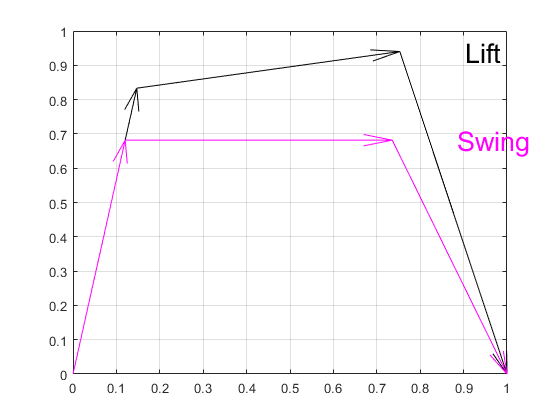

sRad = 1.3;
% Lift parameters ballparked %%%%%%%%%%%%%%%%%%%%%%%
l1 = 1.1; l2 = 0.8; % l3 = 1.3; theta3 = -deg2rad(94); manually measured and adjusted ballpark
theta1 = deg2rad(80); theta2 = -deg2rad(70);
theta3 = atan2(-l1*sin(theta1) -l2*sin(theta1+theta2), sRad -l1*cos(theta1) -l2*cos(theta1+theta2)) -theta2 -theta1;
l3 = norm([sRad-l1*cos(theta1)-l2*cos(theta1+theta2), -l1*sin(theta1)-l2*sin(theta1+theta2)]');
% Actual value turns out to be -95.25 degs for theta3
% Swing parameters ballparked %%%%%%%%%%%%%%%%%%%%%%%
l4 = 0.9; l5 = 0.8; % l6 = 0.7; theta6 = -deg2rad(85); manually measured and adjusted ballpark
theta4 = deg2rad(80); theta5 = -deg2rad(80);
theta6 = atan2(-l4*sin(theta4) -l5*sin(theta4+theta5), sRad -l4*cos(theta4) -l5*cos(theta4+theta5)) -theta5 -theta4;
l6 = norm([sRad-l4*cos(theta4)-l5*cos(theta4+theta5), -l4*sin(theta4)-l5*sin(theta4+theta5)]');
% Actual value turns out to be -80.85 degs for theta6
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Normalize all values such that sRad = 1;
lnorm = @(l) l/sRad; 
l1 = lnorm(l1); l2 = lnorm(l2); l3 = lnorm(l3); l4 = lnorm(l4); l5 = lnorm(l5); l6 = lnorm(l6);
sRad = 1;
% The length of the leg is roughly 3.5 cm; we're using the same value for
% the animation.

figure
quiver([0 l1*cos(theta1) l2*cos(theta2+theta1)+l1*cos(theta1)],...
    [0 l1*sin(theta1) l2*sin(theta2+theta1)+l1*sin(theta1)],...
    [l1*cos(theta1) l2*cos(theta2+theta1) l3*cos(theta3+theta2+theta1)],...
    [l1*sin(theta1) l2*sin(theta2+theta1) l3*sin(theta3+theta2+theta1)],0,'k')
text(l2*cos(theta2+theta1)+l1*cos(theta1)+0.15, l2*sin(theta2+theta1)+l1*sin(theta1),'Lift','FontSize',20,'Color','k')
hold on; grid on;
quiver([0 l4*cos(theta4) l5*cos(theta5+theta4)+l4*cos(theta4)],...
    [0 l4*sin(theta4) l5*sin(theta5+theta4)+l4*sin(theta4)],...
    [l4*cos(theta4) l5*cos(theta5+theta4) l6*cos(theta6+theta5+theta4)],...
    [l4*sin(theta4) l5*sin(theta5+theta4) l6*sin(theta6+theta5+theta4)],0,'m')
text(l5*cos(theta5+theta4)+l4*cos(theta4)+0.15, l5*sin(theta5+theta4)+l4*sin(theta4),'Swing','FontSize',20,'Color','m')

The parameters were massaged into the right format relatively well (the above plot of the kinematic chains on the same plane reveals this well). Next, step would be to plot the leg trajectory and express it in the right format.

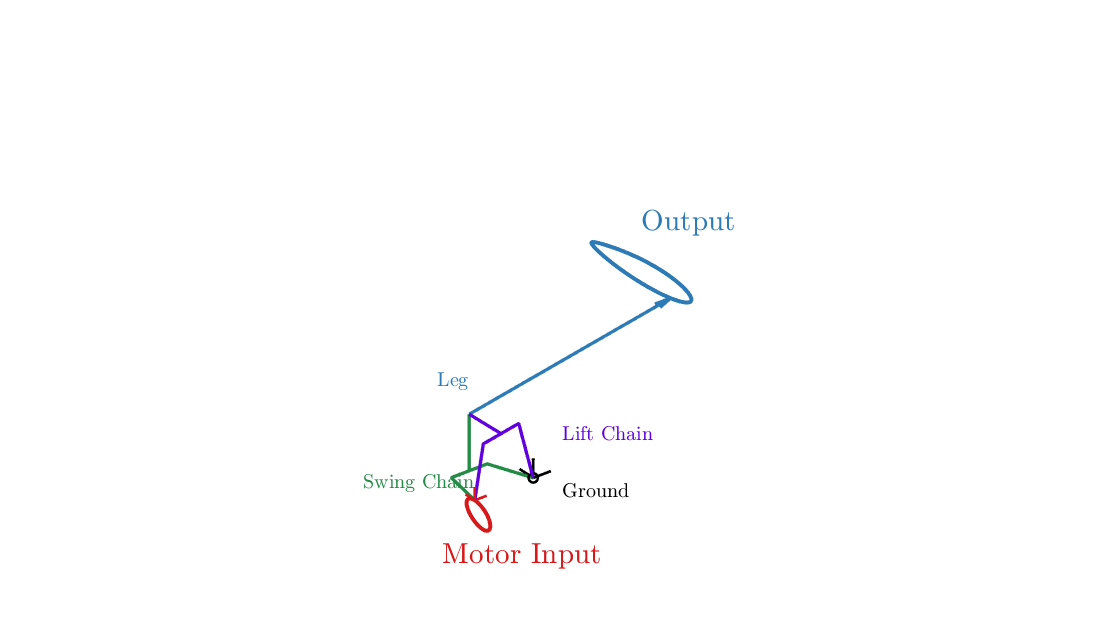

% Define the simulation parameters
t = linspace(0,1);

% equal swing and lift input amplitudes --  meant to denote the motor input to the system
b_hat = deg2rad(15);
a_hat = b_hat; % the motor can only give circular inputs to the system.

% % just lift
% b_hat = deg2rad(15);
% a_hat = deg2rad(0); 

% % just swing
% b_hat = deg2rad(0);
% a_hat = deg2rad(15); 

% Get each frame description to plot the kinematics
h_e_t = [eye(3,3), zeros(3,1);
        zeros(1,3), 1]; % origin position and frame information (numerical, not symbolic)

h_e__i_f = matlabFunction(h_e__i, 'Vars', [tau, alpha_hat, beta_hat, l]); % we just need to compute the input frame at each time step

h_i__1_t = double(subs(h_i__1, theta_1, theta1));
h_i__2_t = double(subs(h_i__1*h_1__2, [theta_1, l_1, theta_2], [theta1, l1, theta2]));
h_i__3_t = double(subs(h_i__1*h_1__2*h_2__3, [theta_1, l_1, theta_2, l_2, theta_3], [theta1, l1, theta2, l2, theta3]));
h_i__0bl_t = double(subs(h_i__1*h_1__2*h_2__3*h_3__0b_l, [theta_1, l_1, theta_2, l_2, theta_3, l_3], [theta1, l1, theta2, l2, theta3, l3]));

h_i__4_t = double(subs(h_i__4, theta_4, theta4));
h_i__5_t = double(subs(h_i__4*h_4__5, [theta_4, l_4, theta_5], [theta4, l4, theta5]));
h_i__6_t = double(subs(h_i__4*h_4__5*h_5__6, [theta_4, l_4, theta_5, l_5, theta_6], [theta4, l4, theta5, l5, theta6]));
h_i__0bs_t = double(subs(h_i__4*h_4__5*h_5__6*h_6__0b_s, [theta_4, l_4, theta_5, l_5, theta_6, l_6], [theta4, l4, theta5, l5, theta6, l6]));

h_i__23_t = double(subs(h_i__23, [theta_1, l_1, theta_2, l_2], [theta1, l1, theta2, l2]));
h_i__56_t = double(subs(h_i__56, [theta_4, l_4, theta_5, l_5], [theta4, l4, theta5, l5]));

% Make sure the 0b frame is averaged between the lift and swing kinematic
% chains when computing it at each time step.
h_i__oprime_t = double(subs(h_i__oprime, [theta_1, l_1, theta_2, l_2, theta_4, l_4, theta_5, l_5], [theta1, l1, theta2, l2, theta4, l4, theta5, l5]));
h_i__o_t = double(subs(h_i__o, [theta_1, l_1, theta_2, l_2, theta_4, l_4, theta_5, l_5, L], [theta1, l1, theta2, l2, theta4, l4, theta5, l5, 3.5]));

% Colors for each chain
circ1 = (1/255)*[215, 25, 28]; % input
circ3 = (1/255)*[44, 123, 182]; % output
circ2 = (1/255)*[96, 0, 220]; % lift
circ4 = (1/255)*[35,139,69]; % swing

% All frames are plotted using quiver. 
% 
% % Create empty containers to store the frame data as a function of time.
% The transforms below just shown the final frame since the starting from
% is the group origin/ identity e (dropped for convenience)
h_i_t = zeros(4,4,length(t));
h_1_t = h_i_t;
h_2_t = h_i_t;
h_3_t = h_i_t;
h_4_t = h_i_t;
h_5_t = h_i_t;
h_6_t = h_i_t;
h_0b_t = h_i_t;
h_23_t = h_i_t;
h_56_t = h_i_t;
h_oprime_t = h_i_t;
h_o_t = h_i_t;

% Plotting parameters (DEFINE BELOW)
qW_f = 2.00; % coordinate frames line width
qW_c = 2.50; % kinematic chain line width
qW_L = 2.50; % Leg line width
qW_t = 3.00; % input and output trajectory line width
arrwL = 0.20; % arrow length scaling
revS = 50; % try filled or unfilled for the 2D 
fontS = 17; % font size for the assisting text

% Start the loop and iterate over the configurations in body frame space:

% % Create the video object
% video = VideoWriter(strcat('DASH_leg_kinematics','.mp4'),'MPEG-4'); % creates mp4
% video = VideoWriter(strcat('DASH_leg_kinematics_liftAlone','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_swingAlone','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_liftAlone_1','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_liftAlone_2','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_swingAlone_2','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_2','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_3','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_4','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_5','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_6','.mp4'),'MPEG-4');
% % % % video = VideoWriter(strcat('DASH_leg_kinematics_7','.mp4'),'MPEG-4');
% % % % 
% % % % % Enter the length of the video:
% % % % vidT = 5;
% % % % % Set the framerate
% % % % video.FrameRate = round(length(t)/vidT); % roughly takes about 10seconds to complete the video
% % % % % Set the quality
% % % % video.Quality = 25;
% % % % % Open the video
% % % % open(video);

% Compute the input frame location before running the video loop
for i = 1:length(t)
    % Obtain the location of the input frame; use that to compute
    % everything else
    h_i_t(:,:,i) = h_e__i_f(t(i), a_hat, b_hat, sRad);
    h_1_t(:,:,i) = h_i_t(:,:,i)*h_i__1_t; % lift frames
    h_2_t(:,:,i) = h_i_t(:,:,i)*h_i__2_t;
    h_3_t(:,:,i) = h_i_t(:,:,i)*h_i__3_t;
    h_4_t(:,:,i) = h_i_t(:,:,i)*h_i__4_t; % swing frames
    h_5_t(:,:,i) = h_i_t(:,:,i)*h_i__5_t;
    h_6_t(:,:,i) = h_i_t(:,:,i)*h_i__6_t;
    h_0b_t(:,:,i) = h_i_t(:,:,i)*(h_i__0bs_t + h_i__0bl_t)*0.5; % averaged from the two
    h_23_t(:,:,i) = h_i_t(:,:,i)*h_i__23_t; % mid-lift chain
    h_56_t(:,:,i) = h_i_t(:,:,i)*h_i__56_t; % mid-swing chain
    h_oprime_t(:,:,i) = h_i_t(:,:,i)*h_i__oprime_t; % leg base
    h_o_t(:,:,i) = h_i_t(:,:,i)*h_i__o_t; % leg-tip
end

% Start plotting
figure('units','pixels','position',[0 0 1920 1080],'Color','w')

% % Set the background color as slightly gray for maximum contrast between
% % various elements in the figure
% set(gcf, 'color', (1/255)*[210,210,210]);

% Iterate over each frame
for i = 1:length(t)

    % Not needed right now -- doesn't add anything to the plot
% %     % Plot the origin
% %     quiver3(h_e_t(1,4)*ones(1,3), h_e_t(3,4)*ones(1,3), h_e_t(2,4)*ones(1,3),...
% %         arrwL*h_e_t(1,1:3), arrwL*h_e_t(3,1:3), arrwL*h_e_t(2,1:3), 0,...
% %         'LineWidth', qW_f, 'Color', 'k'); % x-axis at the origin

    % Axis settings
    hold on; axis equal; axis([-0.5, 4.75, -0.5, 1.5, -0.5, 4.75]);
    axis off;
%     grid on;

    % Plot the input %%%%%%%%% INPUT
    quiver3(h_i_t(1,4,i)*ones(1,3), h_i_t(3,4,i)*ones(1,3), h_i_t(2,4,i)*ones(1,3),...
        arrwL*h_i_t(1,1:3,i), arrwL*h_i_t(3,1:3,i), arrwL*h_i_t(2,1:3,i), 0,...
        'LineWidth', qW_f, 'Color', circ1); % coordinate axis at input

    % Plot the lift and swing kinematic chains
    plot3([h_i_t(1,4,i) h_1_t(1,4,i) h_2_t(1,4,i) h_3_t(1,4,i) h_0b_t(1,4,i)],...
        [h_i_t(3,4,i) h_1_t(3,4,i) h_2_t(3,4,i) h_3_t(3,4,i) h_0b_t(3,4,i)],...
        [h_i_t(2,4,i) h_1_t(2,4,i) h_2_t(2,4,i) h_3_t(2,4,i) h_0b_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ2); % lift chain % , 'Marker', '^'
    plot3([h_23_t(1,4,i) h_oprime_t(1,4,i)],...
        [h_23_t(3,4,i) h_oprime_t(3,4,i)],...
        [h_23_t(2,4,i) h_oprime_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ2); % lift chain to leg connection
    plot3([h_i_t(1,4,i) h_4_t(1,4,i) h_5_t(1,4,i) h_6_t(1,4,i) h_0b_t(1,4,i)],...
        [h_i_t(3,4,i) h_4_t(3,4,i) h_5_t(3,4,i) h_6_t(3,4,i) h_0b_t(3,4,i)],...
        [h_i_t(2,4,i) h_4_t(2,4,i) h_5_t(2,4,i) h_6_t(2,4,i) h_0b_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ4); % swing chain % , 'Marker', '>'
    plot3([h_56_t(1,4,i) h_oprime_t(1,4,i)],...
        [h_56_t(3,4,i) h_oprime_t(3,4,i)],...
        [h_56_t(2,4,i) h_oprime_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ4); % swing chain to leg connection

    % Plot the mechanical ground frame
    quiver3(h_0b_t(1,4,i)*ones(1,3), h_0b_t(3,4,i)*ones(1,3), h_0b_t(2,4,i)*ones(1,3),...
        1.5*arrwL*h_0b_t(1,1:3,i), 1.5*arrwL*h_0b_t(3,1:3,i),...
        1.5*arrwL*h_0b_t(2,1:3,i), 0,...
        'LineWidth', qW_f, 'Color', 'k'); % coordinate axis at gnd

    % Scatter a circle at mechanical ground (2 DOF revolute joint)
    scatter3(h_0b_t(1,4,i), h_0b_t(3,4,i), h_0b_t(2,4,i), revS,...
        'k', 'LineWidth', qW_f); %, 'filled'
    % unfilled circle is better to showcase a revolute joint

    % Plot the leg-base and leg tips using quiver %%%%%%%%% OUTPUT
    quiver3(h_oprime_t(1,4,i), h_oprime_t(3,4,i), h_oprime_t(2,4,i),...
        h_o_t(1,4,i)-h_oprime_t(1,4,i), h_o_t(3,4,i)-h_oprime_t(3,4,i),...
        h_o_t(2,4,i)-h_oprime_t(2,4,i), 0,...
        'LineWidth', qW_L, 'Color', circ3); % coordinate axis at gnd

    % Plot the trajectory here:
    plot3(reshape(h_i_t(1,4,:),1,length(t)),...
        reshape(h_i_t(3,4,:),1,length(t)),...
        reshape(h_i_t(2,4,:),1,length(t)),...
        'Color', circ1, 'LineWidth', qW_t); % input traj
    plot3(reshape(h_o_t(1,4,:),1,length(t)),...
        reshape(h_o_t(3,4,:),1,length(t)),...
        reshape(h_o_t(2,4,:),1,length(t)),...
        'Color', circ3, 'LineWidth', qW_t); % output traj
    
    % Labeling and titling
%     xlabel('x'); ylabel('y'); zlabel('z');
%     title('DASH 3D Kinematics');

    % Add text to denote different things
    text(-0.75,-0.25,-0.5,'Motor Input','Interpreter','latex',...
        'FontSize',fontS+5,'Color',circ1,...
        'FontWeight','bold')
    text(1.5,0.0,0.5,'Lift Chain','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ2)
    text(0.5,1.5,1,'Leg','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ3)
    text(4,1.5,2.25,'Output','Interpreter','latex',...
        'FontSize',fontS+5,'Color',circ3,...
        'FontWeight','bold')
    text(-0.65,1.65,-0.25,'Swing Chain','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ4)
    text(1.6,0.15,-0.5,'Ground','Interpreter','latex',...
        'FontSize',fontS-2,'Color','k')
    
    % Change the view:
    view(-37.5,30); % default values -- good point to start playing with viewpoints
%     view(-37.5,135); % beyond top view
%     view(-90,30); % top-ish view
%     view(0,90); % top view - SWING
%     view(0,0); % front view - LIFT

    % Draw the current plot since we are in a loop:
    drawnow;
% % % %     % Capture the frame:
% % % %     writeVideo(video,getframe(gcf));
    % Clear the frame if it is not the final one:
    if i ~= length(t)
        clf;
    end
end

% % % % % Close the video once everything is plotted
% % % % close(video);

We can also view the input, output trajectories separately to get a sense for how the leg moves to a circular motor input.

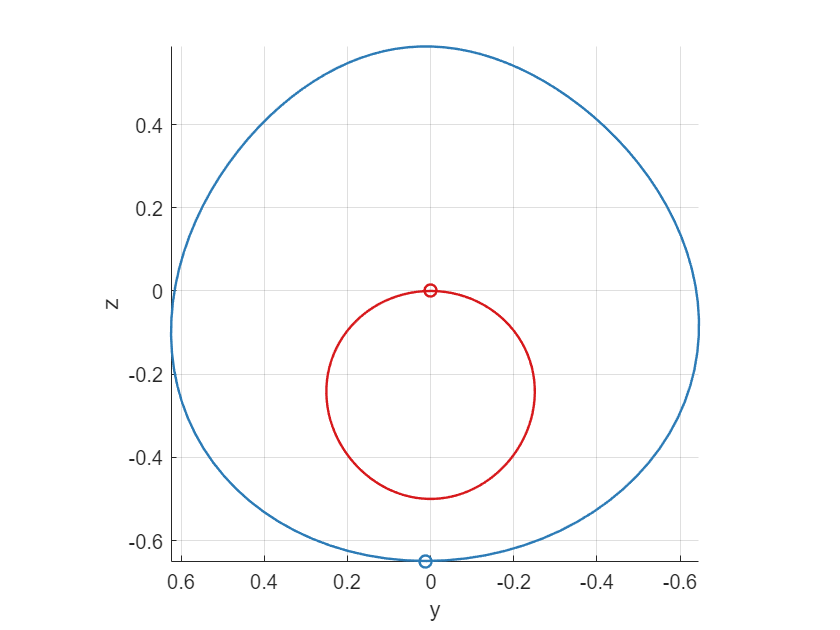

% Input and output trajectories
figure()
plot3(h_i_t(1,4,1),h_i_t(3,4,1),h_i_t(2,4,1),'o','LineWidth',1.2,'Color',circ1);
hold on; grid on; axis equal; view([-101.217 22.200]);
plot3(reshape(h_i_t(1,4,:),1,length(t)),reshape(h_i_t(3,4,:),1,length(t)),reshape(h_i_t(2,4,:),1,length(t)),...
    'Color',circ1,'LineWidth',1.2);
view(-90,0);
% Debugging the still images we are getting from the animation -- OUTPUT
o_mean_x = mean(h_o_t(1,4,:)); o_mean_y = mean(h_o_t(2,4,:)); o_mean_z = mean(h_o_t(3,4,:));
plot3(h_o_t(1,4,1)-o_mean_x,h_o_t(3,4,1)-o_mean_z,h_o_t(2,4,1)-o_mean_y,'o','LineWidth',1.2,'Color',circ3);
plot3(reshape(h_o_t(1,4,:),1,length(t))-o_mean_x,reshape(h_o_t(3,4,:),1,length(t))-o_mean_z,...
    reshape(h_o_t(2,4,:),1,length(t))-o_mean_y,...
    'Color',circ3,'LineWidth',1.2);
xlabel('x');
ylabel('y');
zlabel('z');

Takes an odd looking shape... On a separate note, we seem to have made a mistake with our motor lift input, it seems to be closer to being about the mean, instead being offset to one side like we have shown above. Take a look at this marked up lift chain side view to get a sense for how the input rail is setup.

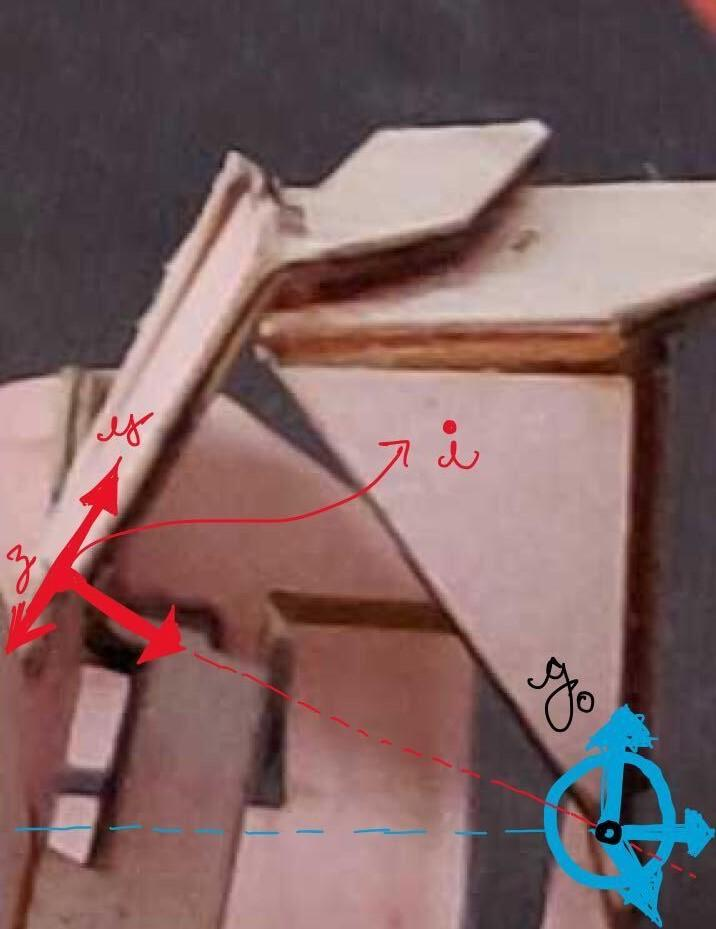

Let's redefine the lift input and observe the change!!


$$\tilde{\beta}(\tau) = \hat{\beta} \cos{(2 \pi \tau)}$$


beta_tilde = beta_hat*cos(2*pi*tau) % removed the offset

$$beta\_tilde = \hat{\beta }\,\cos\left(2\,\pi \,\tau \right)$$

beta = -pi/2 + beta_tilde

$$beta = \hat{\beta }\,\cos\left(2\,\pi \,\tau \right)-\frac{\pi }{2}$$

rotI = simplify(subs(rotY, phi, alpha)*subs(rotZ, theta, -beta_tilde), 'Steps', 10)

$$rotI = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{4}\,\sigma_{3} & \sigma_{3}\,\sigma_{2} & \sigma_{1}\\ -\sigma_{2} & \sigma_{4} & 0\\ -\sigma_{4}\,\sigma_{1} & -\sigma_{2}\,\sigma_{1} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{2}=\sin\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{4}=\cos\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right) \end{array}$$

transI = simplify(l*[sin(beta)*cos(alpha) + 1, cos(beta), sin(beta)*sin(alpha)]')

$$transI = \left(\begin{array}{c} l-l\,\cos\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\,\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ l\,\sin\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\\ l\,\cos\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\,\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right) \end{array}\right)$$

h_e__i = [rotI, transI; zeros(1,3), 1]

$$h\_e\_\_i = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{4} & \sigma_{4}\,\sigma_{3} & \sigma_{2} & l-l\,\sigma_{1}\,\sigma_{4}\\ -\sigma_{3} & \sigma_{1} & 0 & l\,\sigma_{3}\\ -\sigma_{1}\,\sigma_{2} & -\sigma_{3}\,\sigma_{2} & \sigma_{4} & l\,\sigma_{1}\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\\ \sigma_{2}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\sin\left(\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\\ \sigma_{4}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right) \end{array}$$

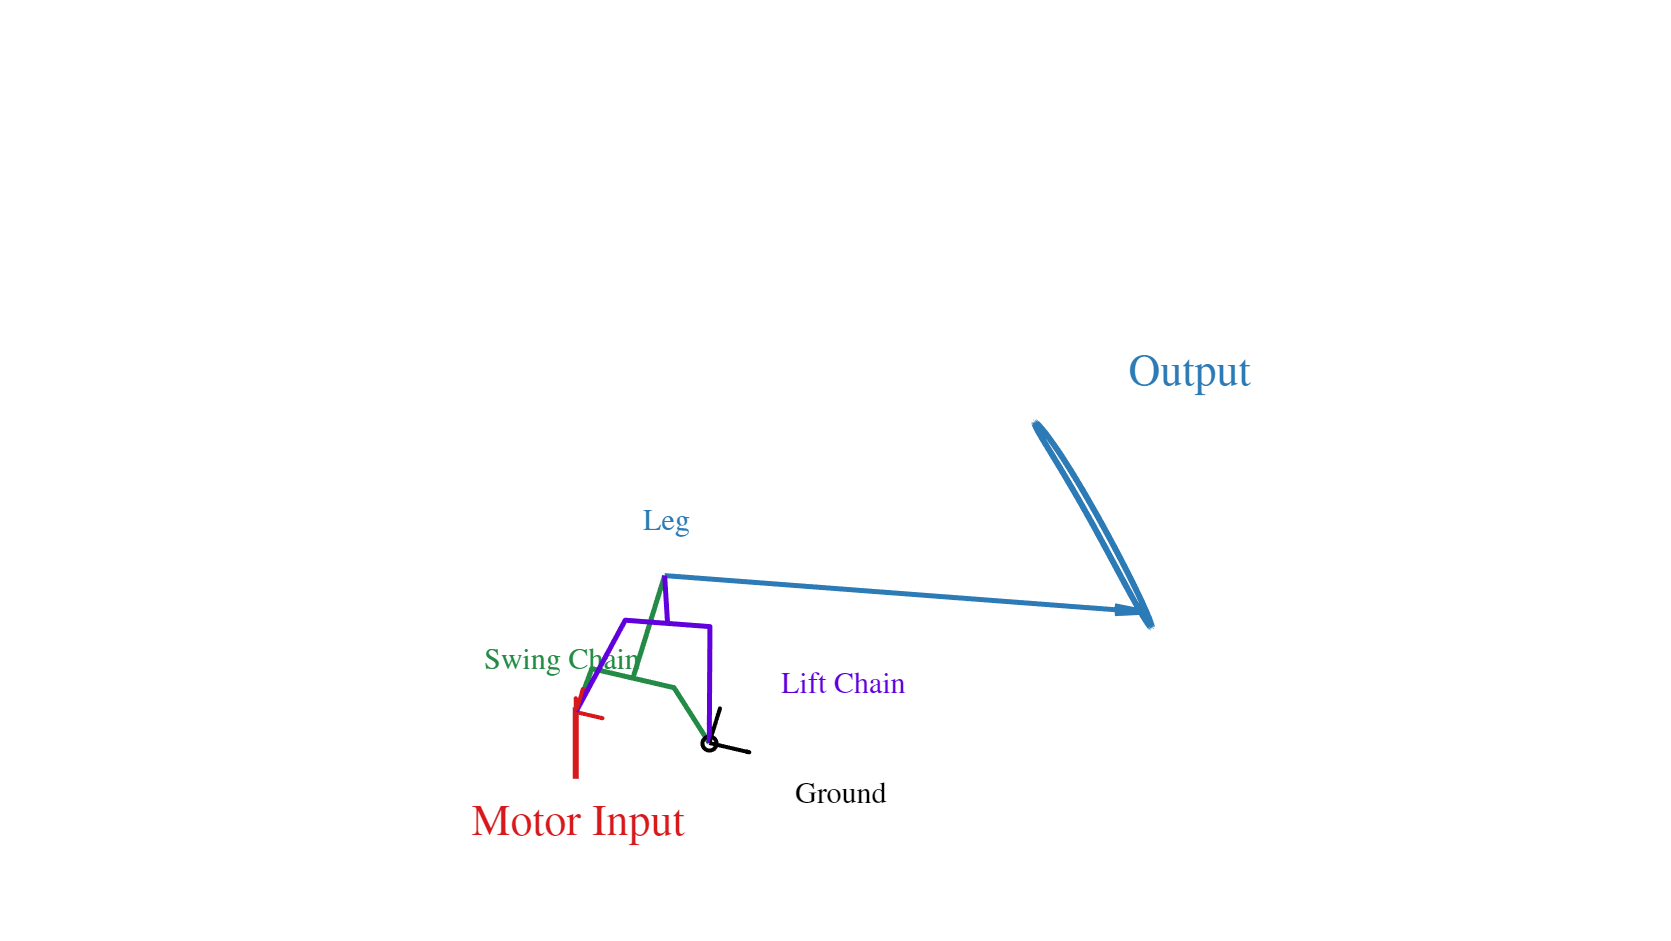

h_e__i_f = matlabFunction(h_e__i, 'Vars', [tau, alpha_hat, beta_hat, l]);

% % % % % video = VideoWriter(strcat('DASH_leg_kinematics_LiftFixed','.mp4'),'MPEG-4');
% video = VideoWriter(strcat('DASH_leg_kinematics_7','.mp4'),'MPEG-4');
% % % video = VideoWriter(strcat('DASH_leg_kinematics_8_wRot','.mp4'),'MPEG-4');
% % % 
% % % vidT = 5;
% % % video.FrameRate = round(length(t)/vidT);
% % % video.Quality = 25;
% % % open(video);

for i = 1:length(t)
    h_i_t(:,:,i) = h_e__i_f(t(i), a_hat, b_hat, sRad);
    h_1_t(:,:,i) = h_i_t(:,:,i)*h_i__1_t;
    h_2_t(:,:,i) = h_i_t(:,:,i)*h_i__2_t;
    h_3_t(:,:,i) = h_i_t(:,:,i)*h_i__3_t;
    h_4_t(:,:,i) = h_i_t(:,:,i)*h_i__4_t;
    h_5_t(:,:,i) = h_i_t(:,:,i)*h_i__5_t;
    h_6_t(:,:,i) = h_i_t(:,:,i)*h_i__6_t;
    h_0b_t(:,:,i) = h_i_t(:,:,i)*(h_i__0bs_t + h_i__0bl_t)*0.5;
    h_23_t(:,:,i) = h_i_t(:,:,i)*h_i__23_t;
    h_56_t(:,:,i) = h_i_t(:,:,i)*h_i__56_t;
    h_oprime_t(:,:,i) = h_i_t(:,:,i)*h_i__oprime_t;
    h_o_t(:,:,i) = h_i_t(:,:,i)*h_i__o_t;
end

figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% % Use this to set the background color:
% set(gcf, 'color', (1/255)*[210,210,210]);

for i = 1:length(t)

    hold on; axis equal; axis([-0.5, 4.75, -0.5, 1.5, -0.5, 4.75]);
    axis off;
%     grid on;

    % INPUT
    quiver3(h_i_t(1,4,i)*ones(1,3), h_i_t(3,4,i)*ones(1,3), h_i_t(2,4,i)*ones(1,3),...
        arrwL*h_i_t(1,1:3,i), arrwL*h_i_t(3,1:3,i), arrwL*h_i_t(2,1:3,i), 0,...
        'LineWidth', qW_f, 'Color', circ1);

    % KINEMATIC CHAINS
    plot3([h_i_t(1,4,i) h_1_t(1,4,i) h_2_t(1,4,i) h_3_t(1,4,i) h_0b_t(1,4,i)],...
        [h_i_t(3,4,i) h_1_t(3,4,i) h_2_t(3,4,i) h_3_t(3,4,i) h_0b_t(3,4,i)],...
        [h_i_t(2,4,i) h_1_t(2,4,i) h_2_t(2,4,i) h_3_t(2,4,i) h_0b_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ2);
    plot3([h_23_t(1,4,i) h_oprime_t(1,4,i)],...
        [h_23_t(3,4,i) h_oprime_t(3,4,i)],...
        [h_23_t(2,4,i) h_oprime_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ2);
    plot3([h_i_t(1,4,i) h_4_t(1,4,i) h_5_t(1,4,i) h_6_t(1,4,i) h_0b_t(1,4,i)],...
        [h_i_t(3,4,i) h_4_t(3,4,i) h_5_t(3,4,i) h_6_t(3,4,i) h_0b_t(3,4,i)],...
        [h_i_t(2,4,i) h_4_t(2,4,i) h_5_t(2,4,i) h_6_t(2,4,i) h_0b_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ4);
    plot3([h_56_t(1,4,i) h_oprime_t(1,4,i)],...
        [h_56_t(3,4,i) h_oprime_t(3,4,i)],...
        [h_56_t(2,4,i) h_oprime_t(2,4,i)],...
        'LineWidth', qW_c, 'Color', circ4);

    % GROUND
    quiver3(h_0b_t(1,4,i)*ones(1,3), h_0b_t(3,4,i)*ones(1,3), h_0b_t(2,4,i)*ones(1,3),...
        1.5*arrwL*h_0b_t(1,1:3,i), 1.5*arrwL*h_0b_t(3,1:3,i),...
        1.5*arrwL*h_0b_t(2,1:3,i), 0,...
        'LineWidth', qW_f, 'Color', 'k');
    scatter3(h_0b_t(1,4,i), h_0b_t(3,4,i), h_0b_t(2,4,i), revS,...
        'k', 'LineWidth', qW_f);

    % LEG OUTPUT
    quiver3(h_oprime_t(1,4,i), h_oprime_t(3,4,i), h_oprime_t(2,4,i),...
        h_o_t(1,4,i)-h_oprime_t(1,4,i), h_o_t(3,4,i)-h_oprime_t(3,4,i),...
        h_o_t(2,4,i)-h_oprime_t(2,4,i), 0,...
        'LineWidth', qW_L, 'Color', circ3);

    % TRAJECTORY:
    plot3(reshape(h_i_t(1,4,:),1,length(t)),...
        reshape(h_i_t(3,4,:),1,length(t)),...
        reshape(h_i_t(2,4,:),1,length(t)),...
        'Color', circ1, 'LineWidth', qW_t);
    plot3(reshape(h_o_t(1,4,:),1,length(t)),...
        reshape(h_o_t(3,4,:),1,length(t)),...
        reshape(h_o_t(2,4,:),1,length(t)),...
        'Color', circ3, 'LineWidth', qW_t);
    
    text(-0.75,-0.25,-0.5,'Motor Input','Interpreter','latex',...
        'FontSize',fontS+5,'Color',circ1,...
        'FontWeight','bold')
    text(1.5,0.0,0.5,'Lift Chain','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ2)
    text(0.5,1.5,1,'Leg','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ3)
    text(4,1.5,2.25,'Output','Interpreter','latex',...
        'FontSize',fontS+5,'Color',circ3,...
        'FontWeight','bold')
    text(-0.65,1.65,-0.25,'Swing Chain','Interpreter','latex',...
        'FontSize',fontS-2,'Color',circ4)
    text(1.6,0.15,-0.5,'Ground','Interpreter','latex',...
        'FontSize',fontS-2,'Color','k')
    
    % Change the view:
%     view(-37.5,30); % default values -- good point to start playing with viewpoints
%     view(-37.5,135); % beyond top view
%     view(-90,30); % top-ish view
%     view(0,90); % top view - SWING
%     view(0,0); % front view - LIFT
    view(-37.5*sin(2*pi*t(i)),30); % you can add a sinusoid to elevation too if needed!
    
% % %     drawnow;
% % %     writeVideo(video,getframe(gcf));
    if i ~= length(t)
        clf;
    end
end

% % % close(video);

We can also view the input, output trajectories separately to get a sense for how the leg moves to a circular motor input.

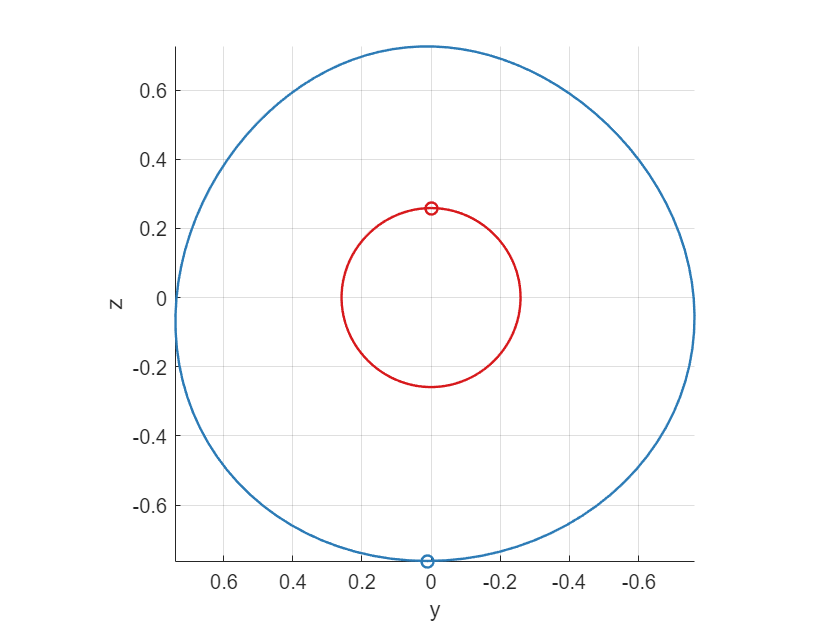

figure()
plot3(h_i_t(1,4,1),h_i_t(3,4,1),h_i_t(2,4,1),'o','LineWidth',1.2,'Color',circ1);
hold on; grid on; axis equal; view([-101.217 22.200]);
plot3(reshape(h_i_t(1,4,:),1,length(t)),reshape(h_i_t(3,4,:),1,length(t)),reshape(h_i_t(2,4,:),1,length(t)),...
    'Color',circ1,'LineWidth',1.2);
view(-90,0); 
% this is the optimal angle for viewing the input to output map
% since we are obliquely looking at the motor input circle in
% the +x direction with the y-z plane points distributed.
o_mean_x = mean(h_o_t(1,4,:)); o_mean_y = mean(h_o_t(2,4,:)); o_mean_z = mean(h_o_t(3,4,:));
plot3(h_o_t(1,4,1)-o_mean_x,h_o_t(3,4,1)-o_mean_z,h_o_t(2,4,1)-o_mean_y,'o','LineWidth',1.2,'Color',circ3);
plot3(reshape(h_o_t(1,4,:),1,length(t))-o_mean_x,reshape(h_o_t(3,4,:),1,length(t))-o_mean_z,...
    reshape(h_o_t(2,4,:),1,length(t))-o_mean_y,...
    'Color',circ3,'LineWidth',1.2);
xlabel('x');
ylabel('y');
zlabel('z');

## Swing to lift ratio

### Considering only in-plane components

Finally, we need to identify the kinematic model before, we move on design some chains. We start off by dialing $g_i$ back to an $\tilde{\alpha}$ and $\tilde{\beta}$ description. Just to remind ourselves of that, we have


$$\tilde{\alpha} = \hat{\alpha} \sin{(2 \pi \tau)} \\
\tilde{\beta} = \hat{\beta} \cos{(2 \pi \tau)}$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Run the SE3 section before running this section.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% equal swing and lift input amplitudes --  meant to denote the motor input to the system
% Additionally, note that the motor inputs are circular and don't change
% with a certain kinematic design; hence, we shall fix l*a_hat(or b_hat) as
% a constant for all designs with the original design having a coupled
% length of 1 unit and a isotropic tilt angle of 15degs.
% % % This is true if the coupled length is 1.
% % b_hat = deg2rad(15);
% % a_hat = b_hat;
b_hat = deg2rad(15)/l;
a_hat = b_hat;

syms alpha_tilde beta_tilde real
alpha = -alpha_tilde

$$alpha = -\tilde{\alpha }$$

beta = -pi/2 + beta_tilde

$$beta = \tilde{\beta }-\frac{\pi }{2}$$

rotI = simplify(subs(rotY, phi, alpha)*subs(rotZ, theta, -beta_tilde), 'Steps', 10)

$$rotI = \left(\begin{array}{ccc} \cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right) & \cos\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right) & \sin\left(\tilde{\alpha }\right)\\ -\sin\left(\tilde{\beta }\right) & \cos\left(\tilde{\beta }\right) & 0\\ -\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right) & -\sin\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right) & \cos\left(\tilde{\alpha }\right) \end{array}\right)$$

transI = simplify(l*[sin(beta)*cos(alpha) + 1, cos(beta), sin(beta)*sin(alpha)]')

$$transI = \left(\begin{array}{c} -l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)\\ l\,\sin\left(\tilde{\beta }\right)\\ l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right) \end{array}\right)$$

clear h_e__i
h_e__i = simplify([rotI, transI; zeros(1,3), 1], 'Steps', 10)

$$h\_e\_\_i = \left(\begin{array}{cccc} \cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right) & \cos\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right) & \sin\left(\tilde{\alpha }\right) & -l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)\\ -\sin\left(\tilde{\beta }\right) & \cos\left(\tilde{\beta }\right) & 0 & l\,\sin\left(\tilde{\beta }\right)\\ -\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right) & -\sin\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right) & \cos\left(\tilde{\alpha }\right) & l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

ht_e__i = tranS(h_e__i)

$$ht\_e\_\_i = \left(\begin{array}{c} -l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)\\ l\,\sin\left(\tilde{\beta }\right)\\ l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right) \end{array}\right)$$

Now, we can obtain the relationship between the input and the output.

h_e__o = h_e__i*h_i__o; % full transform for the coupled mounting
h_e__oL = h_e__i*h_i__oL; % full transform for the lift mounting
h_e__oS = h_e__i*h_i__oS; % full transform for the swing mounting
ht_e__o = tranS(h_e__o) % isolate just the translation for the coupled mounting condition

$$ht\_e\_\_o = \begin{array}{l} \left(\begin{array}{c} \sin\left(\tilde{\alpha }\right)\,\sigma_{3}-l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)+\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)\,\sigma_{1}+\cos\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right)\,\sigma_{2}\\ \cos\left(\tilde{\beta }\right)\,\sigma_{2}+l\,\sin\left(\tilde{\beta }\right)-\sin\left(\tilde{\beta }\right)\,\sigma_{1}\\ \cos\left(\tilde{\alpha }\right)\,\sigma_{3}-\sin\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right)\,\sigma_{2}+l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)-\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) \end{array}$$

ht_e__oL = tranS(h_e__oL)

$$ht\_e\_\_oL = \begin{array}{l} \left(\begin{array}{c} \cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)\,\sigma_{2}-l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)+\cos\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right)\,\sigma_{1}\\ \cos\left(\tilde{\beta }\right)\,\sigma_{1}-\sin\left(\tilde{\beta }\right)\,\sigma_{2}+l\,\sin\left(\tilde{\beta }\right)\\ l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)-\sin\left(\tilde{\alpha }\right)\,\sin\left(\tilde{\beta }\right)\,\sigma_{1}-\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=L\,\cos\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

ht_e__oS = tranS(h_e__oS)

$$ht\_e\_\_oS = \begin{array}{l} \left(\begin{array}{c} \sin\left(\tilde{\alpha }\right)\,\sigma_{2}-l\,\left(\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)-1\right)+\cos\left(\tilde{\alpha }\right)\,\cos\left(\tilde{\beta }\right)\,\sigma_{1}\\ l\,\sin\left(\tilde{\beta }\right)-\sin\left(\tilde{\beta }\right)\,\sigma_{1}\\ \cos\left(\tilde{\alpha }\right)\,\sigma_{2}+l\,\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)-\cos\left(\tilde{\beta }\right)\,\sin\left(\tilde{\alpha }\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\cos\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ \sigma_{2}=L\,\sin\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}$$

Isolate swing and obtain the output range as a function of the kinematic chain and leg length variables.

ht_e__o_swing = subs(ht_e__o, beta_tilde, 0) % swing alone

$$ht\_e\_\_o\_swing = \begin{array}{l} \left(\begin{array}{c} \cos\left(\tilde{\alpha }\right)\,\sigma_{2}+\sin\left(\tilde{\alpha }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\alpha }\right)-1\right)\\ L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ l\,\sin\left(\tilde{\alpha }\right)-\sin\left(\tilde{\alpha }\right)\,\sigma_{2}+\cos\left(\tilde{\alpha }\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right) \end{array}$$

ht_e__oL_swing = subs(ht_e__oL, beta_tilde, 0)

$$ht\_e\_\_oL\_swing = \begin{array}{l} \left(\begin{array}{c} \cos\left(\tilde{\alpha }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\alpha }\right)-1\right)\\ L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ l\,\sin\left(\tilde{\alpha }\right)-\sin\left(\tilde{\alpha }\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\cos\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

ht_e__oS_swing = subs(ht_e__oS, beta_tilde, 0)

$$ht\_e\_\_oS\_swing = \begin{array}{l} \left(\begin{array}{c} \sin\left(\tilde{\alpha }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\alpha }\right)-1\right)+\cos\left(\tilde{\alpha }\right)\,\sigma_{2}\\ 0\\ \cos\left(\tilde{\alpha }\right)\,\sigma_{1}-\sin\left(\tilde{\alpha }\right)\,\sigma_{2}+l\,\sin\left(\tilde{\alpha }\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ \sigma_{2}=L\,\cos\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right) \end{array}$$

In order to obtain the range now, we need to implement a path integral over our swing limits of the rate of change if the output position in $\tilde{\alpha}$.

**20221026: Reinstating **$l$ substitution** in this step due to optimizer convergence issues. **But, it was good to see that double kinematic coupling will never provide independent amplification.

syms alpha_tilde__0 alpha_tilde__1 real
ht_e__o_swing_range = simplify(subs(int(diff(ht_e__o_swing,alpha_tilde), alpha_tilde, [alpha_tilde__0, alpha_tilde__1]), l, rhs(cond_3)), 'Steps', 10)

$$ht\_e\_\_o\_swing\_range = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\,\sigma_{3}-l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}-\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\\ 0\\ l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}-\sigma_{2}\,\sigma_{3}-\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}-l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{3}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__oL_swing_range = simplify(subs(int(diff(ht_e__oL_swing,alpha_tilde), alpha_tilde, [alpha_tilde__0, alpha_tilde__1]), l, rhs(cond_3)), 'Steps', 10)

$$ht\_e\_\_oL\_swing\_range = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right)\right)\,\sigma_{1}}{2}\\ 0\\ \frac{\left(\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right)\right)\,\sigma_{1}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__oS_swing_range = simplify(subs(int(diff(ht_e__oS_swing,alpha_tilde), alpha_tilde, [alpha_tilde__0, alpha_tilde__1]), l, rhs(cond_3)), 'Steps', 10)

$$ht\_e\_\_oS\_swing\_range = \begin{array}{l} \left(\begin{array}{c} L\,\sigma_{4}-L\,\sigma_{5}-\frac{l_{5}\,\sigma_{5}}{2}+\frac{l_{5}\,\sigma_{4}}{2}+\cos\left({\tilde{\alpha }}^{0}\right)\,\sigma_{1}-\cos\left({\tilde{\alpha }}^{1}\right)\,\sigma_{1}-l_{4}\,\cos\left({\tilde{\alpha }}^{0}-\theta_{4}\right)+l_{4}\,\cos\left({\tilde{\alpha }}^{1}-\theta_{4}\right)\\ 0\\ L\,\sigma_{2}-L\,\sigma_{3}-\frac{l_{5}\,\sigma_{3}}{2}+\frac{l_{5}\,\sigma_{2}}{2}-\sin\left({\tilde{\alpha }}^{0}\right)\,\sigma_{1}+\sin\left({\tilde{\alpha }}^{1}\right)\,\sigma_{1}+l_{4}\,\sin\left({\tilde{\alpha }}^{0}-\theta_{4}\right)-l_{4}\,\sin\left({\tilde{\alpha }}^{1}-\theta_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{2}=\sin\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)\\ \sigma_{3}=\sin\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right)\\ \sigma_{4}=\cos\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)\\ \sigma_{5}=\cos\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right) \end{array}$$

Recall that most disaplacement strength of swing lies along the z-axis when viewed in the y-z plane; hence, we shall isolate that z-component. Note that, this value needs to be positive; hence, we shall square the obtained result and then use it in our objective formulation.

ht_e__o_swing_rangeZ_sq = ht_e__o_swing_range(3)^2 % subs(ht_e__o_swing_range(3), l, rhs(cond_3))^2

$$ht\_e\_\_o\_swing\_rangeZ\_sq = \begin{array}{l} {\left(\sigma_{1}\,\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{2}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{2}=\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right) \end{array}$$

ht_e__oL_swing_rangeZ_sq = ht_e__oL_swing_range(3)^2 % subs(ht_e__oL_swing_range(3), l, rhs(cond_3))^2

$$ht\_e\_\_oL\_swing\_rangeZ\_sq = \frac{{\left(\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right)\right)}^{2}\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}{4}$$

ht_e__oS_swing_rangeZ_sq = ht_e__oS_swing_range(3)^2 % subs(ht_e__oS_swing_range(3), l, rhs(cond_3))^2

$$ht\_e\_\_oS\_swing\_rangeZ\_sq = \begin{array}{l} {\left(L\,\sin\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right)-L\,\sin\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)+\frac{l_{5}\,\sin\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right)}{2}-\frac{l_{5}\,\sin\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)}{2}+\sin\left({\tilde{\alpha }}^{0}\right)\,\sigma_{1}-\sin\left({\tilde{\alpha }}^{1}\right)\,\sigma_{1}-l_{4}\,\sin\left({\tilde{\alpha }}^{0}-\theta_{4}\right)+l_{4}\,\sin\left({\tilde{\alpha }}^{1}-\theta_{4}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__o_swing_rangeZ_constMinp_sq = simplify(subs(ht_e__o_swing_rangeZ_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_o\_swing\_rangeZ\_constMinp\_sq = {\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}$$

ht_e__oL_swing_rangeZ_constMinp_sq = simplify(subs(ht_e__oL_swing_rangeZ_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oL\_swing\_rangeZ\_constMinp\_sq = {\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}$$

ht_e__oS_swing_rangeZ_constMinp_sq = simplify(subs(ht_e__oS_swing_rangeZ_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oS\_swing\_rangeZ\_constMinp\_sq = \begin{array}{l} {\left(\frac{l_{5}\,\sigma_{1}}{2}-\frac{l_{5}\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}-\frac{\pi }{12\,l}\right)-l_{4}\,\sin\left(\theta_{4}+\frac{\pi }{12\,l}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\right) \end{array}$$

The amplification factor for the swing degree of freedom would be the swing output over the input amplitude, and this works out to,

ht_e__i_swing_rangeZ_constMinp_sq = (2*subs(subs(ht_e__i(3), l, rhs(cond_3)), [beta_tilde alpha_tilde], [0 a_hat]))^2

$$ht\_e\_\_i\_swing\_rangeZ\_constMinp\_sq = 4\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}$$

We didn't substitute for 'l' in the input because this is a variable that will get cancelled when we figure out the overall amplification factor.

ht_e__o_swing_ampZ_constMinp_sq = simplify(ht_e__o_swing_rangeZ_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_o\_swing\_ampZ\_constMinp\_sq = \frac{{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}}{4\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}$$

ht_e__oL_swing_ampZ_constMinp_sq = simplify(ht_e__oL_swing_rangeZ_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oL\_swing\_ampZ\_constMinp\_sq = \frac{{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}{4\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}$$

ht_e__oS_swing_ampZ_constMinp_sq = simplify(ht_e__oS_swing_rangeZ_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oS\_swing\_ampZ\_constMinp\_sq = \begin{array}{l} \frac{{\left(\frac{l_{5}\,\sigma_{2}}{2}-\frac{l_{5}\,\sigma_{3}}{2}+l_{4}\,\sin\left(\theta_{4}-\frac{\pi }{12\,l}\right)-l_{4}\,\sin\left(\theta_{4}+\frac{\pi }{12\,l}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\sigma_{1}+L\,\sigma_{2}-L\,\sigma_{3}\right)}^{2}}{4\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{2}=\sin\left(\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\right) \end{array}$$

Similarly, after this, we shall repeat the procedure for the lift chain and isolate it's squared range in the y-direction.

ht_e__o_lift = subs(ht_e__o, alpha_tilde, 0) % lift alone

$$ht\_e\_\_o\_lift = \begin{array}{l} \left(\begin{array}{c} \sin\left(\tilde{\beta }\right)\,\sigma_{2}+\cos\left(\tilde{\beta }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\beta }\right)-1\right)\\ \cos\left(\tilde{\beta }\right)\,\sigma_{2}+l\,\sin\left(\tilde{\beta }\right)-\sin\left(\tilde{\beta }\right)\,\sigma_{1}\\ \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right) \end{array}$$

ht_e__oL_lift = subs(ht_e__oL, alpha_tilde, 0)

$$ht\_e\_\_oL\_lift = \begin{array}{l} \left(\begin{array}{c} \sin\left(\tilde{\beta }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\beta }\right)-1\right)+\cos\left(\tilde{\beta }\right)\,\sigma_{2}\\ \cos\left(\tilde{\beta }\right)\,\sigma_{1}-\sin\left(\tilde{\beta }\right)\,\sigma_{2}+l\,\sin\left(\tilde{\beta }\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=L\,\cos\left(\theta_{1}+\theta_{2}\right)+\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

ht_e__oS_lift = subs(ht_e__oS, alpha_tilde, 0)

$$ht\_e\_\_oS\_lift = \begin{array}{l} \left(\begin{array}{c} \cos\left(\tilde{\beta }\right)\,\sigma_{1}-l\,\left(\cos\left(\tilde{\beta }\right)-1\right)\\ l\,\sin\left(\tilde{\beta }\right)-\sin\left(\tilde{\beta }\right)\,\sigma_{1}\\ L\,\sin\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\cos\left(\theta_{4}+\theta_{5}\right)+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right) \end{array}$$

syms beta_tilde__0 beta_tilde__1 real
ht_e__o_lift_range = simplify(subs(int(diff(ht_e__o_lift,beta_tilde), beta_tilde, [beta_tilde__0, beta_tilde__1]), l, lhs(cond_3)), 'Steps', 10) % definite integral to get the range

$$ht\_e\_\_o\_lift\_range = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\,\sigma_{3}-l_{1}\,\sin\left(\theta_{1}\right)\,\sigma_{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}-L\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}-\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}}{2}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}\\ l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}-\sigma_{2}\,\sigma_{3}-L\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}-\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}}{2}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}-l_{1}\,\sin\left(\theta_{1}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\beta }}^{0}\right)-\cos\left({\tilde{\beta }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\beta }}^{0}\right)-\sin\left({\tilde{\beta }}^{1}\right)\\ \sigma_{3}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__oL_lift_range = simplify(subs(int(diff(ht_e__oL_lift,beta_tilde), beta_tilde, [beta_tilde__0, beta_tilde__1]), l, lhs(cond_3)), 'Steps', 10)

$$ht\_e\_\_oL\_lift\_range = \begin{array}{l} \left(\begin{array}{c} L\,\sigma_{4}-L\,\sigma_{5}-\frac{l_{2}\,\sigma_{5}}{2}+\frac{l_{2}\,\sigma_{4}}{2}+\cos\left({\tilde{\beta }}^{0}\right)\,\sigma_{1}-\cos\left({\tilde{\beta }}^{1}\right)\,\sigma_{1}-l_{1}\,\cos\left({\tilde{\beta }}^{0}-\theta_{1}\right)+l_{1}\,\cos\left({\tilde{\beta }}^{1}-\theta_{1}\right)\\ L\,\sigma_{2}-L\,\sigma_{3}-\frac{l_{2}\,\sigma_{3}}{2}+\frac{l_{2}\,\sigma_{2}}{2}-\sin\left({\tilde{\beta }}^{0}\right)\,\sigma_{1}+\sin\left({\tilde{\beta }}^{1}\right)\,\sigma_{1}+l_{1}\,\sin\left({\tilde{\beta }}^{0}-\theta_{1}\right)-l_{1}\,\sin\left({\tilde{\beta }}^{1}-\theta_{1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sin\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)\\ \sigma_{3}=\sin\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right)\\ \sigma_{4}=\cos\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)\\ \sigma_{5}=\cos\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right) \end{array}$$

ht_e__oS_lift_range = simplify(subs(int(diff(ht_e__oS_lift,beta_tilde), beta_tilde, [beta_tilde__0, beta_tilde__1]), l, lhs(cond_3)), 'Steps', 10)

$$ht\_e\_\_oS\_lift\_range = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(\cos\left({\tilde{\beta }}^{0}\right)-\cos\left({\tilde{\beta }}^{1}\right)\right)\,\sigma_{1}}{2}\\ \frac{\left(\sin\left({\tilde{\beta }}^{0}\right)-\sin\left({\tilde{\beta }}^{1}\right)\right)\,\sigma_{1}}{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__o_lift_rangeY_sq = ht_e__o_lift_range(2)^2 % substitute the coupled chain length % subs(ht_e__o__lift_range(2), l, lhs(cond_3))

$$ht\_e\_\_o\_lift\_rangeY\_sq = \begin{array}{l} {\left(\sigma_{1}\,\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+L\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+l_{1}\,\sin\left(\theta_{1}\right)\,\sigma_{2}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\tilde{\beta }}^{0}\right)-\sin\left({\tilde{\beta }}^{1}\right)\\ \sigma_{2}=\cos\left({\tilde{\beta }}^{0}\right)-\cos\left({\tilde{\beta }}^{1}\right) \end{array}$$

ht_e__oL_lift_rangeY_sq = ht_e__oL_lift_range(2)^2 % subs(ht_e__oL__lift_range(2), l, lhs(cond_3))^2

$$ht\_e\_\_oL\_lift\_rangeY\_sq = \begin{array}{l} {\left(L\,\sin\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right)-L\,\sin\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)+\frac{l_{2}\,\sin\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right)}{2}-\frac{l_{2}\,\sin\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)}{2}+\sin\left({\tilde{\beta }}^{0}\right)\,\sigma_{1}-\sin\left({\tilde{\beta }}^{1}\right)\,\sigma_{1}-l_{1}\,\sin\left({\tilde{\beta }}^{0}-\theta_{1}\right)+l_{1}\,\sin\left({\tilde{\beta }}^{1}-\theta_{1}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__oS_lift_rangeY_sq = ht_e__oS_lift_range(2)^2 % subs(ht_e__oS__lift_range(2), l, lhs(cond_3))^2

$$ht\_e\_\_oS\_lift\_rangeY\_sq = \frac{{\left(\sin\left({\tilde{\beta }}^{0}\right)-\sin\left({\tilde{\beta }}^{1}\right)\right)}^{2}\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}}{4}$$

ht_e__o_lift_rangeY_constMinp_sq = simplify(subs(ht_e__o_lift_rangeY_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10) % 15deg amp input

$$ht\_e\_\_o\_lift\_rangeY\_constMinp\_sq = {\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}$$

ht_e__oL_lift_rangeY_constMinp_sq = simplify(subs(ht_e__oL_lift_rangeY_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oL\_lift\_rangeY\_constMinp\_sq = \begin{array}{l} {\left(\frac{l_{2}\,\sigma_{1}}{2}-\frac{l_{2}\,\sigma_{2}}{2}+l_{1}\,\sin\left(\theta_{1}-\frac{\pi }{12\,l}\right)-l_{1}\,\sin\left(\theta_{1}+\frac{\pi }{12\,l}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\right) \end{array}$$

ht_e__oS_lift_rangeY_constMinp_sq = simplify(subs(ht_e__oS_lift_rangeY_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oS\_lift\_rangeY\_constMinp\_sq = {\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}$$

ht_e__i_lift_rangeY_constMinp_sq = (2*subs(subs(ht_e__i(2), l, lhs(cond_3)), [beta_tilde alpha_tilde], [b_hat 0]))^2

$$ht\_e\_\_i\_lift\_rangeY\_constMinp\_sq = 4\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}$$

ht_e__o_lift_ampY_constMinp_sq = simplify(ht_e__o_lift_rangeY_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_o\_lift\_ampY\_constMinp\_sq = \begin{array}{l} \frac{{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\sigma_{1}-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}}{4\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{1}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__oL_lift_ampY_constMinp_sq = simplify(ht_e__oL_lift_rangeY_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oL\_lift\_ampY\_constMinp\_sq = \begin{array}{l} \frac{{\left(\frac{l_{2}\,\sigma_{2}}{2}-\frac{l_{2}\,\sigma_{3}}{2}+l_{1}\,\sin\left(\theta_{1}-\frac{\pi }{12\,l}\right)-l_{1}\,\sin\left(\theta_{1}+\frac{\pi }{12\,l}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\sigma_{1}+L\,\sigma_{2}-L\,\sigma_{3}\right)}^{2}}{4\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sin\left(\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\right) \end{array}$$

ht_e__oS_lift_ampY_constMinp_sq = simplify(ht_e__oS_lift_rangeY_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oS\_lift\_ampY\_constMinp\_sq = \frac{{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}}{4\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}}$$

Hence, the output swing to lift ratio will be (for each mounting case),

swingbylift_ratio_sq = simplify(ht_e__o_swing_ampZ_constMinp_sq/ht_e__o_lift_ampY_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_sq = \begin{array}{l} \frac{{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{4}\right)}^{2}\,{\left(\sigma_{1}+2\,l_{6}\,\sigma_{3}-\sigma_{2}\right)}^{2}}{{\left(\sigma_{1}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{3}\right)}^{2}\,{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-\sigma_{1}+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\sigma_{4}-\sigma_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{3}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{4}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

swingbylift_ratio_L_sq = simplify(ht_e__oL_swing_ampZ_constMinp_sq/ht_e__oL_lift_ampY_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_L\_sq = \begin{array}{l} \frac{{\sigma_{3}}^{2}\,{\sigma_{5}}^{2}\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{6}-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\sigma_{4}\right)}^{2}}{{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{4}\right)}^{2}\,{\left(\frac{l_{2}\,\sigma_{1}}{2}-\frac{l_{2}\,\sigma_{2}}{2}+l_{1}\,\sin\left(\theta_{1}-\frac{\pi }{12\,l}\right)-l_{1}\,\sin\left(\theta_{1}+\frac{\pi }{12\,l}\right)+2\,\sigma_{3}\,\sigma_{5}+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{4}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{5}=\sigma_{6}+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

swingbylift_ratio_S_sq = simplify(ht_e__oS_swing_ampZ_constMinp_sq/ht_e__oS_lift_ampY_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_S\_sq = \begin{array}{l} \frac{{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{4}\right)}^{2}\,{\left(\frac{l_{5}\,\sigma_{1}}{2}-\frac{l_{5}\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}-\frac{\pi }{12\,l}\right)-l_{4}\,\sin\left(\theta_{4}+\frac{\pi }{12\,l}\right)+2\,\sigma_{3}\,\sigma_{5}+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}}{{\sigma_{3}}^{2}\,{\sigma_{5}}^{2}\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{6}-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\sigma_{4}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{4}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{5}=\sigma_{6}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{6}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right) \end{array}$$

As, a last step let's save the important data as a .mat file so that we can move it in and incorporate it.

% UNCOMMENT BELOW TO SAVE THE DATA -- needed for the next section
save('DASH_leg_kinematics.mat',...
    'swingbylift_ratio_sq',...
    'swingbylift_ratio_L_sq',...
    'swingbylift_ratio_S_sq',...
    'ht_e__o','ht_e__o_lift_ampY_constMinp_sq','ht_e__o_swing_ampZ_constMinp_sq',...
    'ht_e__oL','ht_e__oL_lift_ampY_constMinp_sq','ht_e__oL_swing_ampZ_constMinp_sq',...
    'ht_e__oS','ht_e__oS_lift_ampY_constMinp_sq','ht_e__oS_swing_ampZ_constMinp_sq',...
    'ht_e__i','cond_1','cond_2','cond_3','cond_3_l','cond_3_s',...
    'l_1','l_2','l_3','l_4','l_5','l_6','l','L','theta_1','theta_2','theta_3','theta_4','theta_5','theta_6',...
    'alpha_tilde','beta_tilde','a_hat','b_hat');

### With out-of-plane components

Another, slightly complicated way of doing this would be to include the out of plane components and get a more general notion of amplification.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Run the SE3 and the previous SWING TO LIFT RATIO sections before running
% this one.%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Take the squared norm on the swing ranges first
ht_e__o_swing_range_sq = simplify(ht_e__o_swing_range(1)^2 + ht_e__o_swing_range(2)^2 + ht_e__o_swing_range(3)^2)

$$ht\_e\_\_o\_swing\_range\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left({\tilde{\alpha }}^{0}-{\tilde{\alpha }}^{1}\right)-2\right)\,\left({l_{5}}^{2}\,\sigma_{2}+{l_{5}}^{2}\,\sigma_{1}+4\,{l_{4}}^{2}\,{\sin\left(\theta_{4}\right)}^{2}+4\,{l_{6}}^{2}\,{\sigma_{4}}^{2}+2\,l_{5}\,l_{6}\,\cos\left(\theta_{6}\right)+2\,l_{5}\,l_{6}\,\cos\left(2\,\theta_{4}+2\,\theta_{5}+\theta_{6}\right)+4\,L^{2}\,\sigma_{3}\,\sigma_{2}+4\,L^{2}\,\sigma_{3}\,\sigma_{1}-4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+4\,l_{4}\,l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)+4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}+8\,L\,l_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)-8\,L\,l_{6}\,\sigma_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}{4}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{2}={\cos\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{3}={\cos\left(\theta_{1}+\theta_{2}\right)}^{2}\\ \sigma_{4}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__oL_swing_range_sq = simplify(ht_e__oL_swing_range(1)^2 + ht_e__oL_swing_range(2)^2 + ht_e__oL_swing_range(3)^2)

$$ht\_e\_\_oL\_swing\_range\_sq = -\frac{\left(2\,\cos\left({\tilde{\alpha }}^{0}-{\tilde{\alpha }}^{1}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}{4}$$

ht_e__oS_swing_range_sq = simplify(ht_e__oS_swing_range(1)^2 + ht_e__oS_swing_range(2)^2 + ht_e__oS_swing_range(3)^2)

$$ht\_e\_\_oS\_swing\_range\_sq = \begin{array}{l} {\left(L\,\sigma_{3}-L\,\sigma_{2}+\frac{l_{5}\,\sigma_{3}}{2}-\frac{l_{5}\,\sigma_{2}}{2}+\sin\left({\tilde{\alpha }}^{0}\right)\,\sigma_{1}-\sin\left({\tilde{\alpha }}^{1}\right)\,\sigma_{1}-l_{4}\,\sin\left({\tilde{\alpha }}^{0}-\theta_{4}\right)+l_{4}\,\sin\left({\tilde{\alpha }}^{1}-\theta_{4}\right)\right)}^{2}+{\left(L\,\sigma_{5}-L\,\sigma_{4}+\frac{l_{5}\,\sigma_{5}}{2}-\frac{l_{5}\,\sigma_{4}}{2}-\cos\left({\tilde{\alpha }}^{0}\right)\,\sigma_{1}+\cos\left({\tilde{\alpha }}^{1}\right)\,\sigma_{1}+l_{4}\,\cos\left({\tilde{\alpha }}^{0}-\theta_{4}\right)-l_{4}\,\cos\left({\tilde{\alpha }}^{1}-\theta_{4}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{2}=\sin\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)\\ \sigma_{3}=\sin\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right)\\ \sigma_{4}=\cos\left(\theta_{4}-{\tilde{\alpha }}^{1}+\theta_{5}\right)\\ \sigma_{5}=\cos\left(\theta_{4}-{\tilde{\alpha }}^{0}+\theta_{5}\right) \end{array}$$

ht_e__o_swing_range_constMinp_sq = simplify(subs(ht_e__o_swing_range_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_o\_swing\_range\_constMinp\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,\left({l_{5}}^{2}\,\sigma_{2}+{l_{5}}^{2}\,\sigma_{1}+4\,{l_{4}}^{2}\,{\sin\left(\theta_{4}\right)}^{2}+4\,{l_{6}}^{2}\,{\sigma_{4}}^{2}+2\,l_{5}\,l_{6}\,\cos\left(\theta_{6}\right)+2\,l_{5}\,l_{6}\,\cos\left(2\,\theta_{4}+2\,\theta_{5}+\theta_{6}\right)+4\,L^{2}\,\sigma_{3}\,\sigma_{2}+4\,L^{2}\,\sigma_{3}\,\sigma_{1}-4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+4\,l_{4}\,l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)+4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}+8\,L\,l_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)-8\,L\,l_{6}\,\sigma_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}{4}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{2}={\cos\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{3}={\cos\left(\theta_{1}+\theta_{2}\right)}^{2}\\ \sigma_{4}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__oL_swing_range_constMinp_sq = simplify(subs(ht_e__oL_swing_range_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oL\_swing\_range\_constMinp\_sq = -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)}^{2}}{4}$$

ht_e__oS_swing_range_constMinp_sq = simplify(subs(ht_e__oS_swing_range_sq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oS\_swing\_range\_constMinp\_sq = \begin{array}{l} {\left(l_{4}\,\cos\left(\sigma_{3}\right)-l_{4}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{5}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{5}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\sin\left(\sigma_{2}\right)}{2}+l_{4}\,\sin\left(\sigma_{3}\right)-l_{4}\,\sin\left(\sigma_{4}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\right)+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{4}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{4}+\frac{\pi }{12\,l} \end{array}$$

ht_e__o_swing_amp_constMinp_sq = simplify(ht_e__o_swing_range_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_o\_swing\_amp\_constMinp\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,\left({l_{5}}^{2}\,\sigma_{2}+{l_{5}}^{2}\,\sigma_{1}+4\,{l_{4}}^{2}\,{\sin\left(\theta_{4}\right)}^{2}+4\,{l_{6}}^{2}\,{\sigma_{3}}^{2}+2\,l_{5}\,l_{6}\,\cos\left(\theta_{6}\right)+2\,l_{5}\,l_{6}\,\cos\left(2\,\theta_{4}+2\,\theta_{5}+\theta_{6}\right)+4\,L^{2}\,\sigma_{4}\,\sigma_{2}+4\,L^{2}\,\sigma_{4}\,\sigma_{1}-4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+4\,l_{4}\,l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)+4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}+8\,L\,l_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)-8\,L\,l_{6}\,\sigma_{3}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}{16\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{3}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{2}={\cos\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{3}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{4}={\cos\left(\theta_{1}+\theta_{2}\right)}^{2} \end{array}$$

ht_e__oL_swing_amp_constMinp_sq = simplify(ht_e__oL_swing_range_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oL\_swing\_amp\_constMinp\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\sigma_{1}\right)}^{2}}{16\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{1}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$

ht_e__oS_swing_amp_constMinp_sq = simplify(ht_e__oS_swing_range_constMinp_sq/ht_e__i_swing_rangeZ_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oS\_swing\_amp\_constMinp\_sq = \begin{array}{l} \frac{{\left(l_{4}\,\cos\left(\sigma_{4}\right)-l_{4}\,\cos\left(\sigma_{5}\right)+L\,\cos\left(\sigma_{2}\right)-L\,\cos\left(\sigma_{3}\right)+\frac{l_{5}\,\cos\left(\sigma_{2}\right)}{2}-\frac{l_{5}\,\cos\left(\sigma_{3}\right)}{2}\right)}^{2}+{\left(\frac{l_{5}\,\sin\left(\sigma_{2}\right)}{2}-\frac{l_{5}\,\sin\left(\sigma_{3}\right)}{2}+l_{4}\,\sin\left(\sigma_{4}\right)-l_{4}\,\sin\left(\sigma_{5}\right)+2\,\sigma_{6}\,\sigma_{1}+L\,\sin\left(\sigma_{2}\right)-L\,\sin\left(\sigma_{3}\right)\right)}^{2}}{4\,{\sigma_{6}}^{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{2}=\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{4}-\frac{\pi }{12\,l}\\ \sigma_{5}=\theta_{4}+\frac{\pi }{12\,l}\\ \sigma_{6}=\sin\left(\frac{\pi }{12\,l}\right) \end{array}$$

% For lift:
ht_e__o_lift_range_sq = simplify(ht_e__o_lift_range(1)^2 + ht_e__o_lift_range(2)^2 + ht_e__o_lift_range(3)^2)

$$ht\_e\_\_o\_lift\_range\_sq = \begin{array}{l} {\left(l_{1}\,\sin\left(\theta_{1}\right)\,\sigma_{2}-\sigma_{1}\,\sigma_{3}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+L\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}}{2}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}\right)}^{2}+{\left(\sigma_{2}\,\sigma_{3}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}+L\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}+\frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+l_{1}\,\sin\left(\theta_{1}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\beta }}^{0}\right)-\cos\left({\tilde{\beta }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\beta }}^{0}\right)-\sin\left({\tilde{\beta }}^{1}\right)\\ \sigma_{3}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__oL_lift_range_sq = simplify(ht_e__oL_lift_range(1)^2 + ht_e__oL_lift_range(2)^2 + ht_e__oL_lift_range(3)^2)

$$ht\_e\_\_oL\_lift\_range\_sq = \begin{array}{l} {\left(L\,\sigma_{5}-L\,\sigma_{4}+\frac{l_{2}\,\sigma_{5}}{2}-\frac{l_{2}\,\sigma_{4}}{2}-\cos\left({\tilde{\beta }}^{0}\right)\,\sigma_{1}+\cos\left({\tilde{\beta }}^{1}\right)\,\sigma_{1}+l_{1}\,\cos\left({\tilde{\beta }}^{0}-\theta_{1}\right)-l_{1}\,\cos\left({\tilde{\beta }}^{1}-\theta_{1}\right)\right)}^{2}+{\left(L\,\sigma_{3}-L\,\sigma_{2}+\frac{l_{2}\,\sigma_{3}}{2}-\frac{l_{2}\,\sigma_{2}}{2}+\sin\left({\tilde{\beta }}^{0}\right)\,\sigma_{1}-\sin\left({\tilde{\beta }}^{1}\right)\,\sigma_{1}-l_{1}\,\sin\left({\tilde{\beta }}^{0}-\theta_{1}\right)+l_{1}\,\sin\left({\tilde{\beta }}^{1}-\theta_{1}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sin\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)\\ \sigma_{3}=\sin\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right)\\ \sigma_{4}=\cos\left(\theta_{1}-{\tilde{\beta }}^{1}+\theta_{2}\right)\\ \sigma_{5}=\cos\left(\theta_{1}-{\tilde{\beta }}^{0}+\theta_{2}\right) \end{array}$$

ht_e__oS_lift_range_sq = simplify(ht_e__oS_lift_range(1)^2 + ht_e__oS_lift_range(2)^2 + ht_e__oS_lift_range(3)^2)

$$ht\_e\_\_oS\_lift\_range\_sq = -\frac{\left(2\,\cos\left({\tilde{\beta }}^{0}-{\tilde{\beta }}^{1}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}}{4}$$

ht_e__o_lift_range_constMinp_sq = simplify(subs(ht_e__o_lift_range_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_o\_lift\_range\_constMinp\_sq = \begin{array}{l} \sigma_{1}\,{\left(2\,L\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}+\sigma_{1}\,{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\frac{\pi }{12\,l}\right)}^{2} \end{array}$$

ht_e__oL_lift_range_constMinp_sq = simplify(subs(ht_e__oL_lift_range_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oL\_lift\_range\_constMinp\_sq = \begin{array}{l} {\left(l_{1}\,\cos\left(\sigma_{3}\right)-l_{1}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{2}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{2}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\sin\left(\sigma_{2}\right)}{2}+l_{1}\,\sin\left(\sigma_{3}\right)-l_{1}\,\sin\left(\sigma_{4}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{1}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{1}+\frac{\pi }{12\,l} \end{array}$$

ht_e__oS_lift_range_constMinp_sq = simplify(subs(ht_e__oS_lift_range_sq, [beta_tilde__0 beta_tilde__1], b_hat*[-1 1]), 'Steps', 10)

$$ht\_e\_\_oS\_lift\_range\_constMinp\_sq = -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\right)}^{2}}{4}$$

ht_e__o_lift_amp_constMinp_sq = simplify(ht_e__o_lift_range_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_o\_lift\_amp\_constMinp\_sq = \begin{array}{l} \frac{\sigma_{1}\,{\left(2\,L\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}+\sigma_{1}\,{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\sigma_{2}-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}}{4\,\sigma_{1}\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\frac{\pi }{12\,l}\right)}^{2}\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

ht_e__oL_lift_amp_constMinp_sq = simplify(ht_e__oL_lift_range_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oL\_lift\_amp\_constMinp\_sq = \begin{array}{l} \frac{{\left(l_{1}\,\cos\left(\sigma_{4}\right)-l_{1}\,\cos\left(\sigma_{5}\right)+L\,\cos\left(\sigma_{2}\right)-L\,\cos\left(\sigma_{3}\right)+\frac{l_{2}\,\cos\left(\sigma_{2}\right)}{2}-\frac{l_{2}\,\cos\left(\sigma_{3}\right)}{2}\right)}^{2}+{\left(\frac{l_{2}\,\sin\left(\sigma_{2}\right)}{2}-\frac{l_{2}\,\sin\left(\sigma_{3}\right)}{2}+l_{1}\,\sin\left(\sigma_{4}\right)-l_{1}\,\sin\left(\sigma_{5}\right)+2\,\sigma_{6}\,\sigma_{1}+L\,\sin\left(\sigma_{2}\right)-L\,\sin\left(\sigma_{3}\right)\right)}^{2}}{4\,{\sigma_{6}}^{2}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{1}-\frac{\pi }{12\,l}\\ \sigma_{5}=\theta_{1}+\frac{\pi }{12\,l}\\ \sigma_{6}=\sin\left(\frac{\pi }{12\,l}\right) \end{array}$$

ht_e__oS_lift_amp_constMinp_sq = simplify(ht_e__oS_lift_range_constMinp_sq/ht_e__i_lift_rangeY_constMinp_sq, 'Steps', 10)

$$ht\_e\_\_oS\_lift\_amp\_constMinp\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\sigma_{1}\right)}^{2}}{16\,{\sin\left(\frac{\pi }{12\,l}\right)}^{2}\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{1}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

% Find the swing by lift ratio
swingbylift_ratio_oplane_sq = simplify(ht_e__o_swing_amp_constMinp_sq/ht_e__o_lift_amp_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_oplane\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{7}\right)}^{2}\,\left({l_{5}}^{2}\,\sigma_{2}+{l_{5}}^{2}\,\sigma_{1}+4\,{l_{4}}^{2}\,{\sin\left(\theta_{4}\right)}^{2}+4\,{l_{6}}^{2}\,{\sigma_{3}}^{2}+2\,l_{5}\,l_{6}\,\cos\left(\theta_{6}\right)+2\,l_{5}\,l_{6}\,\cos\left(2\,\theta_{4}+2\,\theta_{5}+\theta_{6}\right)+4\,L^{2}\,\sigma_{5}\,\sigma_{2}+4\,L^{2}\,\sigma_{5}\,\sigma_{1}-4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+4\,l_{4}\,l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)+4\,L\,l_{5}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}+8\,L\,l_{4}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sin\left(\theta_{4}\right)-8\,L\,l_{6}\,\sigma_{3}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}{4\,\left(\sigma_{4}\,{\left(2\,L\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}+\sigma_{4}\,{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-\sigma_{6}+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\sigma_{7}-2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\right)}^{2}\right)\,{\left(\sigma_{6}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{3}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{2}={\cos\left(\theta_{4}+\theta_{5}\right)}^{2}\\ \sigma_{3}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{4}={\sin\left(\frac{\pi }{12\,l}\right)}^{2}\\ \sigma_{5}={\cos\left(\theta_{1}+\theta_{2}\right)}^{2}\\ \sigma_{6}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{7}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

swingbylift_ratio_L_oplane_sq = simplify(ht_e__oL_swing_amp_constMinp_sq/ht_e__oL_lift_amp_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_L\_oplane\_sq = \begin{array}{l} -\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\sigma_{6}}^{2}\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{7}-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\sigma_{5}\right)}^{2}}{4\,\left({\left(l_{1}\,\cos\left(\sigma_{3}\right)-l_{1}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{2}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{2}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\sin\left(\sigma_{2}\right)}{2}+l_{1}\,\sin\left(\sigma_{3}\right)-l_{1}\,\sin\left(\sigma_{4}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\sigma_{6}+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}\right)\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{5}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{1}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{1}+\frac{\pi }{12\,l}\\ \sigma_{5}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{6}=\sigma_{7}+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{7}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

swingbylift_ratio_S_oplane_sq = simplify(ht_e__oS_swing_amp_constMinp_sq/ht_e__oS_lift_amp_constMinp_sq, 'Steps', 10)

$$swingbylift\_ratio\_S\_oplane\_sq = \begin{array}{l} -\frac{4\,\left({\left(l_{4}\,\cos\left(\sigma_{3}\right)-l_{4}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{5}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{5}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\sin\left(\sigma_{2}\right)}{2}+l_{4}\,\sin\left(\sigma_{3}\right)-l_{4}\,\sin\left(\sigma_{4}\right)+2\,\sin\left(\frac{\pi }{12\,l}\right)\,\sigma_{6}+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}\right)\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{5}\right)}^{2}}{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\sigma_{6}}^{2}\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{7}-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\sigma_{5}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{4}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{4}+\frac{\pi }{12\,l}\\ \sigma_{5}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=\sigma_{7}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{7}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right) \end{array}$$

% Save the obtained results
save('DASH_leg_kinematics.mat',...
    'swingbylift_ratio_oplane_sq',...
    'swingbylift_ratio_L_oplane_sq',...
    'swingbylift_ratio_S_oplane_sq',...
    'ht_e__o_lift_amp_constMinp_sq','ht_e__o_swing_amp_constMinp_sq',...
    'ht_e__oL_lift_amp_constMinp_sq','ht_e__oL_swing_amp_constMinp_sq',...
    'ht_e__oS_lift_amp_constMinp_sq','ht_e__oS_swing_amp_constMinp_sq',...
    '-append'); % -append at the ends adds the variables to the mat file

## Designing DASH leg modules

Here, we shall use our swing to lift output ratio and swing/lift input to output ratio to design some leg modules that will work for us. Let's see what kind of numbers we get for the current design.

% Load the symbolic data computed in the previous sections:
load('DASH_leg_kinematics.mat');

% Make functions out of it -- first the simpler in-plane amplification
% formulation
s2l_sq_f = matlabFunction(swingbylift_ratio_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_sq_f = matlabFunction(ht_e__o_lift_ampY_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_sq_f = matlabFunction(ht_e__o_swing_ampZ_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);

% Now, make the more complicated out-of-plane formulation
s2l_sq_oplane_f = matlabFunction(swingbylift_ratio_oplane_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_sq_oplane_f = matlabFunction(ht_e__o_lift_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_sq_oplane_f = matlabFunction(ht_e__o_swing_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);

% % Not used at the moment.
% ht_e__o_f = matlabFunction(ht_e__o, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
%                                             theta_1, theta_2, theta_3, theta_4, theta_5, theta_6, ...
%                                             alpha_tilde, beta_tilde]);
% ht_e__i_f = matlabFunction(ht_e__i, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
%                                             theta_1, theta_2, theta_3, theta_4, theta_5, theta_6, ...
%                                             alpha_tilde, beta_tilde]);

% Note that for the amplification factors in each direction, we had to
% multiply by a negative sign -- check why we had to do this later.

% Input the current DASH leg kinematic parameters
sRad = 1.3;
l1 = 1.1; l2 = 0.8;
theta1 = deg2rad(80); theta2 = -deg2rad(70);
theta3 = atan2(-l1*sin(theta1) -l2*sin(theta1+theta2), sRad -l1*cos(theta1) -l2*cos(theta1+theta2)) -theta2 -theta1;
l3 = norm([sRad-l1*cos(theta1)-l2*cos(theta1+theta2), -l1*sin(theta1)-l2*sin(theta1+theta2)]');
l4 = 0.9; l5 = 0.8;
theta4 = deg2rad(80); theta5 = -deg2rad(80);
theta6 = atan2(-l4*sin(theta4) -l5*sin(theta4+theta5), sRad -l4*cos(theta4) -l5*cos(theta4+theta5)) -theta5 -theta4;
l6 = norm([sRad-l4*cos(theta4)-l5*cos(theta4+theta5), -l4*sin(theta4)-l5*sin(theta4+theta5)]');
lnorm = @(l) l/sRad; 
l1 = lnorm(l1); l2 = lnorm(l2); l3 = lnorm(l3); l4 = lnorm(l4); l5 = lnorm(l5); l6 = lnorm(l6);

% Length of the leg
Ld = lnorm(3.5);

% Renormalize the coupled length of the kinematic chain:
ld = 1;

% Use these values to obtain the swing, lift, and swing2lift ratios (take the square root to unsquare them)
sqrt(s2l_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6)) % s2ld = %%% seems to just be a waste of workspace; just plot the output

ans = 1

sqrt(l2li_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.0793

sqrt(s2si_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.0793

% Try the more complicated, out-of-plane version
sqrt(s2l_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 0.8818

sqrt(l2li_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.4814

sqrt(s2si_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1882

The results are roughly the same for both chains wtith an amplification of 2x in each leg direction, and probably a corresponding 0.5x drop in torque assuming a simple gear train equivalent in the coupled (both chain offset) mounting case with just in-plane components assumption. In the out-of-plane components case, the lift seems to dominate a bit more with  Let's check the same in other cases.

%%%%%%%%%%%%%%%%%% Swing Lever, Lift Coupled
% IP func
s2l_L_sq_f = matlabFunction(swingbylift_ratio_L_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_L_sq_f = matlabFunction(ht_e__oL_lift_ampY_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_L_sq_f = matlabFunction(ht_e__oL_swing_ampZ_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
% OP func
s2l_L_sq_oplane_f = matlabFunction(swingbylift_ratio_L_oplane_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_L_sq_oplane_f = matlabFunction(ht_e__oL_lift_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_L_sq_oplane_f = matlabFunction(ht_e__oL_swing_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
% IP
sqrt(s2l_L_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 1

sqrt(l2li_L_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1014

sqrt(s2si_L_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1014

% OP
sqrt(s2l_L_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 0.8406

sqrt(l2li_L_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.4999

The lift coupling as it is done on the actual DASH reveals a huge 

sqrt(s2si_L_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1014

%%%%%%%%%%%%%%%%%% Swing Coupled, Lift Lever
s2l_S_sq_f = matlabFunction(swingbylift_ratio_S_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_S_sq_f = matlabFunction(ht_e__oS_lift_ampY_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_S_sq_f = matlabFunction(ht_e__oS_swing_ampZ_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2l_S_sq_oplane_f = matlabFunction(swingbylift_ratio_S_oplane_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
l2li_S_sq_oplane_f = matlabFunction(ht_e__oS_lift_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
s2si_S_sq_oplane_f = matlabFunction(ht_e__oS_swing_amp_constMinp_sq, 'Vars', [l_1, l_2, l_3, l_4, l_5, l_6, l, L,...
                                                    theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]);
sqrt(s2l_S_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 1.0000

sqrt(l2li_S_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1202

sqrt(s2si_S_sq_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1202

sqrt(s2l_S_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 1.0504

sqrt(l2li_S_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.1202

sqrt(s2si_S_sq_oplane_f(l1, l2, l3, l4, l5, l6, ld, Ld, theta1, theta2, theta3, theta4, theta5, theta6))

ans = 2.2271

### Analytically setting up a scalar error function for optimization based design

Here, we shall use the previously defined amplification factors and requirements to construct an error function that will be used to design our kinematics. We shall also setup gradients for our nonlinear constraints (this is currently not being used by the optimizer. The optimizer uses interior point method on this problem and doesn't need the gradient/hessian of neither the objective function, nor the nonlinear constraints.

**20221026 EDIT: Double kinematic coupling is can't produce independent amplification as shown in the equation snapshot below. **Rolling back to the substituted $l$ forumation in the Swing to Lift section.

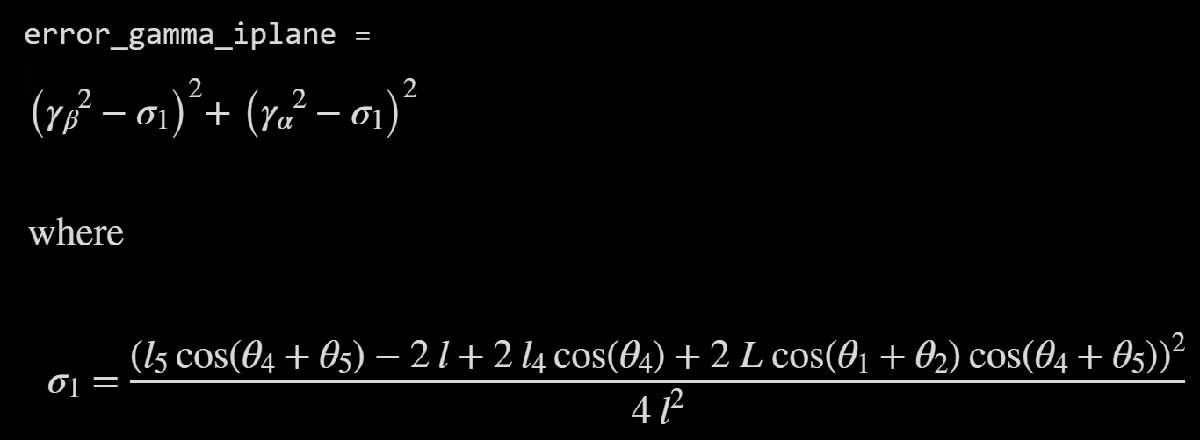

syms gamma_alpha gamma_beta real positive
% Doubly coupled mounting condition
error_gamma_iplane = simplify((gamma_alpha^2 - ht_e__o_swing_ampZ_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__o_lift_ampY_constMinp_sq)^2, 'Steps', 10)

$$error\_gamma\_iplane = \begin{array}{l} {\left(\frac{{\left(\sigma_{1}+2\,l_{6}\,\sigma_{3}-\sigma_{2}\right)}^{2}}{4\,{\left(\sigma_{1}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{3}\right)}^{2}}-{\gamma_{\alpha }}^{2}\right)}^{2}+{\left(\frac{{\left(2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-\sigma_{1}+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)+2\,l_{3}\,\sigma_{4}-\sigma_{2}\right)}^{2}}{4\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{4}\right)}^{2}}-{\gamma_{\beta }}^{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\\ \sigma_{3}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{4}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

error_gamma_oplane = simplify((gamma_alpha^2 - ht_e__o_swing_amp_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__o_lift_amp_constMinp_sq)^2, 'Steps', 10)

%%%%%%%%%%%%%%%%%% Swing Lever, Lift Coupled
error_gamma_L_iplane = simplify((gamma_alpha^2 - ht_e__oL_swing_ampZ_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__oL_lift_ampY_constMinp_sq)^2, 'Steps', 10)

$$error\_gamma\_L\_iplane = \begin{array}{l} {\left(\frac{{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{6}-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\sigma_{4}\right)}^{2}}{4\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{4}\right)}^{2}}-{\gamma_{\alpha }}^{2}\right)}^{2}+{\left({\gamma_{\beta }}^{2}-\frac{{\left(\frac{l_{2}\,\sigma_{1}}{2}-\frac{l_{2}\,\sigma_{2}}{2}+l_{1}\,\sin\left(\theta_{1}-\frac{\pi }{12\,l}\right)-l_{1}\,\sin\left(\theta_{1}+\frac{\pi }{12\,l}\right)+2\,\sigma_{3}\,\sigma_{5}+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}}{4\,{\sigma_{3}}^{2}\,{\sigma_{5}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{4}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{5}=\sigma_{6}+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

error_gamma_L_oplane = simplify((gamma_alpha^2 - ht_e__oL_swing_amp_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__oL_lift_amp_constMinp_sq)^2, 'Steps', 10)

$$error\_gamma\_L\_oplane = \begin{array}{l} {\left({\gamma_{\alpha }}^{2}+\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{8}-2\,l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+2\,l_{1}\,\cos\left(\theta_{1}\right)-2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{6}\,\sigma_{6}\right)}^{2}}{16\,{\sigma_{5}}^{2}\,{\left(l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\sigma_{6}\right)}^{2}}\right)}^{2}+{\left({\gamma_{\beta }}^{2}-\frac{{\left(l_{1}\,\cos\left(\sigma_{3}\right)-l_{1}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{2}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{2}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{2}\,\sin\left(\sigma_{2}\right)}{2}+l_{1}\,\sin\left(\sigma_{3}\right)-l_{1}\,\sin\left(\sigma_{4}\right)+2\,\sigma_{5}\,\sigma_{7}+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}}{4\,{\sigma_{5}}^{2}\,{\sigma_{7}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}+\theta_{2}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{1}+\theta_{2}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{1}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{1}+\frac{\pi }{12\,l}\\ \sigma_{5}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{6}=\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{7}=\sigma_{8}+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{8}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

%%%%%%%%%%%%%%%%%% Swing Coupled, Lift Lever
error_gamma_S_iplane = simplify((gamma_alpha^2 - ht_e__oS_swing_ampZ_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__oS_lift_ampY_constMinp_sq)^2, 'Steps', 10)

$$error\_gamma\_S\_iplane = \begin{array}{l} {\left(\frac{{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{6}-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\sigma_{4}\right)}^{2}}{4\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{4}\right)}^{2}}-{\gamma_{\beta }}^{2}\right)}^{2}+{\left({\gamma_{\alpha }}^{2}-\frac{{\left(\frac{l_{5}\,\sigma_{1}}{2}-\frac{l_{5}\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}-\frac{\pi }{12\,l}\right)-l_{4}\,\sin\left(\theta_{4}+\frac{\pi }{12\,l}\right)+2\,\sigma_{3}\,\sigma_{5}+L\,\sigma_{1}-L\,\sigma_{2}\right)}^{2}}{4\,{\sigma_{3}}^{2}\,{\sigma_{5}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\right)\\ \sigma_{2}=\sin\left(\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\right)\\ \sigma_{3}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{4}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{5}=\sigma_{6}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{6}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right) \end{array}$$

error_gamma_S_oplane = simplify((gamma_alpha^2 - ht_e__oS_swing_amp_constMinp_sq)^2 ...
    + (gamma_beta^2 - ht_e__oS_lift_amp_constMinp_sq)^2, 'Steps', 10)

$$error\_gamma\_S\_oplane = \begin{array}{l} {\left({\gamma_{\beta }}^{2}+\frac{\left(2\,\cos\left(\frac{\pi }{6\,l}\right)-2\right)\,{\left(2\,L\,\cos\left(\theta_{4}+\theta_{5}\right)-2\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{8}-2\,l_{1}\,\cos\left(\theta_{1}\right)+2\,l_{4}\,\cos\left(\theta_{4}\right)-2\,l_{3}\,\sigma_{6}\right)}^{2}}{16\,{\sigma_{5}}^{2}\,{\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\sigma_{6}\right)}^{2}}\right)}^{2}+{\left({\gamma_{\alpha }}^{2}-\frac{{\left(l_{4}\,\cos\left(\sigma_{3}\right)-l_{4}\,\cos\left(\sigma_{4}\right)+L\,\cos\left(\sigma_{1}\right)-L\,\cos\left(\sigma_{2}\right)+\frac{l_{5}\,\cos\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\cos\left(\sigma_{2}\right)}{2}\right)}^{2}+{\left(\frac{l_{5}\,\sin\left(\sigma_{1}\right)}{2}-\frac{l_{5}\,\sin\left(\sigma_{2}\right)}{2}+l_{4}\,\sin\left(\sigma_{3}\right)-l_{4}\,\sin\left(\sigma_{4}\right)+2\,\sigma_{5}\,\sigma_{7}+L\,\sin\left(\sigma_{1}\right)-L\,\sin\left(\sigma_{2}\right)\right)}^{2}}{4\,{\sigma_{5}}^{2}\,{\sigma_{7}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\theta_{4}+\theta_{5}-\frac{\pi }{12\,l}\\ \sigma_{2}=\theta_{4}+\theta_{5}+\frac{\pi }{12\,l}\\ \sigma_{3}=\theta_{4}-\frac{\pi }{12\,l}\\ \sigma_{4}=\theta_{4}+\frac{\pi }{12\,l}\\ \sigma_{5}=\sin\left(\frac{\pi }{12\,l}\right)\\ \sigma_{6}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{7}=\sigma_{8}+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right)\\ \sigma_{8}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right) \end{array}$$

% % % LEGACY CODE, NOT SUPPORTED
% % error_gamma_alpha = subs((-ht_e__o_swing_ampZ_constMinp_sq - gamma_alpha)^2, l, rhs(cond_3))
% % error_gamma_beta = subs((-ht_e__o_lift_ampY_constMinp_sq - gamma_beta)^2, l, lhs(cond_3))
% % error_gamma = error_gamma_alpha + error_gamma_beta

Let's try keeping $l$ intact in the optimization,

% % error_gamma_lintact = (-ht_e__o_lift_ampY_constMinp_sq - gamma_beta)^2 + (-ht_e__o_swing_ampZ_constMinp_sq - gamma_alpha)^2
% Let's us now define a design vector, 'x' with the kinematic chain
% parameters: link lengths and CUMULATIVE joint angles.
% This will help us setup the fmincon approach in the next section to
% design for the required lift and swing amplification.
% x = sym('x_%d',[13 1]);
x = sym('x_%d',[14 1]); % new formulation including the coupled chain length

% % Each element in x maps to the following kinematic parameters
% % x(1)  -- l_1                               % link lengths of lift
% % x(2)  -- l_2
% % x(3)  -- l_3
% % x(4)  -- l_4                               % link lengths of swing
% % x(5)  -- l_5
% % x(6)  -- l_6
% % x(7)  -- theta_1                           % cum joint angles of lift
% % x(8)  -- theta_1 + theta_2
% % x(9)  -- theta_1 + theta_2 + theta_3
% % x(10) -- theta_4                           % cum joint angles of swing
% % x(11) -- theta_4 + theta_5
% % x(12) -- theta_4 + theta_5 + theta_6
% % x(13) -- L                                 % Length of the leg
% % x(14) -- l                                 % Length of coupled chain

% Redefine error_gamma, and kinematic conditions with x:
% The conditions are also strict equality nonlinear constraints and hence,
% we want to express it in the fmincon's ceq(x) = 0 structure.
cond_1_x = simplify(subs(cond_1, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$cond\_1\_x = x_{1}\,\sin\left(x_{7}\right)+x_{2}\,\sin\left(x_{8}\right)+x_{3}\,\sin\left(x_{9}\right)=0$$

cond_2_x = simplify(subs(cond_2, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$cond\_2\_x = x_{4}\,\sin\left(x_{10}\right)+x_{5}\,\sin\left(x_{11}\right)+x_{6}\,\sin\left(x_{12}\right)=0$$

% cond_3_x = subs(cond_3, [l_1, l_2, l_3, l_4, l_5, l_6, ...
%                         sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
%                         cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
%                         sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
%                         cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), L, l], ...
%                         [x(1), x(2), x(3), x(4), x(5), x(6), ...
%                         sin(x(7)), sin(x(8)), sin(x(9)), ...
%                         cos(x(7)), cos(x(8)), cos(x(9)), ...
%                         sin(x(10)), sin(x(11)), sin(x(12)), ...
%                         cos(x(10)), cos(x(11)), cos(x(12)), x(13), x(14)]);
% cond_3_x = simplify(lhs(cond_3_x) - rhs(cond_3_x)) == 0 % express it as equal to zero for fmincon structure compliance
cond_3_s_x = simplify(subs(cond_3_s, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]));
cond_3_s_x = simplify(lhs(cond_3_s_x) - rhs(cond_3_s_x)) == 0 

$$cond\_3\_s\_x = x_{14}-x_{4}\,\cos\left(x_{10}\right)-x_{5}\,\cos\left(x_{11}\right)-x_{6}\,\cos\left(x_{12}\right)=0$$

cond_3_l_x = simplify(subs(cond_3_l, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]));
cond_3_l_x = simplify(lhs(cond_3_l_x) - rhs(cond_3_l_x)) == 0

$$cond\_3\_l\_x = x_{14}-x_{1}\,\cos\left(x_{7}\right)-x_{2}\,\cos\left(x_{8}\right)-x_{3}\,\cos\left(x_{9}\right)=0$$

error_gamma_iplane_x = simplify(subs(error_gamma_iplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_iplane\_x = \begin{array}{l} {\left({\gamma_{\alpha }}^{2}-\frac{{\left(x_{5}\,\cos\left(x_{11}\right)+2\,x_{6}\,\cos\left(x_{12}\right)-\sigma_{1}\right)}^{2}}{4\,{\left(x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\right)}^{2}}\right)}^{2}+{\left(\frac{{\left(2\,x_{1}\,\cos\left(x_{7}\right)+2\,x_{2}\,\cos\left(x_{8}\right)+2\,x_{3}\,\cos\left(x_{9}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-x_{5}\,\cos\left(x_{11}\right)-\sigma_{1}\right)}^{2}}{4\,{\left(x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\right)}^{2}}-{\gamma_{\beta }}^{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=2\,x_{13}\,\cos\left(x_{8}\right)\,\cos\left(x_{11}\right) \end{array}$$

error_gamma_oplane_x = simplify(subs(error_gamma_oplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_oplane\_x = \begin{array}{l} {\left({\gamma_{\alpha }}^{2}+\frac{\left(2\,\cos\left(\frac{\pi }{6\,x_{14}}\right)-2\right)\,\left(4\,{x_{6}}^{2}\,{\cos\left(x_{12}\right)}^{2}-4\,{x_{4}}^{2}\,{\cos\left(x_{10}\right)}^{2}+4\,{x_{13}}^{2}\,{\cos\left(x_{8}\right)}^{2}+4\,{x_{4}}^{2}+{x_{5}}^{2}+2\,x_{5}\,x_{6}\,\cos\left(\theta_{6}\right)+4\,x_{5}\,x_{13}\,\cos\left(x_{8}\right)+2\,x_{5}\,x_{6}\,\cos\left(x_{11}\right)\,\cos\left(x_{12}\right)+4\,x_{4}\,x_{5}\,\sin\left(x_{10}\right)\,\sin\left(x_{11}\right)-2\,x_{5}\,x_{6}\,\sin\left(x_{11}\right)\,\sin\left(x_{12}\right)-8\,x_{5}\,x_{13}\,\cos\left(x_{8}\right)\,{\cos\left(x_{11}\right)}^{2}+8\,x_{4}\,x_{13}\,\cos\left(x_{8}\right)\,\sin\left(x_{10}\right)\,\sin\left(x_{11}\right)-8\,x_{6}\,x_{13}\,\cos\left(x_{8}\right)\,\cos\left(x_{11}\right)\,\cos\left(x_{12}\right)\right)}{16\,\sigma_{1}\,{\left(x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\right)}^{2}}\right)}^{2}+{\left({\gamma_{\beta }}^{2}-\frac{\sigma_{1}\,{\left(2\,x_{1}\,\cos\left(x_{7}\right)+2\,x_{2}\,\cos\left(x_{8}\right)+2\,x_{3}\,\cos\left(x_{9}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-x_{5}\,\cos\left(x_{11}\right)-2\,x_{13}\,\cos\left(x_{8}\right)\,\cos\left(x_{11}\right)\right)}^{2}+\sigma_{1}\,{\left(2\,x_{1}\,\sin\left(x_{7}\right)+x_{2}\,\sin\left(x_{8}\right)+2\,x_{13}\,\sin\left(x_{8}\right)\right)}^{2}}{4\,\sigma_{1}\,{\left(x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\right)}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\frac{\pi }{12\,x_{14}}\right)}^{2} \end{array}$$

error_gamma_L_iplane_x = simplify(subs(error_gamma_L_iplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_L\_iplane\_x = \begin{array}{l} {\left(\frac{{\left(2\,x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-2\,x_{5}\,\cos\left(x_{11}\right)-2\,x_{6}\,\cos\left(x_{12}\right)+2\,x_{13}\,\cos\left(x_{8}\right)\right)}^{2}}{4\,{\left(x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\right)}^{2}}-{\gamma_{\alpha }}^{2}\right)}^{2}+{\left({\gamma_{\beta }}^{2}-\frac{{\left(x_{1}\,\sin\left(x_{7}-\frac{\pi }{12\,x_{14}}\right)-x_{1}\,\sin\left(x_{7}+\frac{\pi }{12\,x_{14}}\right)+\frac{x_{2}\,\sigma_{2}}{2}-\frac{x_{2}\,\sigma_{3}}{2}+x_{13}\,\sigma_{2}-x_{13}\,\sigma_{3}+2\,\sigma_{4}\,\sigma_{1}\right)}^{2}}{4\,{\sigma_{4}}^{2}\,{\sigma_{1}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\\ \sigma_{2}=\sin\left(x_{8}-\frac{\pi }{12\,x_{14}}\right)\\ \sigma_{3}=\sin\left(x_{8}+\frac{\pi }{12\,x_{14}}\right)\\ \sigma_{4}=\sin\left(\frac{\pi }{12\,x_{14}}\right) \end{array}$$

error_gamma_L_oplane_x = simplify(subs(error_gamma_L_oplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_L\_oplane\_x = \begin{array}{l} {\left({\gamma_{\beta }}^{2}-\frac{{\left(x_{1}\,\cos\left(\sigma_{4}\right)-x_{1}\,\cos\left(\sigma_{5}\right)+\frac{x_{2}\,\cos\left(\sigma_{2}\right)}{2}-\frac{x_{2}\,\cos\left(\sigma_{3}\right)}{2}+x_{13}\,\cos\left(\sigma_{2}\right)-x_{13}\,\cos\left(\sigma_{3}\right)\right)}^{2}+{\left(x_{1}\,\sin\left(\sigma_{4}\right)-x_{1}\,\sin\left(\sigma_{5}\right)+\frac{x_{2}\,\sin\left(\sigma_{2}\right)}{2}-\frac{x_{2}\,\sin\left(\sigma_{3}\right)}{2}+x_{13}\,\sin\left(\sigma_{2}\right)-x_{13}\,\sin\left(\sigma_{3}\right)+2\,\sigma_{6}\,\sigma_{1}\right)}^{2}}{4\,{\sigma_{6}}^{2}\,{\sigma_{1}}^{2}}\right)}^{2}+{\left({\gamma_{\alpha }}^{2}+\frac{\left(2\,\cos\left(\frac{\pi }{6\,x_{14}}\right)-2\right)\,{\left(2\,x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-2\,x_{5}\,\cos\left(x_{11}\right)-2\,x_{6}\,\cos\left(x_{12}\right)+2\,x_{13}\,\cos\left(x_{8}\right)\right)}^{2}}{16\,{\sigma_{6}}^{2}\,{\left(x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\right)}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\\ \sigma_{2}=x_{8}-\frac{\pi }{12\,x_{14}}\\ \sigma_{3}=x_{8}+\frac{\pi }{12\,x_{14}}\\ \sigma_{4}=x_{7}-\frac{\pi }{12\,x_{14}}\\ \sigma_{5}=x_{7}+\frac{\pi }{12\,x_{14}}\\ \sigma_{6}=\sin\left(\frac{\pi }{12\,x_{14}}\right) \end{array}$$

error_gamma_S_iplane_x = simplify(subs(error_gamma_S_iplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_S\_iplane\_x = \begin{array}{l} {\left(\frac{{\left(2\,x_{1}\,\cos\left(x_{7}\right)+2\,x_{2}\,\cos\left(x_{8}\right)+2\,x_{3}\,\cos\left(x_{9}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-x_{5}\,\cos\left(x_{11}\right)-2\,x_{13}\,\cos\left(x_{11}\right)\right)}^{2}}{4\,{\left(x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\right)}^{2}}-{\gamma_{\beta }}^{2}\right)}^{2}+{\left({\gamma_{\alpha }}^{2}-\frac{{\left(x_{4}\,\sin\left(x_{10}-\frac{\pi }{12\,x_{14}}\right)-x_{4}\,\sin\left(x_{10}+\frac{\pi }{12\,x_{14}}\right)+\frac{x_{5}\,\sigma_{2}}{2}-\frac{x_{5}\,\sigma_{3}}{2}+x_{13}\,\sigma_{2}-x_{13}\,\sigma_{3}+2\,\sigma_{4}\,\sigma_{1}\right)}^{2}}{4\,{\sigma_{4}}^{2}\,{\sigma_{1}}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\\ \sigma_{2}=\sin\left(x_{11}-\frac{\pi }{12\,x_{14}}\right)\\ \sigma_{3}=\sin\left(x_{11}+\frac{\pi }{12\,x_{14}}\right)\\ \sigma_{4}=\sin\left(\frac{\pi }{12\,x_{14}}\right) \end{array}$$

error_gamma_S_oplane_x = simplify(subs(error_gamma_S_oplane, [l_1, l_2, l_3, l_4, l_5, l_6, ...
                        sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
                        cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
                        sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
                        cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), ...
                        theta_1+theta_2+theta_3, theta_1+theta_2, theta_1, ...
                        theta_4+theta_5+theta_6, theta_4+theta_5, theta_4, ...
                        L, l], ...
                        [x(1), x(2), x(3), x(4), x(5), x(6), ...
                        sin(x(7)), sin(x(8)), sin(x(9)), ...
                        cos(x(7)), cos(x(8)), cos(x(9)), ...
                        sin(x(10)), sin(x(11)), sin(x(12)), ...
                        cos(x(10)), cos(x(11)), cos(x(12)), ...
                        x(9), x(8), x(7), ...
                        x(12), x(11), x(10), ...
                        x(13), x(14)]))

$$error\_gamma\_S\_oplane\_x = \begin{array}{l} {\left({\gamma_{\alpha }}^{2}-\frac{{\left(x_{4}\,\cos\left(\sigma_{4}\right)-x_{4}\,\cos\left(\sigma_{5}\right)+\frac{x_{5}\,\cos\left(\sigma_{2}\right)}{2}-\frac{x_{5}\,\cos\left(\sigma_{3}\right)}{2}+x_{13}\,\cos\left(\sigma_{2}\right)-x_{13}\,\cos\left(\sigma_{3}\right)\right)}^{2}+{\left(x_{4}\,\sin\left(\sigma_{4}\right)-x_{4}\,\sin\left(\sigma_{5}\right)+\frac{x_{5}\,\sin\left(\sigma_{2}\right)}{2}-\frac{x_{5}\,\sin\left(\sigma_{3}\right)}{2}+x_{13}\,\sin\left(\sigma_{2}\right)-x_{13}\,\sin\left(\sigma_{3}\right)+2\,\sigma_{6}\,\sigma_{1}\right)}^{2}}{4\,{\sigma_{6}}^{2}\,{\sigma_{1}}^{2}}\right)}^{2}+{\left({\gamma_{\beta }}^{2}+\frac{\left(2\,\cos\left(\frac{\pi }{6\,x_{14}}\right)-2\right)\,{\left(2\,x_{1}\,\cos\left(x_{7}\right)+2\,x_{2}\,\cos\left(x_{8}\right)+2\,x_{3}\,\cos\left(x_{9}\right)-2\,x_{4}\,\cos\left(x_{10}\right)-x_{5}\,\cos\left(x_{11}\right)-2\,x_{13}\,\cos\left(x_{11}\right)\right)}^{2}}{16\,{\sigma_{6}}^{2}\,{\left(x_{1}\,\cos\left(x_{7}\right)+x_{2}\,\cos\left(x_{8}\right)+x_{3}\,\cos\left(x_{9}\right)\right)}^{2}}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=x_{4}\,\cos\left(x_{10}\right)+x_{5}\,\cos\left(x_{11}\right)+x_{6}\,\cos\left(x_{12}\right)\\ \sigma_{2}=x_{11}-\frac{\pi }{12\,x_{14}}\\ \sigma_{3}=x_{11}+\frac{\pi }{12\,x_{14}}\\ \sigma_{4}=x_{10}-\frac{\pi }{12\,x_{14}}\\ \sigma_{5}=x_{10}+\frac{\pi }{12\,x_{14}}\\ \sigma_{6}=\sin\left(\frac{\pi }{12\,x_{14}}\right) \end{array}$$


%%%%% LEGACY CODE, NOT SUPPORTED
% error_gamma_x = simplify(subs(error_gamma, [l_1, l_2, l_3, l_4, l_5, l_6, ...
%                         sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
%                         cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
%                         sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
%                         cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), L, l], ...
%                         [x(1), x(2), x(3), x(4), x(5), x(6), ...
%                         sin(x(7)), sin(x(8)), sin(x(9)), ...
%                         cos(x(7)), cos(x(8)), cos(x(9)), ...
%                         sin(x(10)), sin(x(11)), sin(x(12)), ...
%                         cos(x(10)), cos(x(11)), cos(x(12)), x(13),
%                         x(14)])) % OLD FORMAT
% error_gamma_lintact_x = simplify(subs(error_gamma_lintact, [l_1, l_2, l_3, l_4, l_5, l_6, ...
%                         sin(theta_1), sin(theta_1+theta_2), sin(theta_1+theta_2+theta_3), ...
%                         cos(theta_1), cos(theta_1+theta_2), cos(theta_1+theta_2+theta_3), ...
%                         sin(theta_4), sin(theta_4+theta_5), sin(theta_4+theta_5+theta_6), ...
%                         cos(theta_4), cos(theta_4+theta_5), cos(theta_4+theta_5+theta_6), L, l], ...
%                         [x(1), x(2), x(3), x(4), x(5), x(6), ...
%                         sin(x(7)), sin(x(8)), sin(x(9)), ...
%                         cos(x(7)), cos(x(8)), cos(x(9)), ...
%                         sin(x(10)), sin(x(11)), sin(x(12)), ...
%                         cos(x(10)), cos(x(11)), cos(x(12)), x(13), x(14)]))

Now, the next step is to find the gradients of the error function and the nonlinear equality constraints. We might not use this, but it is still useful tot see the differentially flat directions,

% grad_cond_1_x = gradient(lhs(cond_1_x), x)
% grad_cond_2_x = gradient(lhs(cond_2_x), x)
% % grad_cond_3_x = gradient(lhs(cond_3_x), x) % old format without l
% grad_cond_3_l_x = gradient(lhs(cond_3_l_x), x)
% grad_cond_3_s_x = gradient(lhs(cond_3_s_x), x)
% % grad_error_gamma_x = simplify(gradient(error_gamma_x, x)) % OLD FORMAT
% grad_error_gamma_lintact_x = simplify(gradient(error_gamma_lintact_x, x)) 

Finally, compute the Hessian for the scalar objective function and constraint gradients,

% hess_cond_1_x = hessian(lhs(cond_1_x), x)
% hess_cond_2_x = hessian(lhs(cond_2_x), x)
% hess_cond_3_x = hessian(lhs(cond_3_x), x)
% hess_error_gamma_x = simplify(hessian(error_gamma_x, x))

Hessian is too complicated at the moment-- shelving for later. Also, the optimization already runs fast enough, so I don't think even a gradient is needed at the moment. But, it's good to see the differentially flat directions when we take the partial derivatives.

% % % Save everything ignoring the Hessian... OLD FORMAT WITHOUT 'l'
% % save('DASH_leg_kinematics_optimization.mat',...
% %     'cond_1_x','cond_2_x','cond_3_x',...
% %     'error_gamma_x',...
% %     'grad_cond_1_x','grad_cond_2_x','grad_cond_3_x',...
% %     'grad_error_gamma_x');

% % % % Save everything ignoring the Hessian... NEW FORMAT USE THIS!!
% % % save('DASH_leg_kinematics_optimization.mat',...
% % %     'cond_1_x','cond_2_x','cond_3_l_x','cond_3_s_x',...
% % %     'error_gamma_x',...
% % %     'grad_cond_1_x','grad_cond_2_x','grad_cond_3_l_x','grad_cond_3_s_x',...
% % %     'grad_error_gamma_lintact_x');

### Scalar objective function on swing and lift amplification factors

Let's use an fmincon approach with DASH's parameters as the initial condition and solve for chains with prescribed amplification factors. We shall consider multiple cases to ensure the airtightness of the design space.

% % % % % % The vector x contains the kinematic parameters we want to 
% % % % % % optimize over
% % x(1)  -- l_1                               % link lengths of lift
% % x(2)  -- l_2
% % x(3)  -- l_3
% % x(4)  -- l_4                               % link lengths of swing
% % x(5)  -- l_5
% % x(6)  -- l_6
% % x(7)  -- theta_1                           % cum joint angles of lift
% % x(8)  -- theta_1 + theta_2
% % x(9)  -- theta_1 + theta_2 + theta_3
% % x(10) -- theta_4                           % cum joint angles of swing
% % x(11) -- theta_4 + theta_5
% % x(12) -- theta_4 + theta_5 + theta_6
% % x(13) -- L                                 % Length of the leg
% % x(14) -- l                                 % Length of coupled chain

% Setup the bounds
lb = [0.1*ones(1,6), -3*pi/4*ones(1,6), 0.1, 0.1]; % l has the same limits as L
ub = [2*ones(1,6), 3*pi/4*ones(1,6), 3, 3];

% Compute the initial conditions from our current design and normalize the
% specs -- this will corresponding changes in the lengths for our design
% and maybe easier to work with
sRad = 1.3;
l1 = 1.1; l2 = 0.8;
theta1 = deg2rad(80); theta2 = -deg2rad(70);
theta3 = atan2(-l1*sin(theta1) -l2*sin(theta1+theta2), sRad -l1*cos(theta1) -l2*cos(theta1+theta2)) -theta2 -theta1; %appx step
l3 = norm([sRad-l1*cos(theta1)-l2*cos(theta1+theta2), -l1*sin(theta1)-l2*sin(theta1+theta2)]'); %appx step
l4 = 0.9; l5 = 0.8;
theta4 = deg2rad(80); theta5 = -deg2rad(80);
theta6 = atan2(-l4*sin(theta4) -l5*sin(theta4+theta5), sRad -l4*cos(theta4) -l5*cos(theta4+theta5)) -theta5 -theta4; %appx step
l6 = norm([sRad-l4*cos(theta4)-l5*cos(theta4+theta5), -l4*sin(theta4)-l5*sin(theta4+theta5)]'); %appx step
lnorm = @(l) l/sRad; 
l1 = lnorm(l1); l2 = lnorm(l2); l3 = lnorm(l3); l4 = lnorm(l4); l5 = lnorm(l5); l6 = lnorm(l6);
Ld = lnorm(3.5); ld = lnorm(sRad);

% Setup the initial conditions - DASH default values
x0 = [l1, l2, l3, ...
     l4, l5, l6, ...
     theta1, theta1+theta2, theta1+theta2+theta3, ...
     theta4, theta4+theta5, theta4+theta5+theta6, ...
     Ld, ld];

% Amplification factor for the first case
g_a = [2 0.5 1 1 2 3 2 3 4]'; 
g_b = [2 0.5 1 2 1 2 3 3 4]'; % (2,2) is very close to our starting condition
g_abyb = g_a./g_b;
% Each row corresponds to a new design requirement, and the fmincon
% solution has the same structure.

% Number of optimization runs:
runs = length(g_a);

% Setup the functions for the solver call
fxn = @DASH_err_gamma;
nonlincon = @DASH_constraint;
% % % % % hessianfxn = @DASH_err_gamma_hessian;
% Hessian not support at the moment since it is too complicated, need to
% check if the analytical results are expressed in the simples possible
% form.

% Set the nonexistent linear constraints as empty
A = []; b = []; Aeq = []; beq = [];

% Let's initialize the optimization output variables:
x = cell(1,runs); fval = cell(1,runs); exitF = cell(1,runs); bestx = cell(1,runs);

% Setup the error objective choice %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% p struct incorporates this; p.io == 0 --> simpler formulation
%                             p.io == 1 --> complex formulation
%                                   p.c == 0 --> doubly coupled
%                                   p.c == 1 --> S lever, L coupled
%                                   p.c == 2 --> S coupled, L lever
p.io = 1; p.c = 0;
% Add more text to the video to reflect the run condition.
switch p.io
    case 1
        ctext = ' Simple Err ';
    case 2
        ctext = ' Complex Err ';
end
switch p.c
    case 0
        ctext = [ctext 'Mount Swing Lift'];
    case 1
        ctext = [ctext 'Mount Lift'];
    case 2
        ctext = [ctext 'Mount Swing'];
end

% % % % % Set the fmincon options
% % % % options = optimoptions('fmincon',...
% % % %     'SpecifyObjectiveGradient',true,'SpecifyConstraintGradient',true); 
% ,'Display','off','HessianFcn',@hessianfxn
% The runs have been heavily tested and the problem is well constrained,
% hence we can turn off the display.
% Also, the hessian seems too complicated for the error function, hence,
% let's ignore it for now.

% Run fmincon iteratively for each amplification we need
for i = 1:runs
    % Solve
    [x{i}, fval{i}, exitF{i}, bestx{i}] = fmincon(@(x)fxn(x,g_a(i),g_b(i),p),x0,A,b,Aeq,beq,lb,ub,@(x)nonlincon(x,g_a(i),g_b(i))); % ,options
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

Alright, let's look at the objective functions evaluations to check what worked and what did not.

fval

fval = 1×9 cell array
    {[1.0201e-14]}    {[3.7543e-13]}    {[4.4557e-14]}    {[3.1479e-14]}    {[3.7812e-14]}    {[2.5673e-08]}    {[1.0085e-14]}    {[4.1702e-14]}    {[2.5435e-13]}


Seems like the cases asymmetric output trajectories cases could not be satisfied with the current leg mounting position. Let's generate some videos and output trajectory data to confirm this.

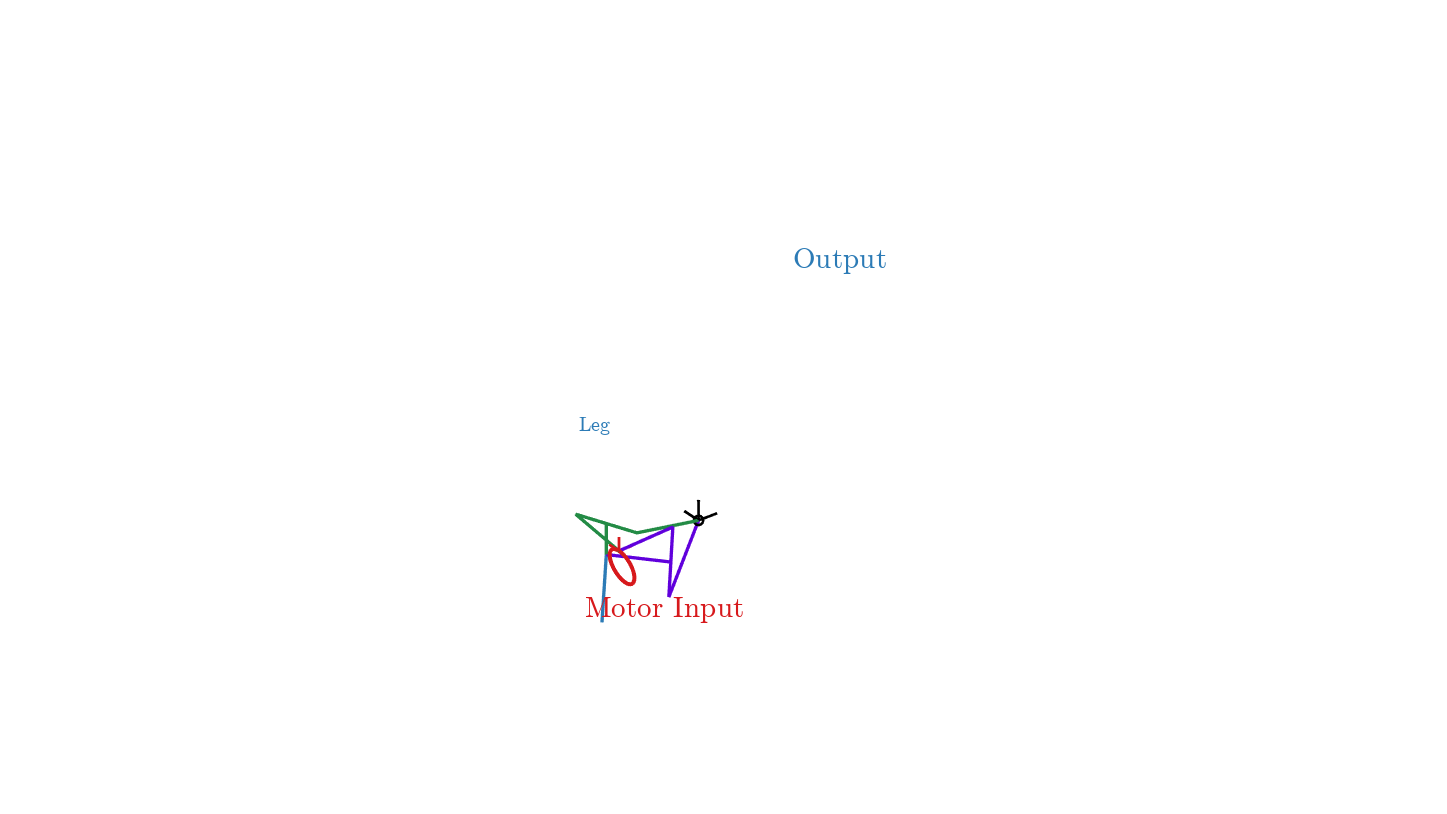

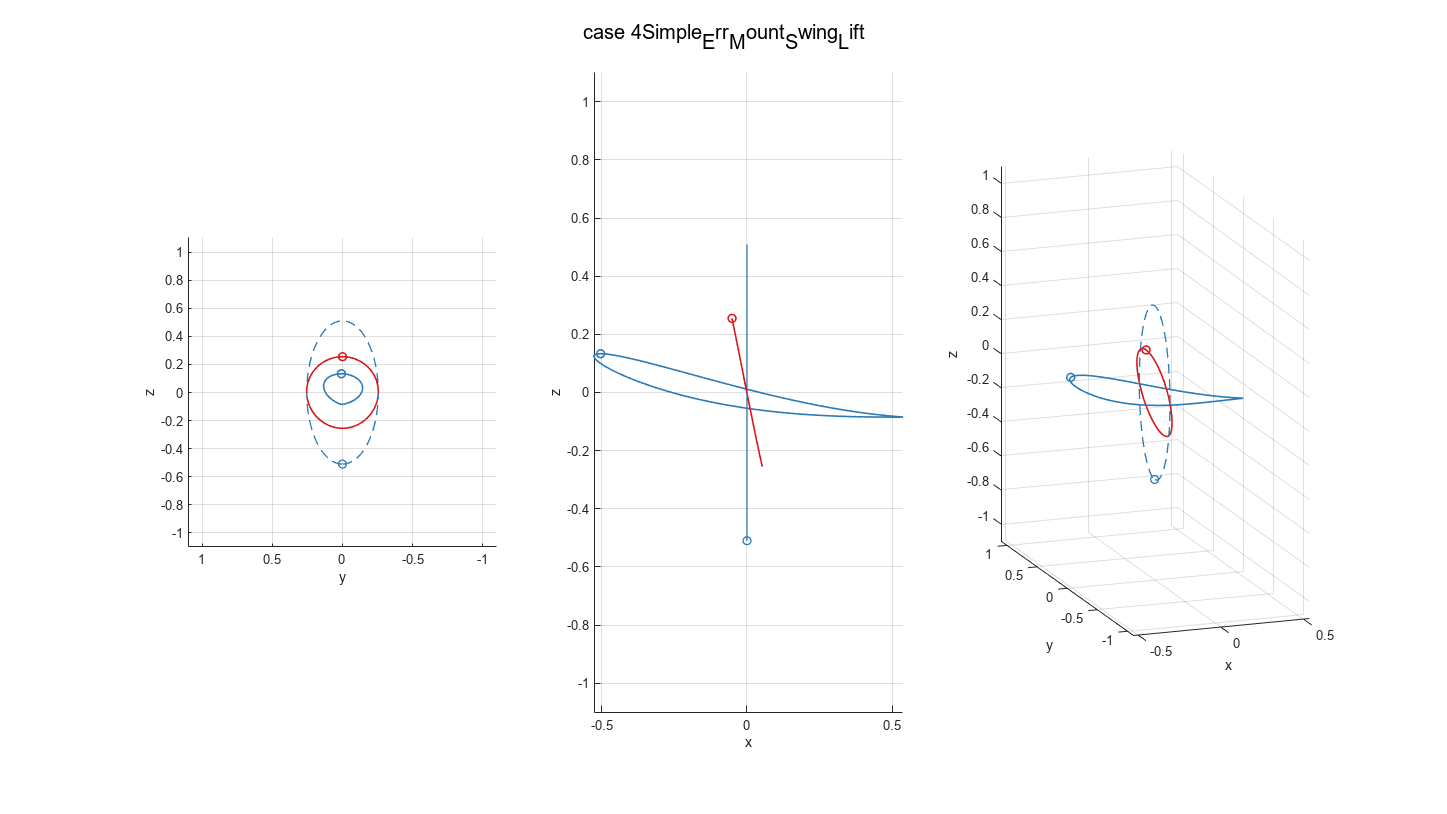

% Since we are using a 15degs input for a kinematic length of 1 unit, we
% can compute the maximum plotting space needed to compare different
% designs.
maxtrajsize = ceil(10*max([max(g_a) max(g_b)])*sin(deg2rad(15)))/10;

% Get the output trajectory plots for case 4
j = 4;

% Let's package these and create a function that will plot the results --
% here we are manually plotting just two cases we are specifically
% interested in. %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% IF VIDEOS ARE NOT NEEDED, DISABLE THE FLAG BELOW ~~~~~~~~~~~~~~~~~~~~~~~~
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    % Add video details only if a video is needed
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

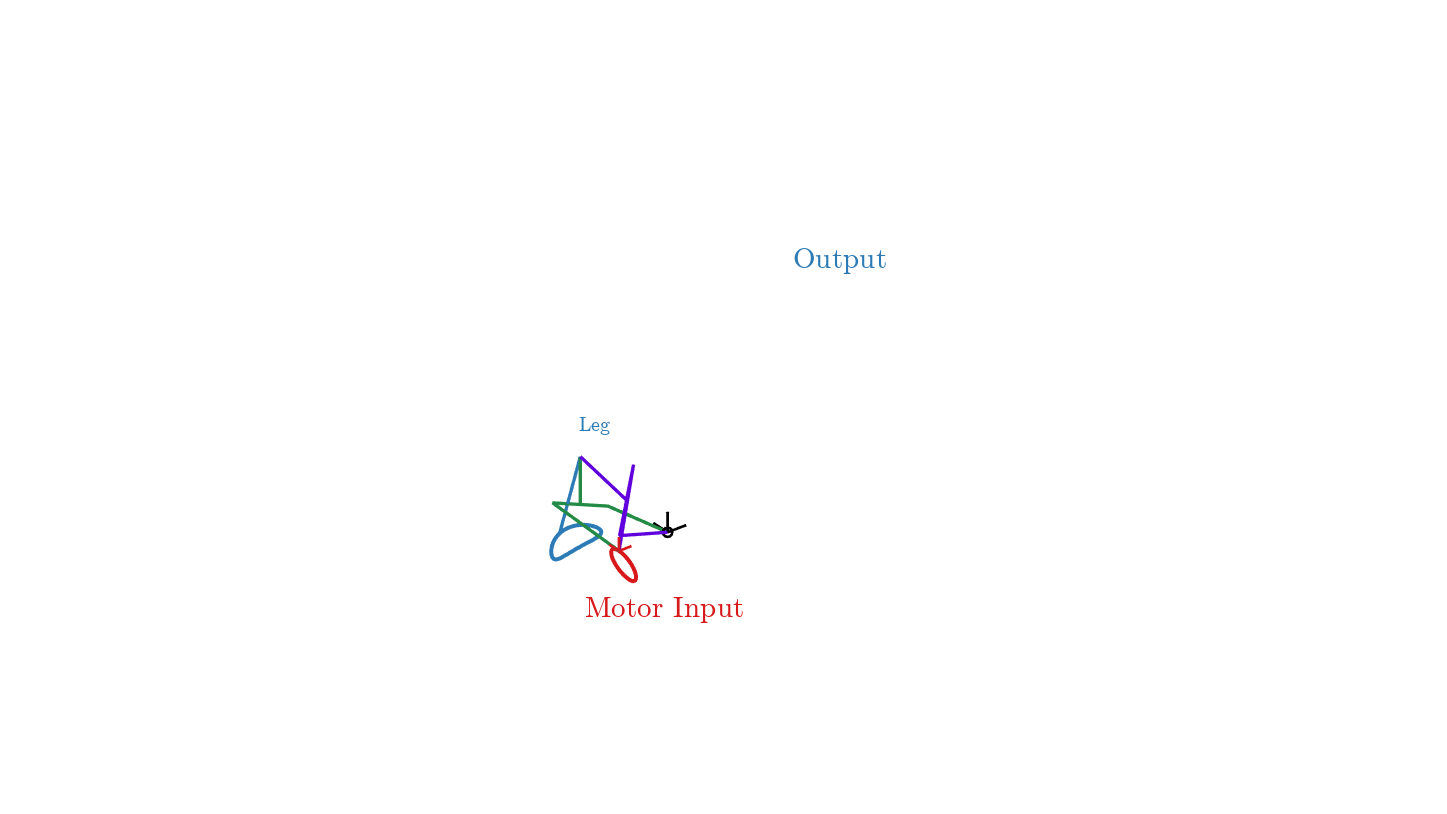

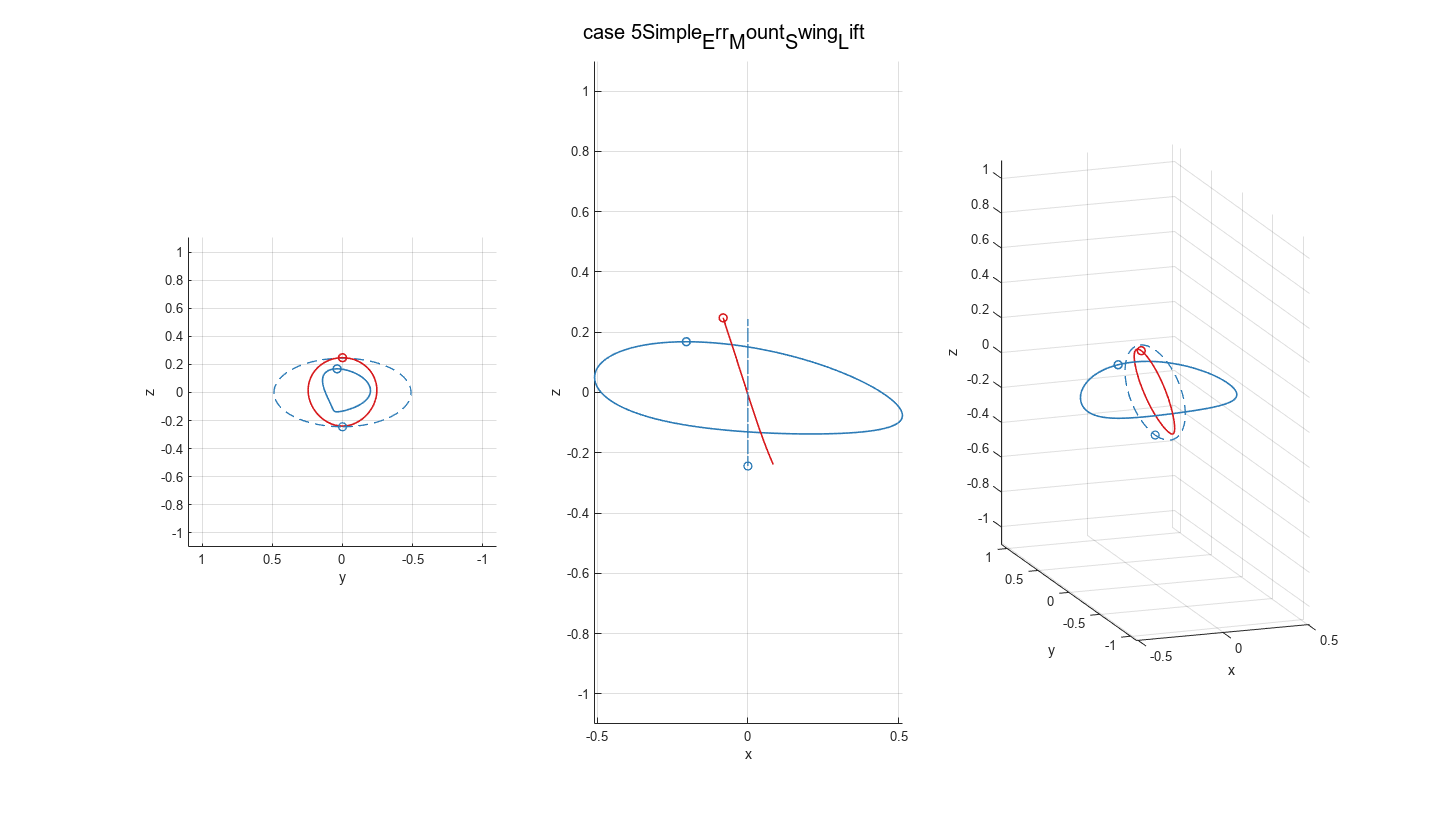

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 5;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

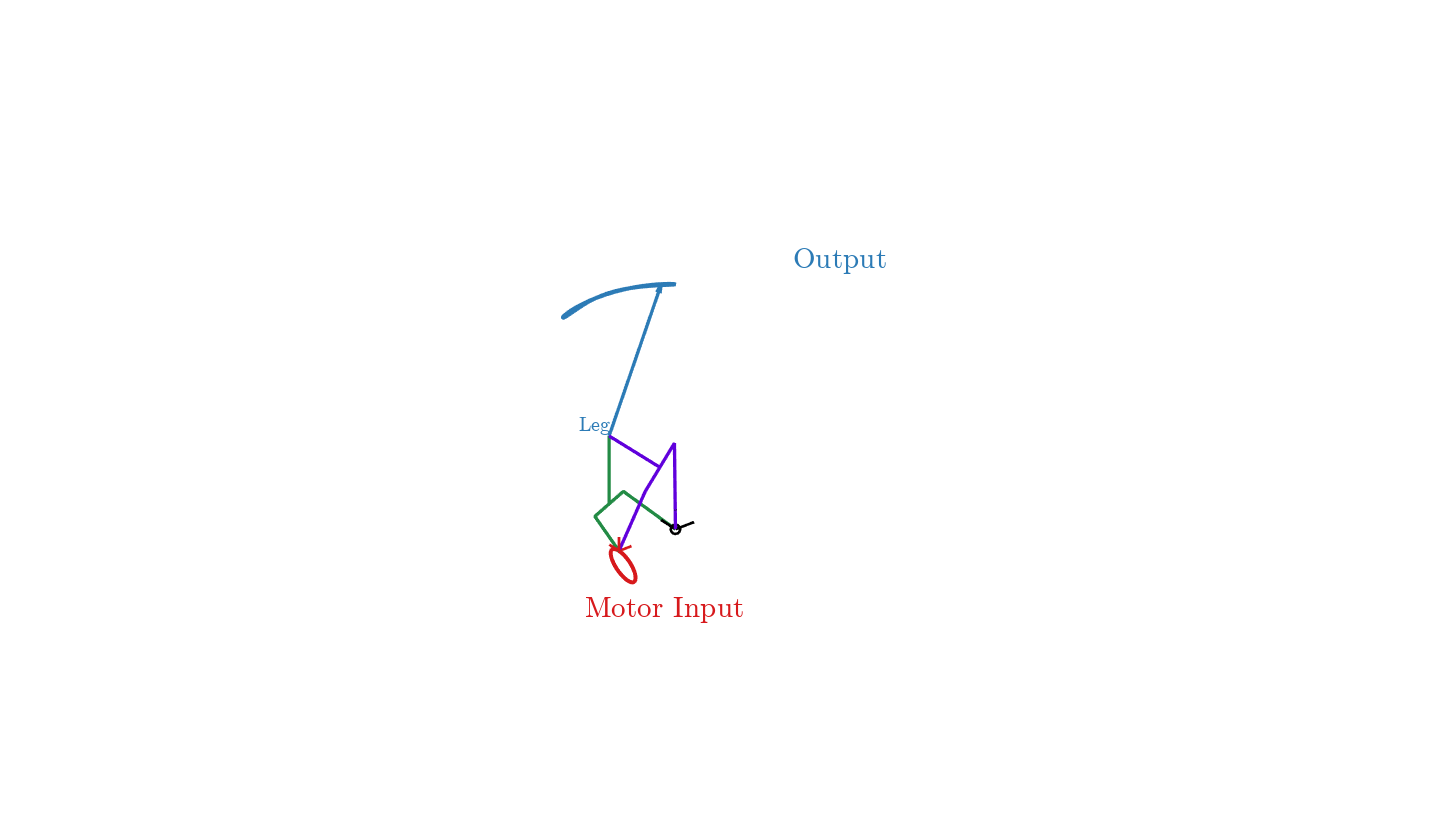

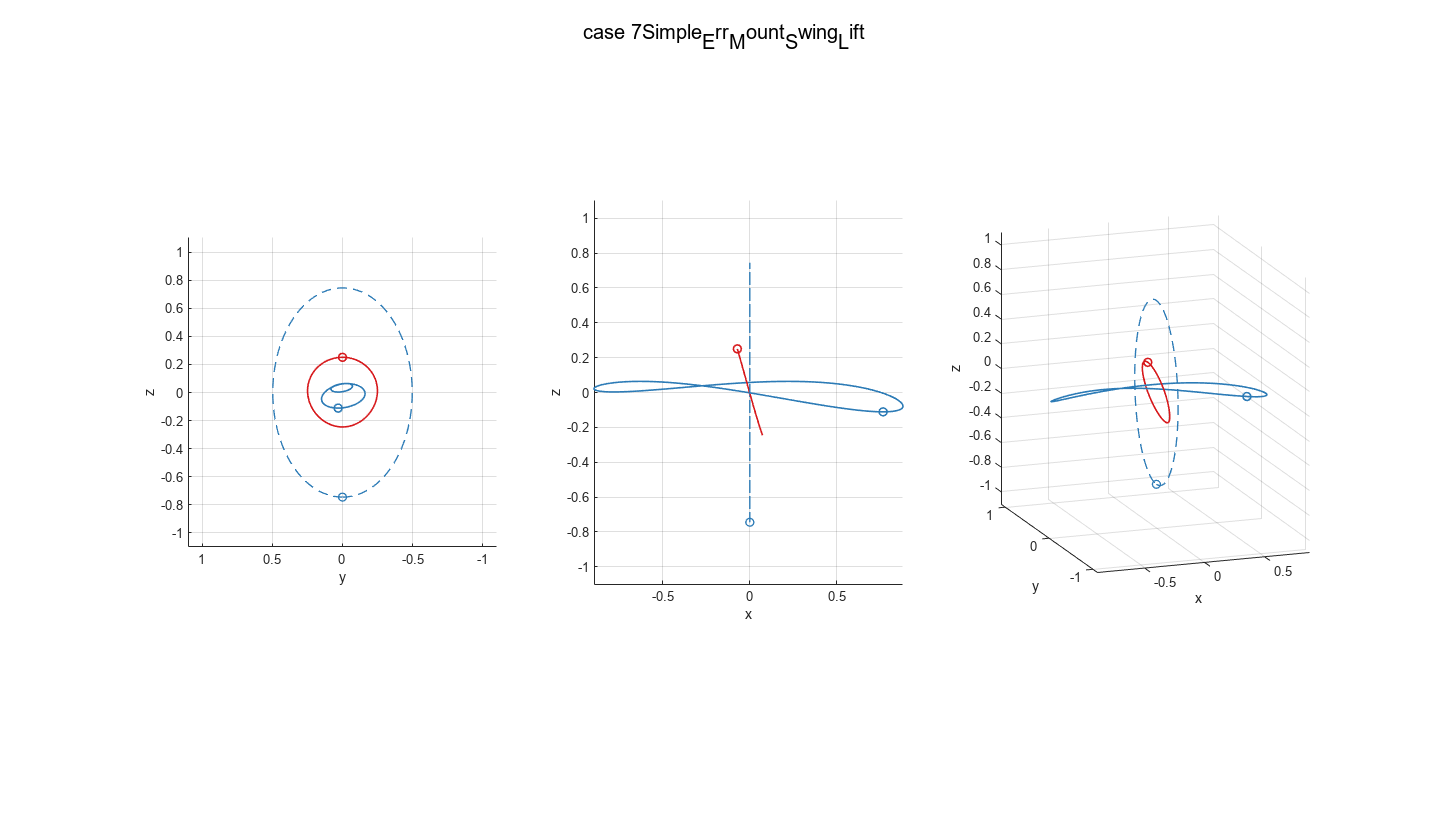

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 7;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

Next, we can look at the cases that worked.

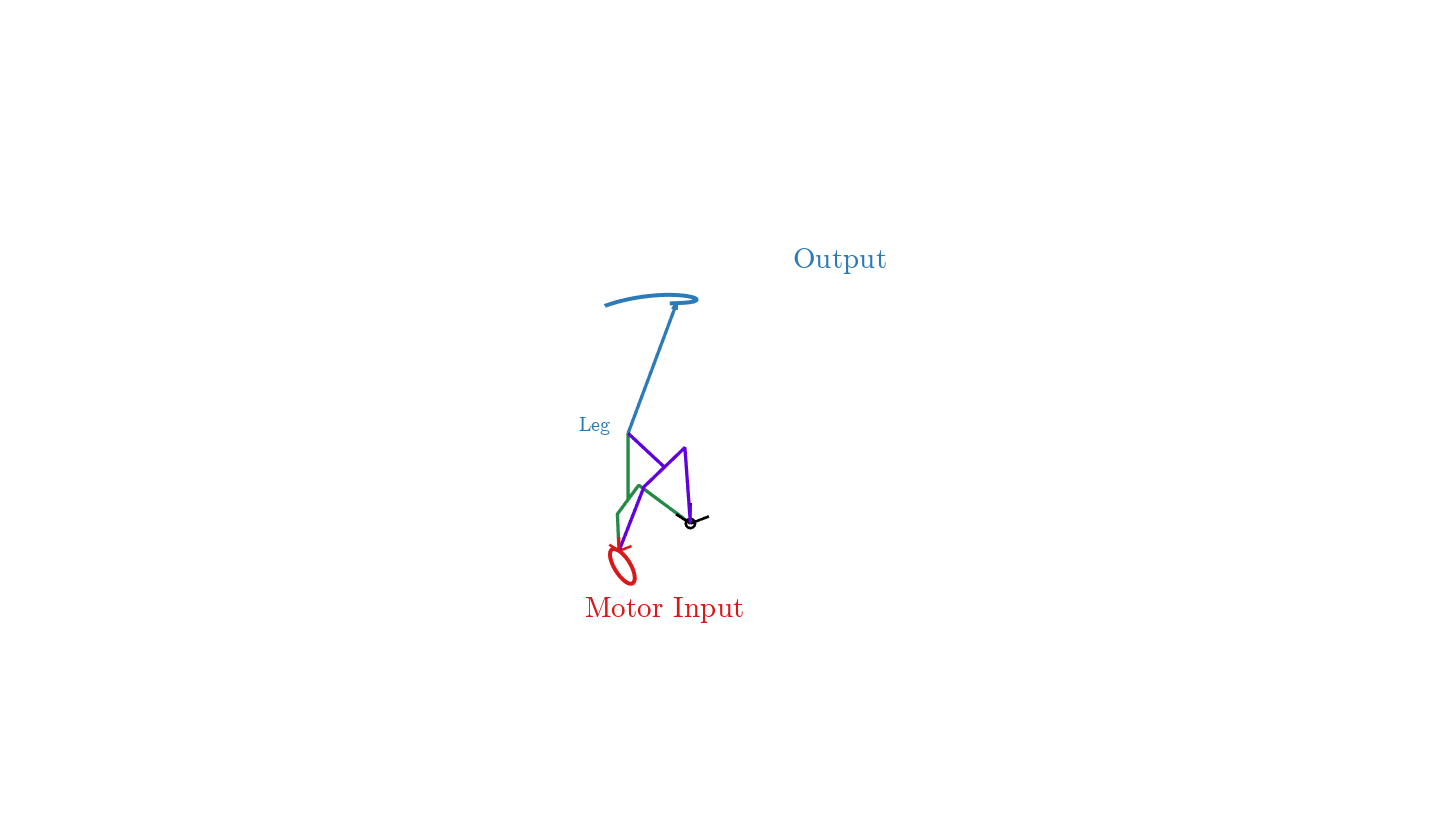

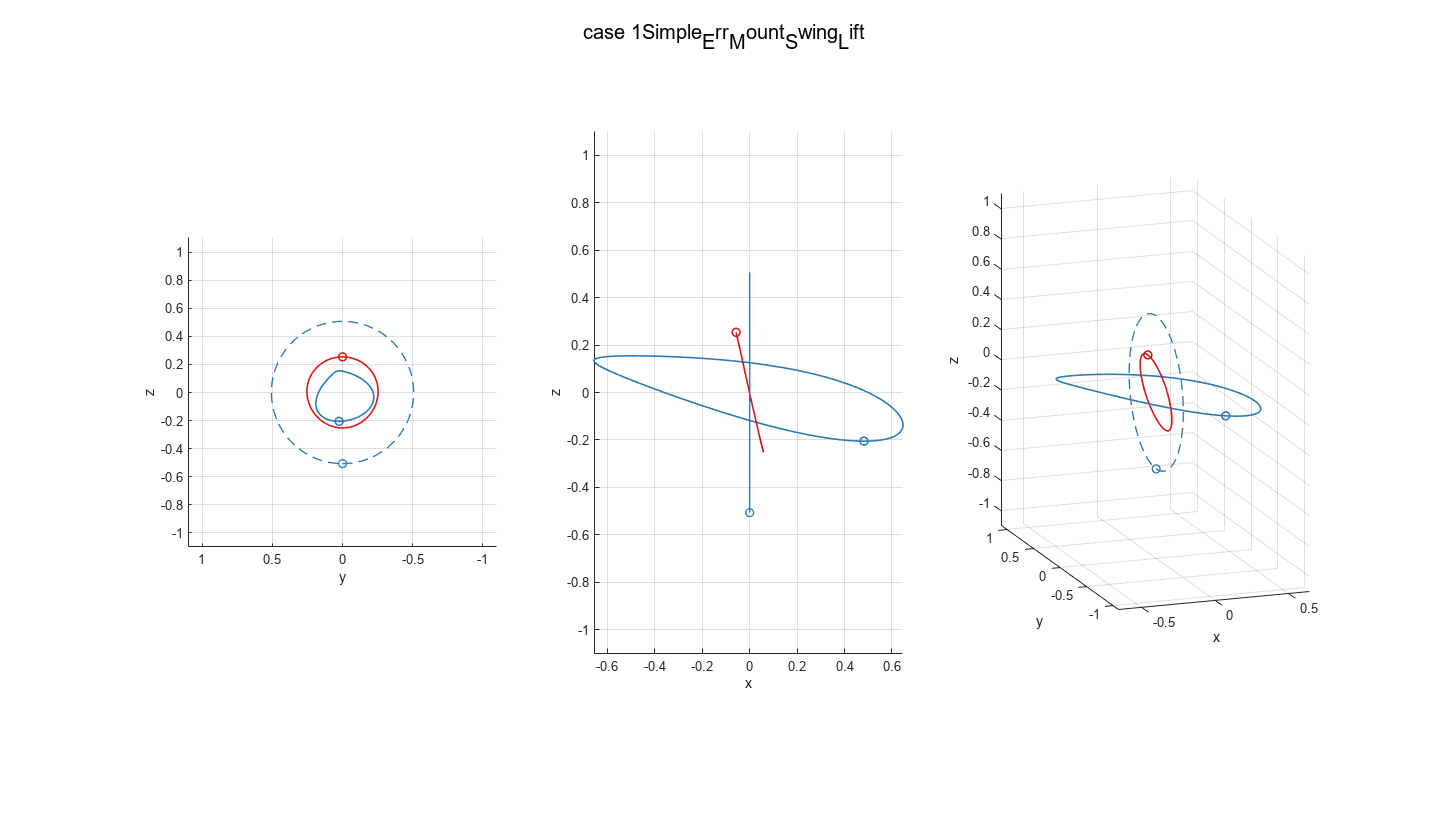

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 1;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

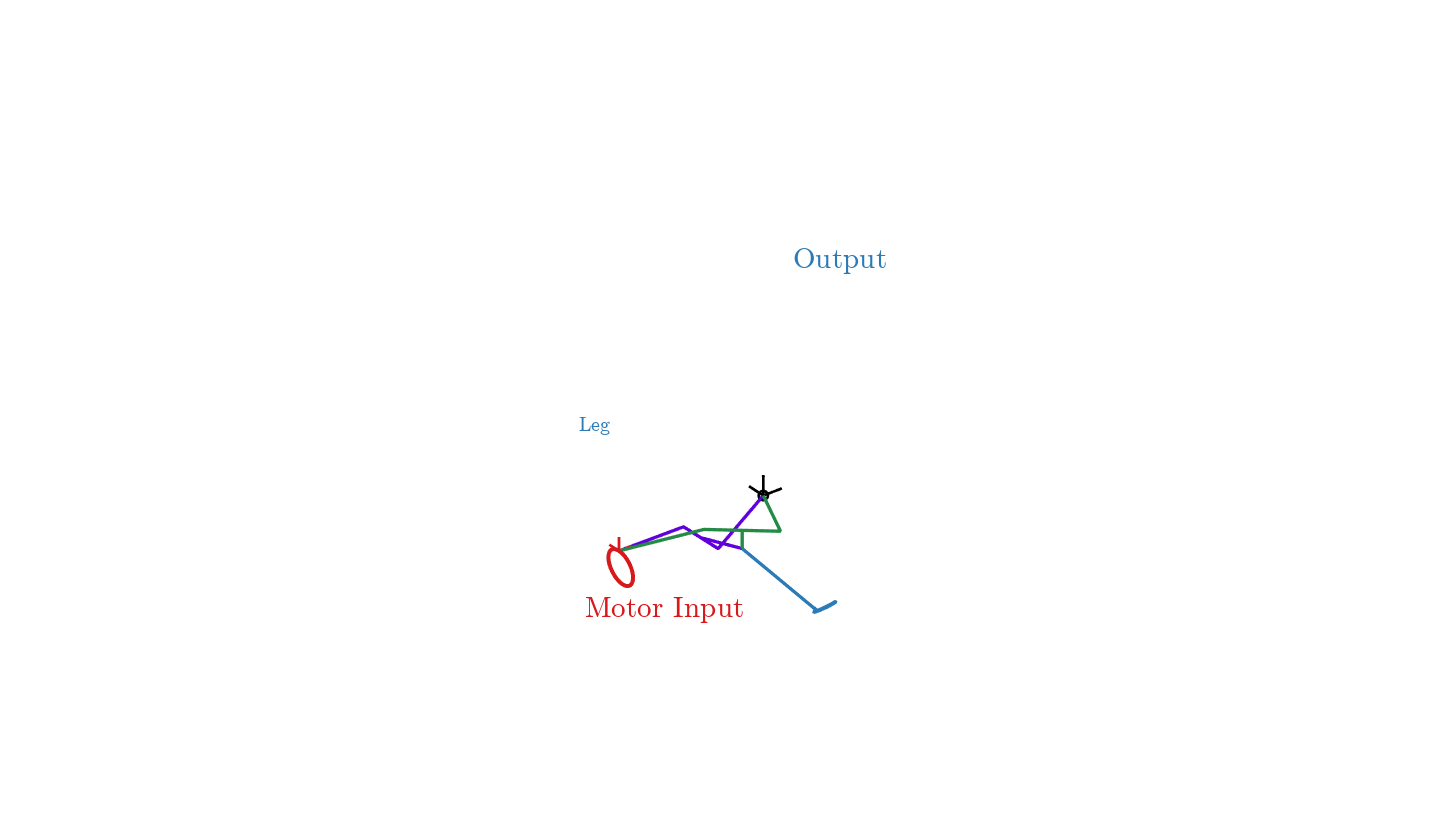

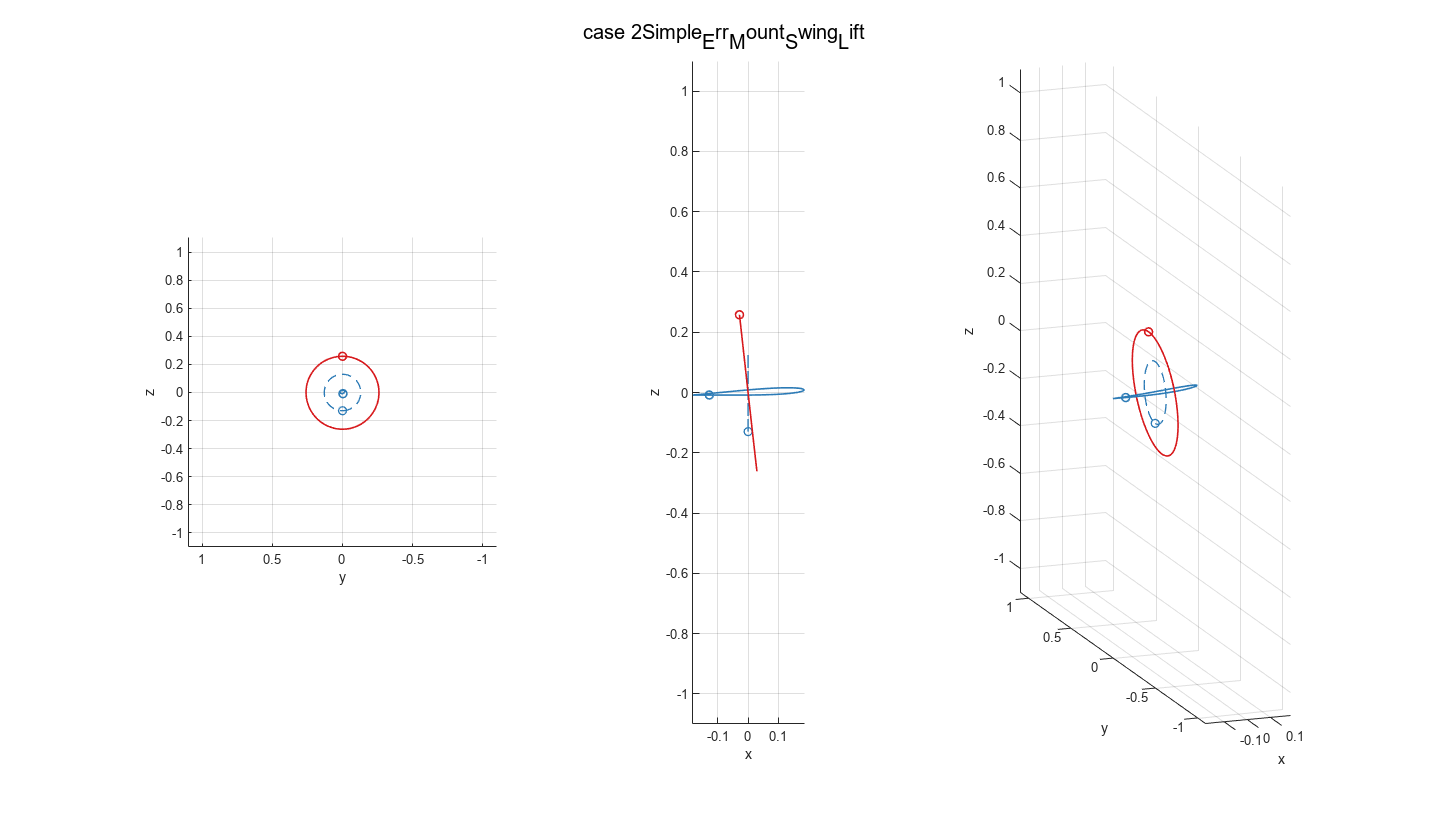

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 2;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

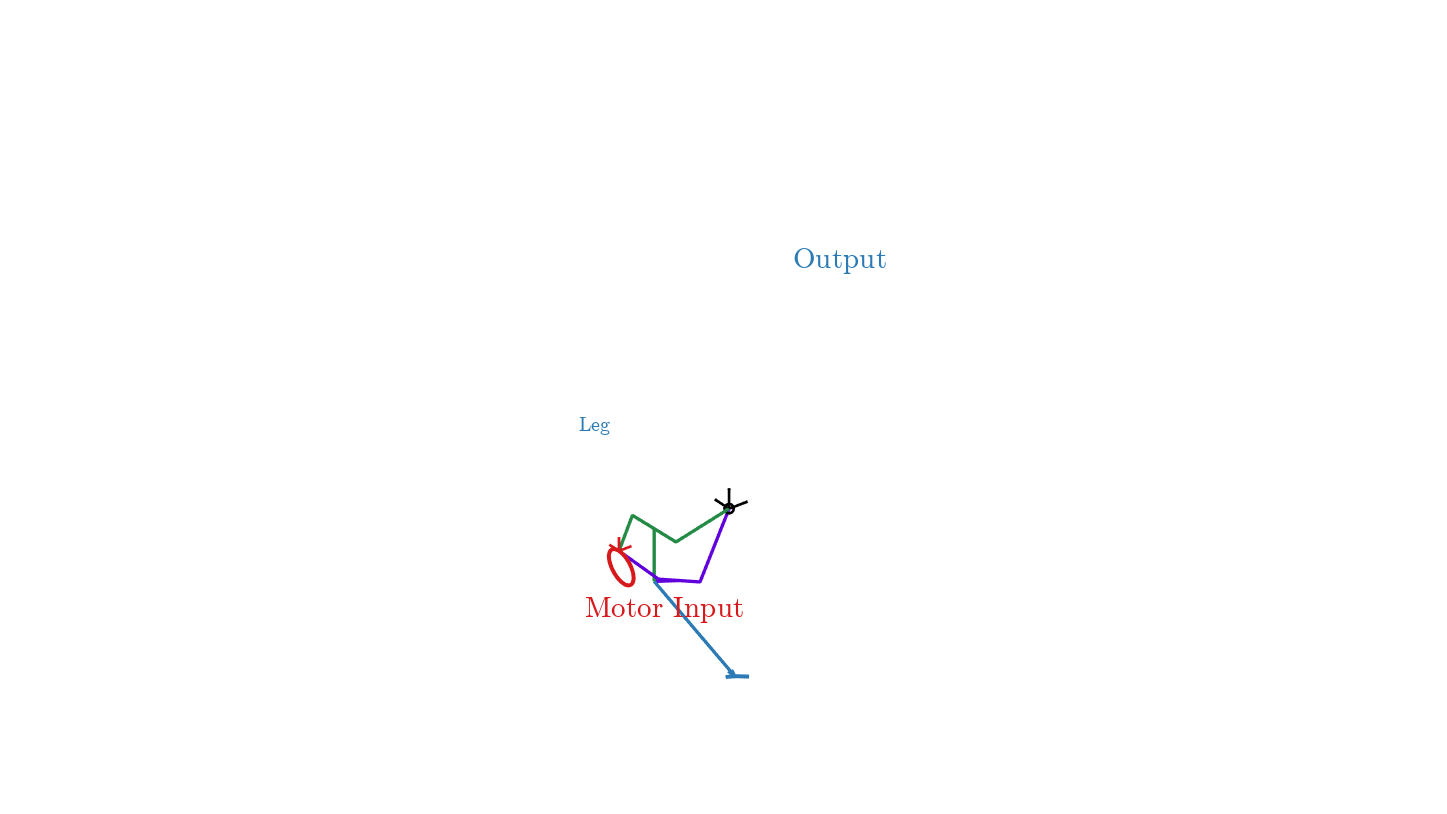

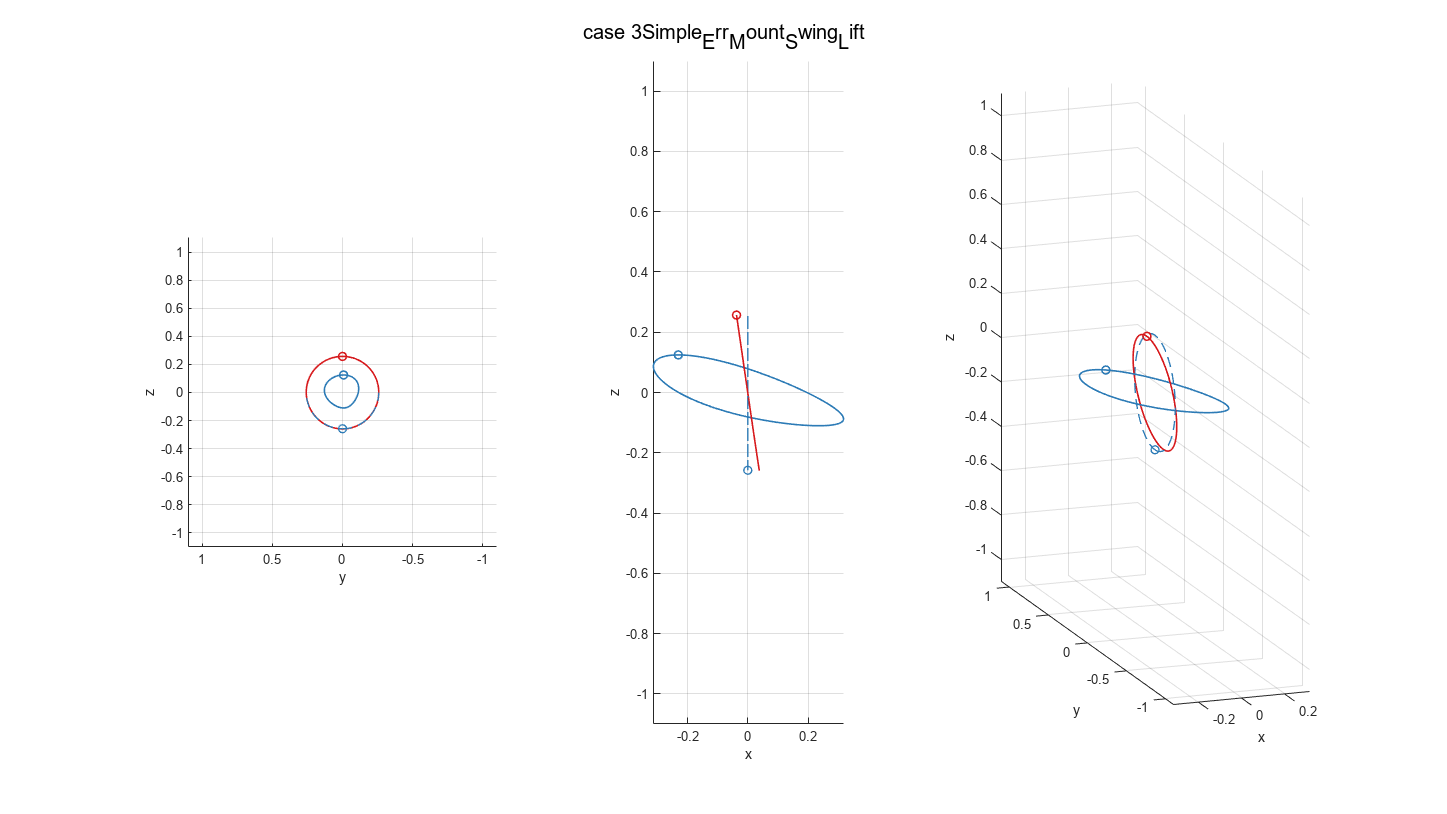

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 3;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

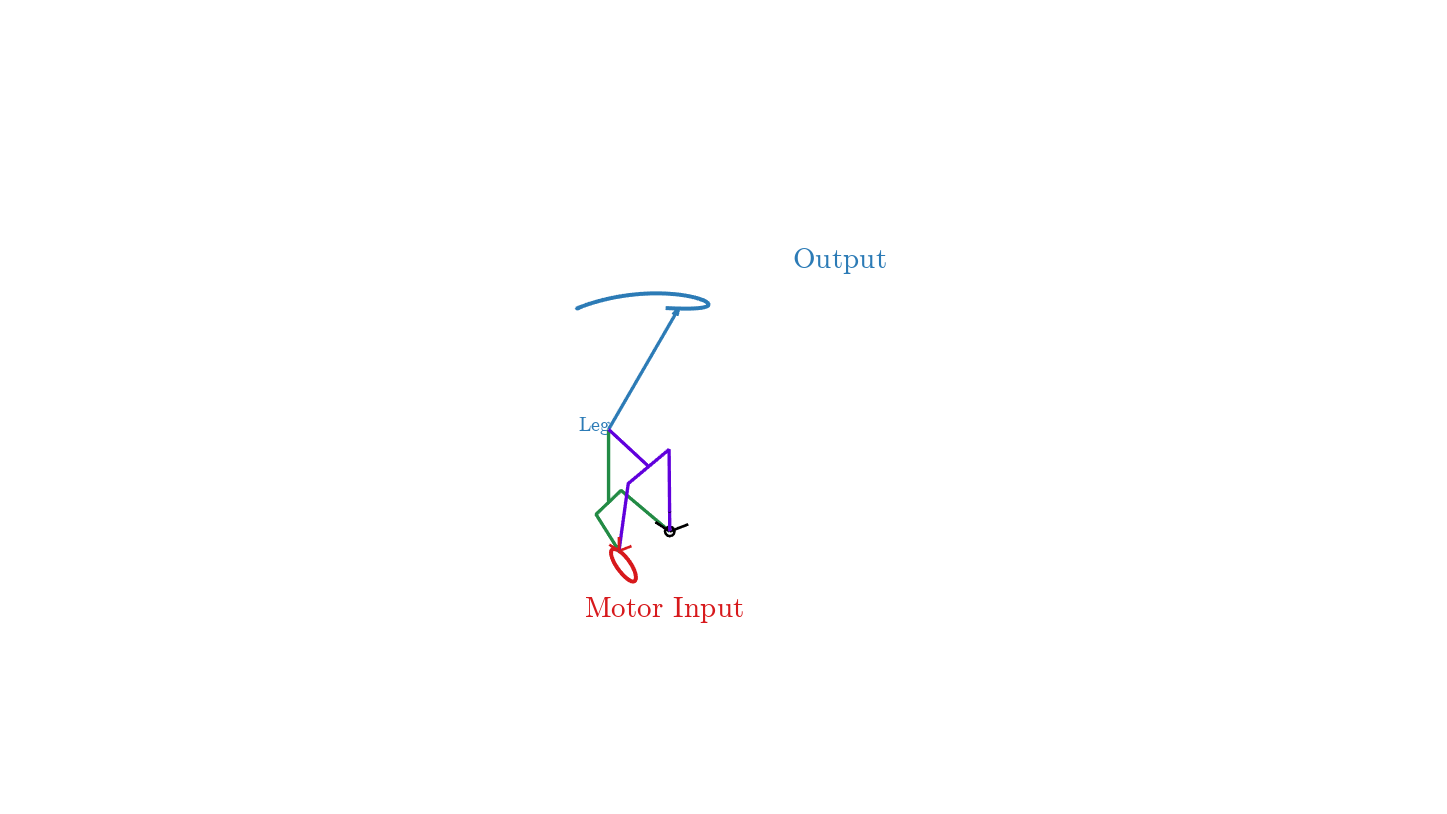

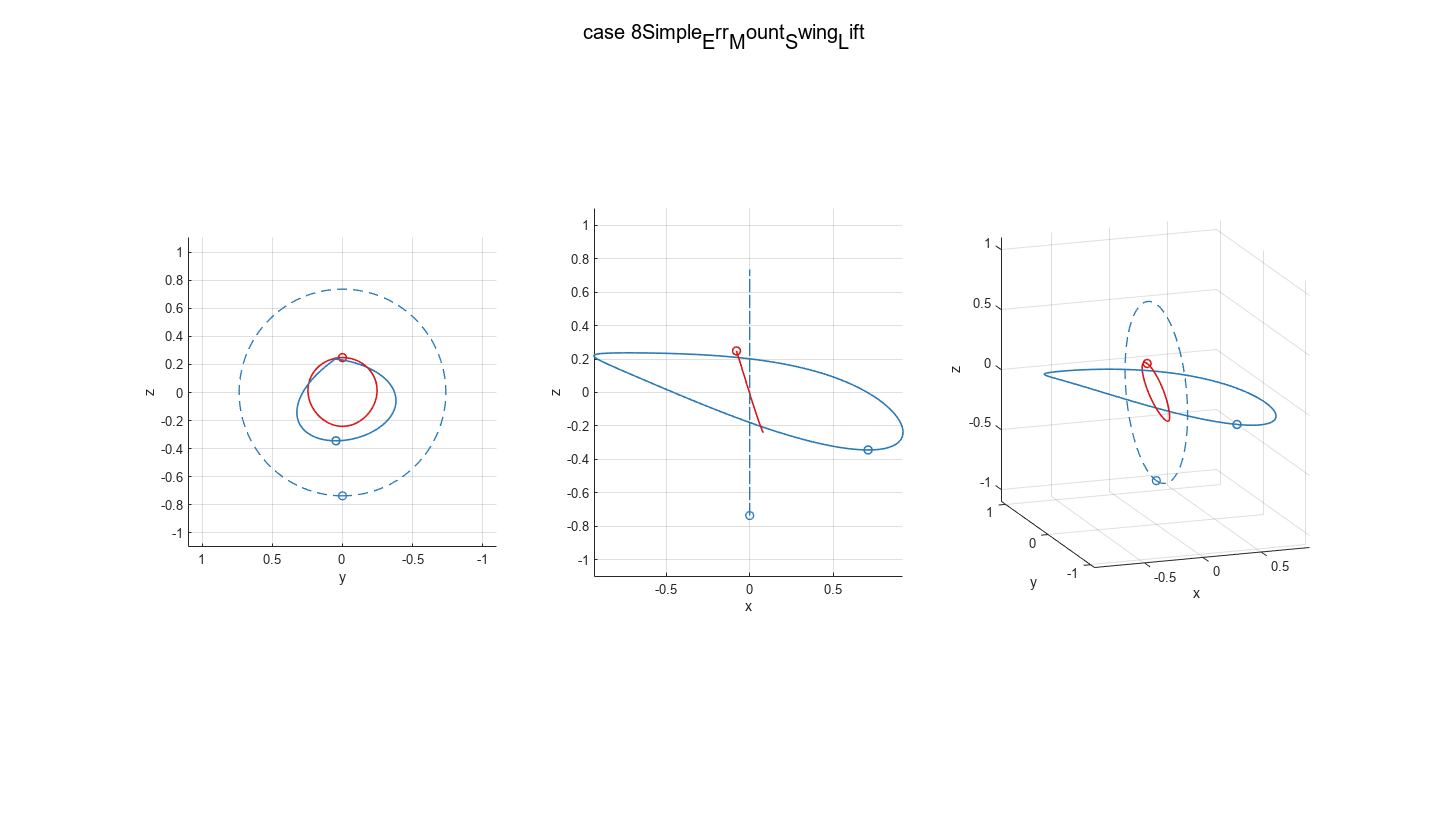

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 8;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

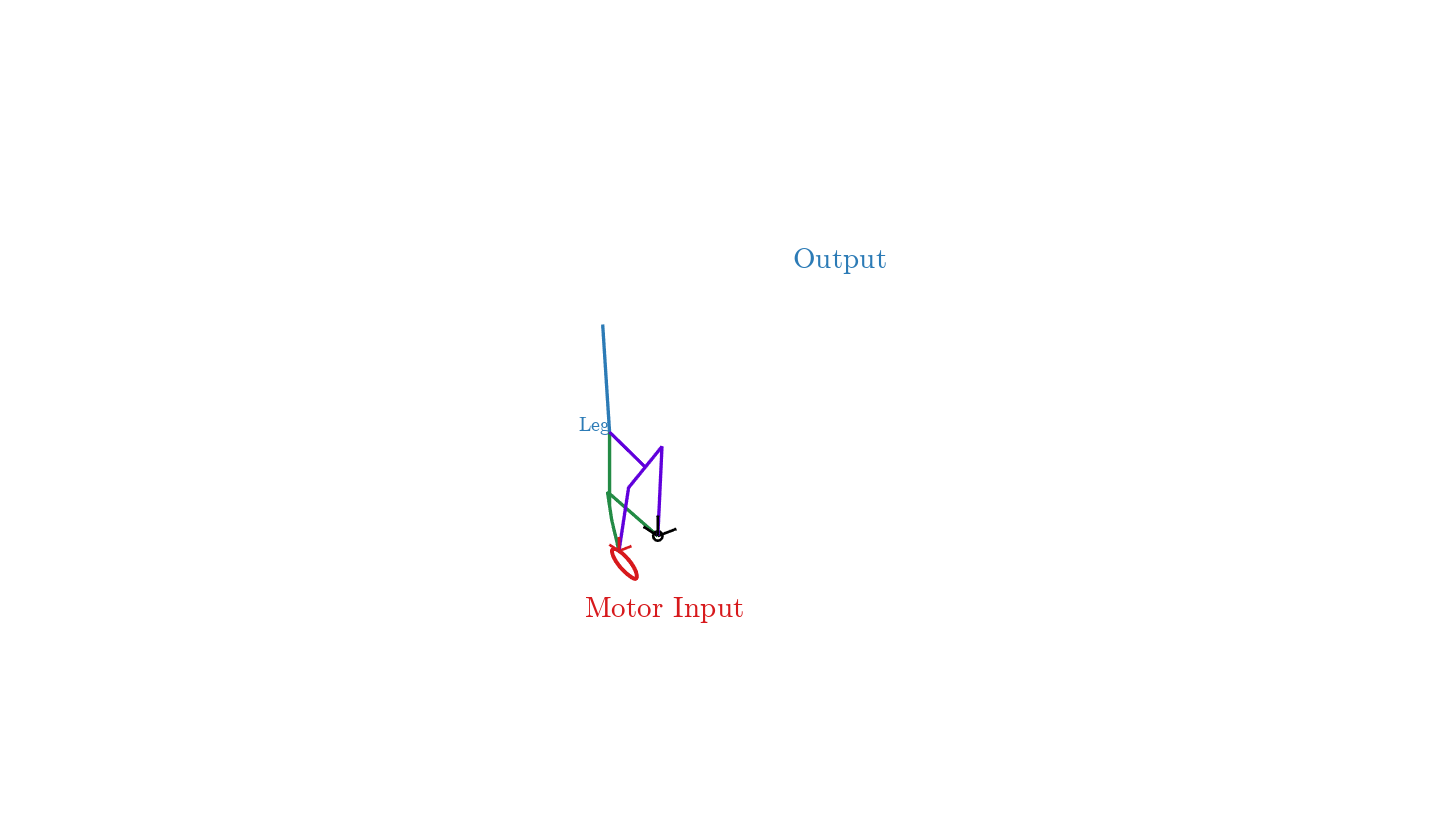

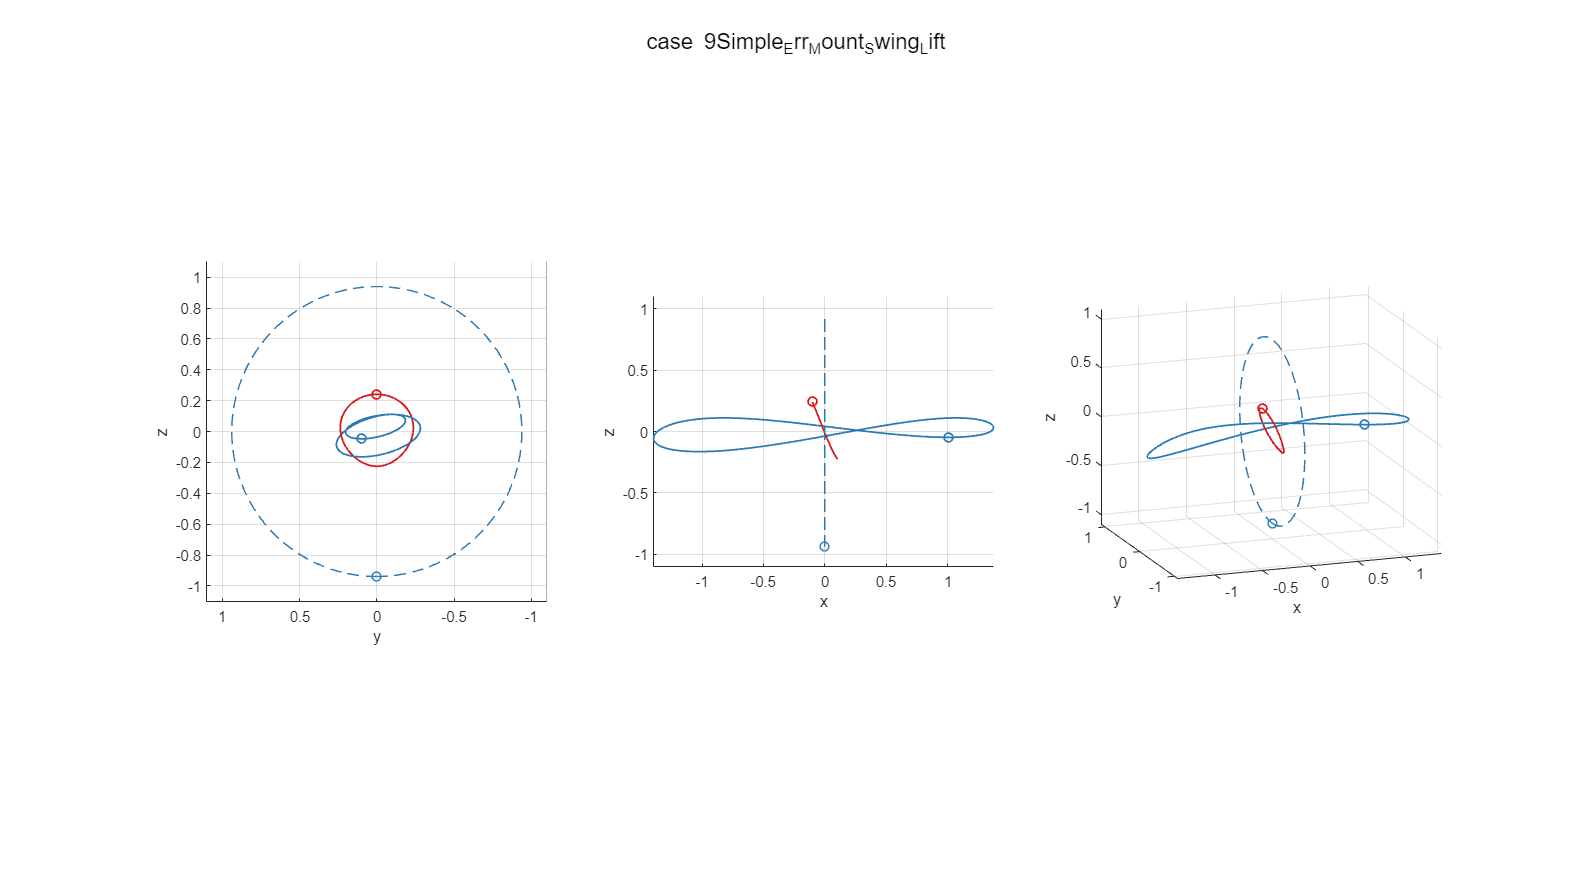

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
j = 9;
v.vidF = true;
% % % v.vidF = false;
if v.vidF
    v.vidT = 5;
    v.Quality = 25;
    v.name = ['case_' num2str(j) ctext];
end
DASH_plot_output(j, x{j}, v, g_b(j), g_a(j), maxtrajsize, p);

Rough work (all sections below)

simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1])

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 & \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

tranS(simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1]))

$$ans = \left(\begin{array}{c} \frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\\ \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

selY_t*tranS(simplify(h_i__1*h_1__2*[subs(rotZ,theta,-theta_2-theta_1), 0.5*[l_2, 0, 0]'; zeros(1,3), 1]))

$$ans = \left(\begin{array}{c} 0\\ \frac{l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1])

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & -1 & \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

tranS(simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1]))

$$ans = \left(\begin{array}{c} \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0\\ \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}\right)$$

(selX_t + selZ_t)*tranS(simplify(h_i__4*h_4__5*[subs(rotZ,theta,-theta_4-theta_5)*subs(rotX, psi, pi/2), 0.5*[l_5, 0, 0]'; zeros(1,3), 1]))

$$ans = \left(\begin{array}{c} \frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\cos\left(\theta_{4}\right)\\ 0\\ \frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)}{2}+l_{4}\,\sin\left(\theta_{4}\right) \end{array}\right)$$

simplify(h_i__4*h_4__5)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{4}+\theta_{5}\right) & -\sin\left(\theta_{4}+\theta_{5}\right) & 0 & l_{4}\,\cos\left(\theta_{4}\right)\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{4}+\theta_{5}\right) & \cos\left(\theta_{4}+\theta_{5}\right) & 0 & l_{4}\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

rotS(simplify(h_i__4*h_4__5))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{4}+\theta_{5}\right) & -\sin\left(\theta_{4}+\theta_{5}\right) & 0\\ 0 & 0 & -1\\ \sin\left(\theta_{4}+\theta_{5}\right) & \cos\left(\theta_{4}+\theta_{5}\right) & 0 \end{array}\right)$$

zcirc'*rotS(simplify(h_i__4*h_4__5))*zcirc

$$ans = 0$$

xcirc'*rotS(simplify(h_i__4*h_4__5))*xcirc

$$ans = \cos\left(\theta_{4}+\theta_{5}\right)$$

-atan2(zcirc'*rotS(simplify(h_i__4*h_4__5))*zcirc, xcirc'*rotS(simplify(h_i__4*h_4__5))*xcirc)

$$ans = -\frac{\pi \,\mathrm{sign}\left(\cos\left(\theta_{4}+\theta_{5}\right)\right)\,\left(\mathrm{sign}\left(\cos\left(\theta_{4}+\theta_{5}\right)\right)-1\right)}{2}$$

simplify(rotS(h_i__4)'*rotS(h_i__4*h_4__5))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))*ycirc

$$ans = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))*xcirc

$$ans = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

% Test out various components -- THETA_0 -- leg orientation
rotS(simplify(h_i__1*h_1__2))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

rotS(simplify(h_i__1*h_1__2))*xcirc

$$ans = \left(\begin{array}{c} \cos\left(\theta_{1}+\theta_{2}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right)\\ 0 \end{array}\right)$$

ycirc'*rotS(simplify(h_i__1*h_1__2))*xcirc

$$ans = \sin\left(\theta_{1}+\theta_{2}\right)$$

xcirc'*rotS(simplify(h_i__1*h_1__2))*xcirc

$$ans = \cos\left(\theta_{1}+\theta_{2}\right)$$

simplify(atan((ycirc'*rotS(h_i__1*h_1__2)*xcirc)/(xcirc'*rotS(h_i__1*h_1__2)*xcirc)),'IgnoreAnalyticConstraints',true)

$$ans = \theta_{1}+\theta_{2}$$

% PHI_0
rotS(simplify(h_i__4*h_4__5))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{4}+\theta_{5}\right) & -\sin\left(\theta_{4}+\theta_{5}\right) & 0\\ 0 & 0 & -1\\ \sin\left(\theta_{4}+\theta_{5}\right) & \cos\left(\theta_{4}+\theta_{5}\right) & 0 \end{array}\right)$$

rotS(simplify(h_i__4*h_4__5))*xcirc

$$ans = \left(\begin{array}{c} \cos\left(\theta_{4}+\theta_{5}\right)\\ 0\\ \sin\left(\theta_{4}+\theta_{5}\right) \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))*xcirc

$$ans = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

simplify(subs(rotX,psi,pi/2))*ycirc

$$ans = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

xcirc'*simplify(subs(rotX,psi,-pi/2))*rotS(simplify(h_i__4*h_4__5))*xcirc

$$ans = \cos\left(\theta_{4}+\theta_{5}\right)$$

ycirc'*simplify(subs(rotX,psi,-pi/2))*rotS(simplify(h_i__4*h_4__5))*xcirc

$$ans = \sin\left(\theta_{4}+\theta_{5}\right)$$

simplify(atan((ycirc'*subs(rotX,psi,-pi/2)*rotS(h_i__4*h_4__5)*xcirc)/(xcirc'*subs(rotX,psi,-pi/2)*rotS(h_i__4*h_4__5)*xcirc)),'IgnoreAnalyticConstraints',true)

$$ans = \theta_{4}+\theta_{5}$$

sin(beta)*cos(alpha)

$$ans = -\sin\left(\hat{\beta }+\frac{\pi }{2}-\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\,\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)$$

simplify(sin(beta)*cos(alpha))

$$ans = -\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\,\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)$$

cos(beta)

$$ans = \cos\left(\hat{\beta }+\frac{\pi }{2}-\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)$$

simplify(cos(beta))

$$ans = \sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)$$

sin(beta)*sin(alpha)

$$ans = \sin\left(\hat{\beta }+\frac{\pi }{2}-\hat{\beta }\,\cos\left(2\,\pi \,\tau \right)\right)\,\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)$$

simplify(sin(beta)*sin(alpha))

$$ans = \cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\,\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)$$

h_e__i

$$h\_e\_\_i = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{3} & -\sigma_{4}\,\sigma_{3} & -\sigma_{2} & -l\,\sigma_{1}\,\sigma_{3}\\ -\sigma_{5} & \sigma_{1} & 0 & l\,\sigma_{4}\\ \sigma_{1}\,\sigma_{2} & \sigma_{5}\,\sigma_{2} & \sigma_{3} & l\,\sigma_{1}\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{2}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{4}=\sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{5}=\sin\left(2\,\hat{\beta }\,{\sin\left(\pi \,\tau \right)}^{2}\right) \end{array}$$

% alpha_f = matlabFunction(subs(alpha, alpha_hat, a_hat), 'Vars', tau)
% alpha_f(t)
% figure()
% plot(t,alpha_f(t))

alpha_f = function_handle with value:
    @(tau)pi.*sin(tau.*pi.*2.0).*(-1.0./3.6e+1)


double(subs(h_i__0b_l, [theta_1, l_1, theta_2, l_2, theta_3, l_3], [theta1, l1, theta2, l2, theta3, l3]))

ans =     1.0000         0         0    1.0000
         0    1.0000         0    0.0000
         0         0    1.0000         0
         0         0         0    1.0000


double(subs(h_i__0b_s, [theta_4, l_4, theta_5, l_5, theta_6, l_6], [theta4, l4, theta5, l5, theta6, l6]))

ans =     1.0000         0         0    1.0000
         0    1.0000         0         0
         0         0    1.0000    0.0000
         0         0         0    1.0000


The two chains end up in the same spot: ground!

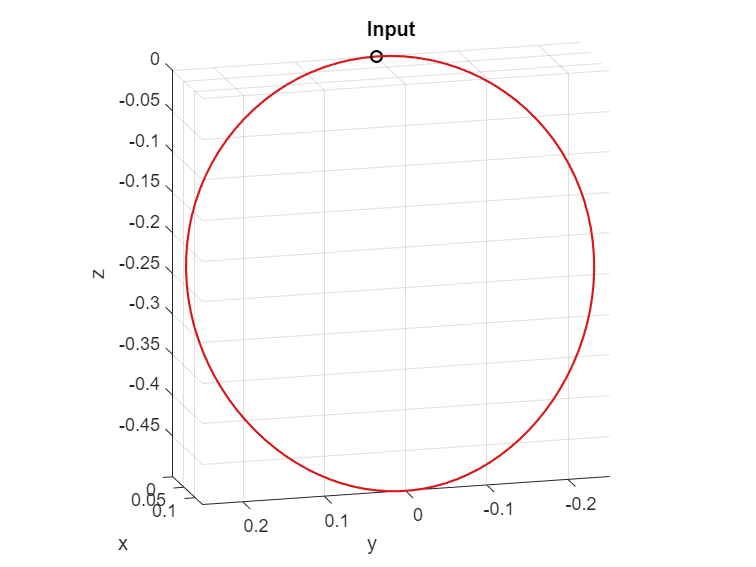

% Debugging the still images we are getting from the animation -- INPUT
figure()
plot3(h_i_t(1,4,1),h_i_t(3,4,1),h_i_t(2,4,1),'ko','LineWidth',1.2);
hold on; grid on; axis equal; view([-101.217 22.200]);
plot3(reshape(h_i_t(1,4,:),1,length(t)),reshape(h_i_t(3,4,:),1,length(t)),reshape(h_i_t(2,4,:),1,length(t)),...
    'Color',circ1,'LineWidth',1.2);
view(-90,0);
xlabel('x');
ylabel('y');
zlabel('z');
title('Input');

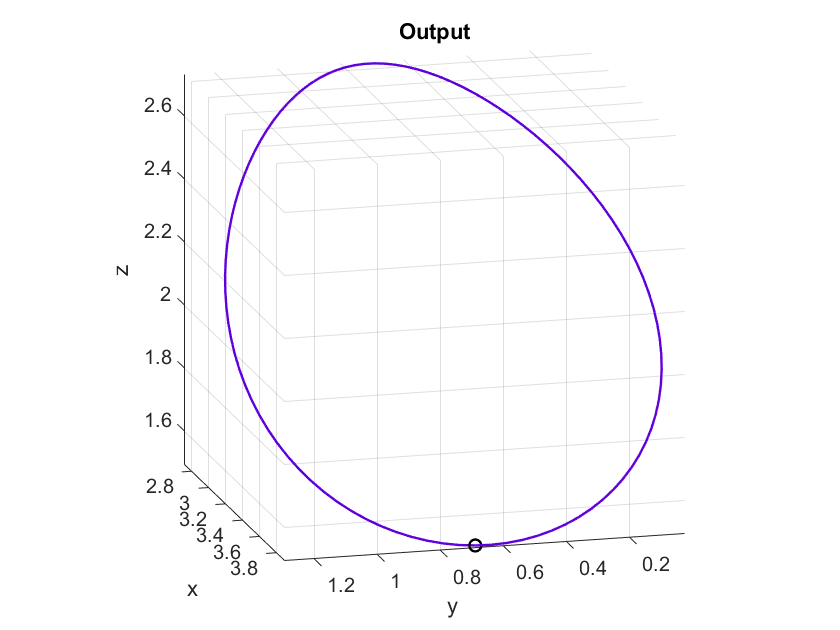

% Debugging the still images we are getting from the animation -- OUTPUT
figure()
plot3(h_o_t(1,4,1),h_o_t(3,4,1),h_o_t(2,4,1),'ko','LineWidth',1.2);
hold on; grid on; axis equal; view([-101.217 22.200]);
plot3(reshape(h_o_t(1,4,:),1,length(t)),reshape(h_o_t(3,4,:),1,length(t)),reshape(h_o_t(2,4,:),1,length(t)),...
    'Color',circ2,'LineWidth',1.2);
view(-90,0);
xlabel('x');
ylabel('y');
zlabel('z');
title('Output');

% % % % % % % This still looks to be a complicated expression, but one simplification we could make is to only consider the y-z plane output range; x-range corresponds to how curved the output surface is and we are only trying to get a sense for the range, not the curvature in x.
% ht_e__o__swing_yz = ht_e__o__swing(2:3)
% ht_e__o__swing_yz_range = simplify(int(ht_e__o__swing_yz, alpha_tilde, [alpha_tilde__0, alpha_tilde__1]), 'Steps', 10)
% ht_e__o__swing_yz_rangeSq = simplify(ht_e__o__swing_yz_range'*ht_e__o__swing_yz_range, 'Steps', 10)
% ht_e__o__swing_yz_rangeSq_15degs = simplify(subs(ht_e__o__swing_yz_rangeSq, [alpha_tilde__0 alpha_tilde__1], a_hat*[-1 1]))
% % % % % % % Literally looks like the x-term got removed from full swing range expression. Didn't get simplified much further! Hence, a wasted endeavor.

simplify(subs(h_e__i, beta_tilde, 0))

$$ans = \left(\begin{array}{cccc} \cos\left(\tilde{\alpha }\right) & 0 & \sin\left(\tilde{\alpha }\right) & -l\,\left(\cos\left(\tilde{\alpha }\right)-1\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\tilde{\alpha }\right) & 0 & \cos\left(\tilde{\alpha }\right) & l\,\sin\left(\tilde{\alpha }\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

cond_1_x = subs(cond_1, sin(theta_1 + theta_2 + theta_3), sin(sym('y')))

$$cond\_1\_x = l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)+l_{3}\,\sin\left(y\right)=0$$

% Checking if we can substitute stuff for functions on several variables --
% WORKS!

$$h\_e\_\_i = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{3} & \sigma_{4}\,\sigma_{3} & \sigma_{2} & l-l\,\sigma_{1}\,\sigma_{3}\\ \sigma_{5} & \sigma_{1} & 0 & l\,\sigma_{4}\\ -\sigma_{1}\,\sigma_{2} & \sigma_{5}\,\sigma_{2} & \sigma_{3} & l\,\sigma_{1}\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{2}=\sin\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{3}=\cos\left(\hat{\alpha }\,\sin\left(2\,\pi \,\tau \right)\right)\\ \sigma_{4}=\sin\left(\hat{\beta }\,\left(\cos\left(2\,\pi \,\tau \right)-1\right)\right)\\ \sigma_{5}=\sin\left(2\,\hat{\beta }\,{\sin\left(\pi \,\tau \right)}^{2}\right) \end{array}$$

norm(ht_e__o_swing_range)^2

$$ans = \begin{array}{l} {\left|l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{2}-l\,\sigma_{1}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right|}^{2}+{\left|l\,\sigma_{2}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right|}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right) \end{array}$$

temp_1 = ht_e__o_swing_range(1)^2 + ht_e__o_swing_range(2)^2 + ht_e__o_swing_range(3)^2

$$temp\_1 = \begin{array}{l} {\left(l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{2}-l\,\sigma_{1}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right)}^{2}+{\left(l\,\sigma_{2}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right) \end{array}$$

temp_1 = subs(temp_1, l, rhs(cond_3))

$$temp\_1 = \begin{array}{l} {\left(l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{2}-\sigma_{1}\,\sigma_{3}+\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}+l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{1}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right)}^{2}+{\left(\sigma_{2}\,\sigma_{3}-l_{4}\,\cos\left(\theta_{4}\right)\,\sigma_{2}+\frac{l_{5}\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}}{2}-\frac{l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}}{2}+l_{4}\,\sin\left(\theta_{4}\right)\,\sigma_{1}+L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{4}+\theta_{5}\right)\,\sigma_{1}-L\,\cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{4}+\theta_{5}\right)\,\sigma_{2}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\tilde{\alpha }}^{0}\right)-\cos\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{2}=\sin\left({\tilde{\alpha }}^{0}\right)-\sin\left({\tilde{\alpha }}^{1}\right)\\ \sigma_{3}=l_{5}\,\cos\left(\theta_{4}+\theta_{5}\right)+l_{4}\,\cos\left(\theta_{4}\right)+l_{6}\,\cos\left(\theta_{4}+\theta_{5}+\theta_{6}\right) \end{array}$$